open_system('RL_Heat_DDPG_test')

## Create Environment Interface

Creating an environment model includes defining the following:

- Action and observation signals that the agent uses to interact with the environment. For more information, see [rlNumericSpec](docid:rl_ref#mw_1a66fdf2-e758-4985-a541-61943fb15e79) and [rlFiniteSetSpec](docid:rl_ref#mw_68f70adf-d6a9-4cbe-846c-a7d0823c0774).

- Reward signal that the agent uses to measure its success. For more information, see [Define Reward Signals](docid:rl_ug#mw_1fe437df-5904-43dc-8b75-1e25bb9ae3ff).

Define the observation specification `obsInfo` and action specification `actInfo`.

obsInfo = rlNumericSpec([3 1],...
    'LowerLimit',[-inf -inf 0  ]',...
    'UpperLimit',[ inf  inf inf]');
obsInfo.Name = 'observations';
obsInfo.Description = 'integrated error, error, and measured temperature';
numObservations = obsInfo.Dimension(1);

actInfo = rlNumericSpec([1 1]);
actInfo.Name = 'heat-flow';
numActions = actInfo.Dimension(1);

Build the environment interface object.

env = rlSimulinkEnv('RL_Heat_DDPG_test','RL_Heat_DDPG_test/RL Agent',...
    obsInfo,actInfo);

Set a custom reset function that randomizes the reference values for the model.

env.ResetFcn = @(in)localResetFcn(in);

Specify the simulation time `Tf` and the agent sample time `Ts` in seconds.

Ts = 1.0;
Tf = 200;

Fix the random generator seed for reproducibility.

rng(0)

## Create DDPG Agent

Given observations and actions, a DDPG agent approximates the long-term reward using a critic value function representation. To create the critic, first create a deep neural network with two inputs, the observation and action, and one output. For more information on creating a deep neural network value function representation, see [Create Policy and Value Function Representations](docid:rl_ug#mw_2c7e8669-1e91-4d42-afa6-674009a08004).

statePath = [
    imageInputLayer([numObservations 1 1],'Normalization','none','Name','State')
    fullyConnectedLayer(50,'Name','CriticStateFC1')
    reluLayer('Name','CriticRelu1')
    fullyConnectedLayer(25,'Name','CriticStateFC2')];
actionPath = [
    imageInputLayer([numActions 1 1],'Normalization','none','Name','Action')
    fullyConnectedLayer(25,'Name','CriticActionFC1')];
commonPath = [
    additionLayer(2,'Name','add')
    reluLayer('Name','CriticCommonRelu')
    fullyConnectedLayer(1,'Name','CriticOutput')];

criticNetwork = layerGraph();
criticNetwork = addLayers(criticNetwork,statePath);
criticNetwork = addLayers(criticNetwork,actionPath);
criticNetwork = addLayers(criticNetwork,commonPath);
criticNetwork = connectLayers(criticNetwork,'CriticStateFC2','add/in1');
criticNetwork = connectLayers(criticNetwork,'CriticActionFC1','add/in2');

View the critic network configuration.

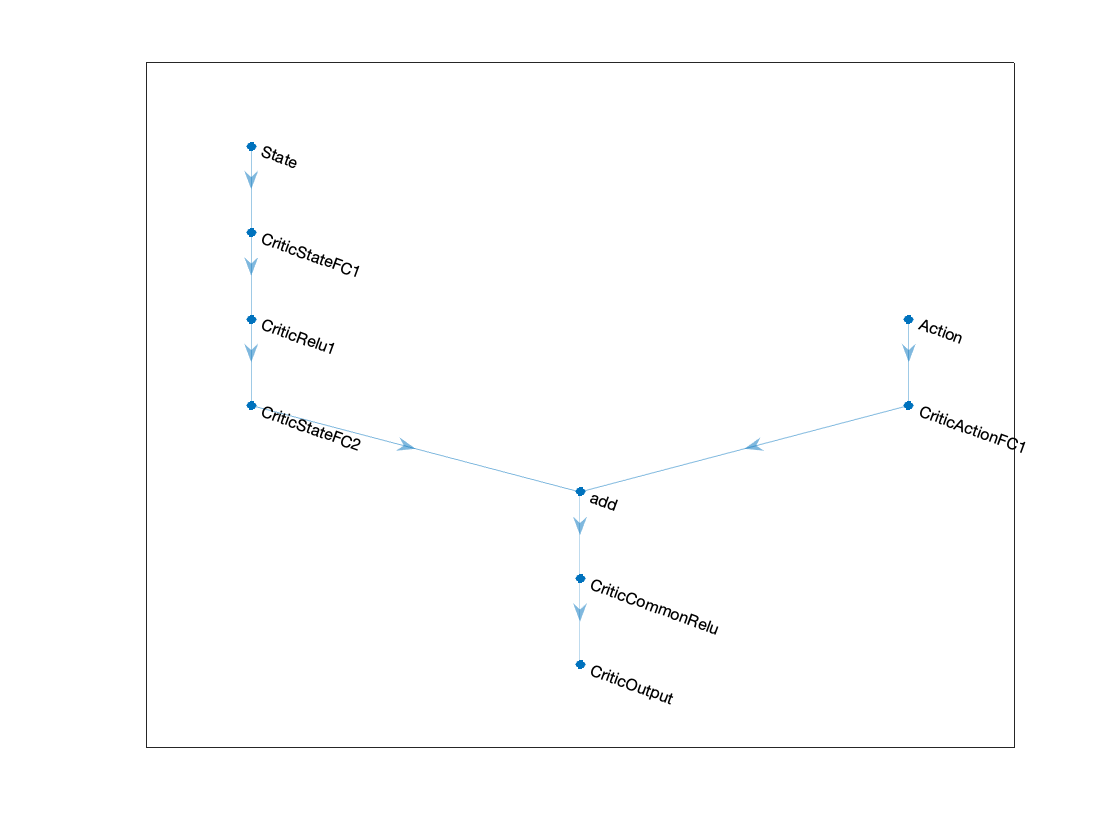

figure
plot(criticNetwork)

Specify options for the critic representation using [`rlRepresentationOptions`](docid:rl_ref#mw_45ccf57d-64f0-4822-8000-3f0f44f2572e).

criticOpts = rlRepresentationOptions('LearnRate',1e-03,'GradientThreshold',1);

Create the critic representation using the specified deep neural network and options. You must also specify the action and observation specifications for the critic, which you obtain from the environment interface. For more information, see [`rlQValueRepresentation`](docid:rl_ref#mw_6e9cf856-c679-4834-97e1-1349c4a21e43).

critic = rlQValueRepresentation(criticNetwork,obsInfo,actInfo,'Observation',{'State'},'Action',{'Action'},criticOpts);

Given observations, a DDPG agent decides which action to take using an actor representation. To create the actor, first create a deep neural network with one input, the observation, and one output, the action.

Construct the actor in a similar manner to the critic. For more information, see [`rlDeterministicActorRepresentation`](docid:rl_ref#mw_425a8728-2966-45c4-9d2a-488aa4a506bf).

actorNetwork = [
    imageInputLayer([numObservations 1 1],'Normalization','none','Name','State')
    fullyConnectedLayer(3, 'Name','actorFC')
    tanhLayer('Name','actorTanh')
    fullyConnectedLayer(numActions,'Name','Action')
    ];

actorOptions = rlRepresentationOptions('LearnRate',1e-04,'GradientThreshold',1);

actor = rlDeterministicActorRepresentation(actorNetwork,obsInfo,actInfo,'Observation',{'State'},'Action',{'Action'},actorOptions);

To create the DDPG agent, first specify the DDPG agent options using [rlDDPGAgentOptions](docid:rl_ref#mw_5e9a4c5d-03d5-48d9-a85b-3c2d25fde43c).

agentOpts = rlDDPGAgentOptions(...
    'SampleTime',Ts,...
    'TargetSmoothFactor',1e-3,...
    'DiscountFactor',1.0, ...
    'MiniBatchSize',64, ...
    'ExperienceBufferLength',1e6); 
agentOpts.NoiseOptions.Variance = 0.3;
agentOpts.NoiseOptions.VarianceDecayRate = 1e-5;

Then, create the DDPG agent using the specified actor representation, critic representation, and agent options. For more information, see [rlDDPGAgent](docid:rl_ref#mw_7e49ed9c-eea8-4994-8532-c7f66d5359ef).

agent = rlDDPGAgent(actor,critic,agentOpts);

% pool = parpool(8)

## Train Agent

To train the agent, first specify the training options. For this example, use the following options:

- Run each training for at most `5000` episodes. Specify that each episode lasts for at most `200` time steps.

- Display the training progress in the Episode Manager dialog box (set the `Plots` option) and disable the command line display (set the `Verbose` option to `false`).

- Stop training when the agent receives an average cumulative reward greater than 800 over 20 consecutive episodes. At this point, the agent can control the level of water in the tank.

For more information, see [`rlTrainingOptions`](docid:rl_ref#mw_1f5122fe-cb3a-4c27-8c80-1ce46c013bf0).

maxepisodes = 8000;
maxsteps = ceil(Tf/Ts);
trainOpts = rlTrainingOptions(...
    'MaxEpisodes',maxepisodes, ...
    'MaxStepsPerEpisode',maxsteps, ...
    'ScoreAveragingWindowLength',20, ...
    'Verbose',true, ...
    'Plots','training-progress',...
    'StopTrainingCriteria','AverageReward',...
    'StopTrainingValue',30000);

% trainOpts.UseParallel = true;
% trainOpts.ParallelizationOptions.Mode = "async";
% trainOpts.ParallelizationOptions.DataToSendFromWorkers = "experiences";
% trainOpts.ParallelizationOptions.StepsUntilDataIsSent = 30;
% trainOpts.ParallelizationOptions.WorkerRandomSeeds = -1;

Train the agent using the [`train`](docid:rl_ref#mw_c0ccd38c-bbe6-4609-a87d-52ebe4767852) function. Training is a computationally intensive process that takes several minutes to complete. To save time while running this example, load a pretrained agent by setting `doTraining` to `false`. To train the agent yourself, set `doTraining` to `true`.

doTraining = true;

if doTraining
    % Train the agent.
    trainingStats = train(agent,env,trainOpts);
else
    % Load the pretrained agent for the example.
    load('/Users/abhijit/Desktop/GIT_Projects/Matlab/sldemo_househeatExample/slprj/savedAgents/Heat_agent.mat','agent')
end


Episode:   1/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -90.00 | Step Count : 1 | Episode Q0 : -0.65


Episode:   2/8000 | Episode Reward : -70.00 | Episode Steps:    3 | Avg Reward : -80.00 | Step Count : 4 | Episode Q0 : -0.58


Episode:   3/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -83.33 | Step Count : 5 | Episode Q0 : -0.69


Episode:   4/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -85.00 | Step Count : 6 | Episode Q0 : -0.57


Episode:   5/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -86.00 | Step Count : 7 | Episode Q0 : -0.57


Episode:   6/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -86.67 | Step Count : 8 | Episode Q0 : -0.61


Episode:   7/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -87.14 | Step Count : 9 | Episode Q0 : -0.68


Episode:   8/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -87.50 | Step Count : 10 | Episode Q0 : -0.65


Episode:   9/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -87.78 | Step Count : 11 | Episode Q0 : -0.67


Episode:  10/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -88.00 | Step Count : 12 | Episode Q0 : -0.52


Episode:  11/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -88.18 | Step Count : 13 | Episode Q0 : -0.75


Episode:  12/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -88.33 | Step Count : 14 | Episode Q0 : -0.72


Episode:  13/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -88.46 | Step Count : 15 | Episode Q0 : -0.62


Episode:  14/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -88.57 | Step Count : 16 | Episode Q0 : -0.48


Episode:  15/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -88.67 | Step Count : 17 | Episode Q0 : -0.43


Episode:  16/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -88.75 | Step Count : 18 | Episode Q0 : -0.56


Episode:  17/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -88.82 | Step Count : 19 | Episode Q0 : -0.75


Episode:  18/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -88.89 | Step Count : 20 | Episode Q0 : -0.41


Episode:  19/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -88.95 | Step Count : 21 | Episode Q0 : -0.43


Episode:  20/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -89.00 | Step Count : 22 | Episode Q0 : -0.62


Episode:  21/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -89.00 | Step Count : 23 | Episode Q0 : -0.75


Episode:  22/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -90.00 | Step Count : 24 | Episode Q0 : -0.59


Episode:  23/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -90.00 | Step Count : 25 | Episode Q0 : -0.43


Episode:  24/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -90.00 | Step Count : 26 | Episode Q0 : -0.75


Episode:  25/8000 | Episode Reward : -30.00 | Episode Steps:    7 | Avg Reward : -87.00 | Step Count : 33 | Episode Q0 : -0.71


Episode:  26/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -87.00 | Step Count : 34 | Episode Q0 : -0.60


Episode:  27/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -87.00 | Step Count : 35 | Episode Q0 : -0.66


Episode:  28/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -87.00 | Step Count : 36 | Episode Q0 : -0.69


Episode:  29/8000 | Episode Reward : -80.00 | Episode Steps:    2 | Avg Reward : -86.50 | Step Count : 38 | Episode Q0 : -0.75


Episode:  30/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -86.50 | Step Count : 39 | Episode Q0 : -0.57


Episode:  31/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -86.50 | Step Count : 40 | Episode Q0 : -0.58


Episode:  32/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -86.50 | Step Count : 41 | Episode Q0 : -0.71


Episode:  33/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -86.50 | Step Count : 42 | Episode Q0 : -0.71


Episode:  34/8000 | Episode Reward : 20.00 | Episode Steps:   12 | Avg Reward : -81.00 | Step Count : 54 | Episode Q0 : -0.75


Episode:  35/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -81.00 | Step Count : 55 | Episode Q0 : -0.56


Episode:  36/8000 | Episode Reward : -70.00 | Episode Steps:    3 | Avg Reward : -80.00 | Step Count : 58 | Episode Q0 : -0.60


Episode:  37/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -80.00 | Step Count : 59 | Episode Q0 : -0.75


Episode:  38/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -80.00 | Step Count : 60 | Episode Q0 : -0.75


Episode:  39/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -80.00 | Step Count : 61 | Episode Q0 : -0.73


Episode:  40/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -80.00 | Step Count : 62 | Episode Q0 : -0.60


Episode:  41/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -80.00 | Step Count : 63 | Episode Q0 : -0.55


Episode:  42/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -80.00 | Step Count : 64 | Episode Q0 : -0.69


Episode:  43/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -80.00 | Step Count : 65 | Episode Q0 : -0.91


Episode:  44/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -80.00 | Step Count : 66 | Episode Q0 : -1.27


Episode:  45/8000 | Episode Reward : -70.00 | Episode Steps:    3 | Avg Reward : -82.00 | Step Count : 69 | Episode Q0 : -1.67


Episode:  46/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -82.00 | Step Count : 70 | Episode Q0 : -2.12


Episode:  47/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -82.00 | Step Count : 71 | Episode Q0 : -3.34


Episode:  48/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -82.00 | Step Count : 72 | Episode Q0 : -2.89


Episode:  49/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -82.50 | Step Count : 73 | Episode Q0 : -3.72


Episode:  50/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -82.50 | Step Count : 74 | Episode Q0 : -4.16


Episode:  51/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -82.50 | Step Count : 75 | Episode Q0 : -4.13


Episode:  52/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -82.50 | Step Count : 76 | Episode Q0 : -5.24


Episode:  53/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -82.50 | Step Count : 77 | Episode Q0 : -4.16


Episode:  54/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -88.00 | Step Count : 78 | Episode Q0 : -5.69


Episode:  55/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -88.00 | Step Count : 79 | Episode Q0 : -5.86


Episode:  56/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -89.00 | Step Count : 80 | Episode Q0 : -6.90


Episode:  57/8000 | Episode Reward : 240.00 | Episode Steps:   12 | Avg Reward : -72.50 | Step Count : 92 | Episode Q0 : -6.97


Episode:  58/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -72.50 | Step Count : 93 | Episode Q0 : -6.85


Episode:  59/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -72.50 | Step Count : 94 | Episode Q0 : -11.71


Episode:  60/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -72.50 | Step Count : 95 | Episode Q0 : -9.56


Episode:  61/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -72.50 | Step Count : 96 | Episode Q0 : -7.76


Episode:  62/8000 | Episode Reward : 110.00 | Episode Steps:   10 | Avg Reward : -62.50 | Step Count : 106 | Episode Q0 : -11.41


Episode:  63/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -62.50 | Step Count : 107 | Episode Q0 : -21.14


Episode:  64/8000 | Episode Reward : 420.00 | Episode Steps:   19 | Avg Reward : -37.00 | Step Count : 126 | Episode Q0 : -15.89


Episode:  65/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -38.00 | Step Count : 127 | Episode Q0 : -20.14


Episode:  66/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -38.00 | Step Count : 128 | Episode Q0 : -30.84


Episode:  67/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -38.00 | Step Count : 129 | Episode Q0 : -19.03


Episode:  68/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -38.00 | Step Count : 130 | Episode Q0 : -28.63


Episode:  69/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -38.00 | Step Count : 131 | Episode Q0 : -34.99


Episode:  70/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -38.00 | Step Count : 132 | Episode Q0 : -25.92


Episode:  71/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -38.00 | Step Count : 133 | Episode Q0 : -21.12


Episode:  72/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -38.00 | Step Count : 134 | Episode Q0 : -24.61


Episode:  73/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -38.00 | Step Count : 135 | Episode Q0 : -19.68


Episode:  74/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -38.00 | Step Count : 136 | Episode Q0 : -32.38


Episode:  75/8000 | Episode Reward : -30.00 | Episode Steps:    7 | Avg Reward : -35.00 | Step Count : 143 | Episode Q0 : -28.90


Episode:  76/8000 | Episode Reward : -70.00 | Episode Steps:    3 | Avg Reward : -34.00 | Step Count : 146 | Episode Q0 : -31.71


Episode:  77/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -50.50 | Step Count : 147 | Episode Q0 : -51.18


Episode:  78/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -50.50 | Step Count : 148 | Episode Q0 : -27.03


Episode:  79/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -50.50 | Step Count : 149 | Episode Q0 : -35.60


Episode:  80/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -50.50 | Step Count : 150 | Episode Q0 : -31.88


Episode:  81/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -50.50 | Step Count : 151 | Episode Q0 : -34.14


Episode:  82/8000 | Episode Reward : -70.00 | Episode Steps:    3 | Avg Reward : -59.50 | Step Count : 154 | Episode Q0 : -34.88


Episode:  83/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -59.50 | Step Count : 155 | Episode Q0 : -46.64


Episode:  84/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -85.00 | Step Count : 156 | Episode Q0 : -57.43


Episode:  85/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -85.00 | Step Count : 157 | Episode Q0 : -24.23


Episode:  86/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -85.00 | Step Count : 158 | Episode Q0 : -41.58


Episode:  87/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -85.00 | Step Count : 159 | Episode Q0 : -37.13


Episode:  88/8000 | Episode Reward : 30.00 | Episode Steps:   13 | Avg Reward : -79.00 | Step Count : 172 | Episode Q0 : -42.47


Episode:  89/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -79.00 | Step Count : 173 | Episode Q0 : -36.23


Episode:  90/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -79.00 | Step Count : 174 | Episode Q0 : -48.85


Episode:  91/8000 | Episode Reward : -30.00 | Episode Steps:    7 | Avg Reward : -76.00 | Step Count : 181 | Episode Q0 : -37.29


Episode:  92/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -76.00 | Step Count : 182 | Episode Q0 : -63.15


Episode:  93/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -76.00 | Step Count : 183 | Episode Q0 : -76.87


Episode:  94/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -76.00 | Step Count : 184 | Episode Q0 : -78.09


Episode:  95/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -79.00 | Step Count : 185 | Episode Q0 : -55.54


Episode:  96/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -80.00 | Step Count : 186 | Episode Q0 : -37.48


Episode:  97/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -80.00 | Step Count : 187 | Episode Q0 : -38.24


Episode:  98/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -80.00 | Step Count : 188 | Episode Q0 : -60.21


Episode:  99/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -80.00 | Step Count : 189 | Episode Q0 : -82.35


Episode: 100/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -80.00 | Step Count : 190 | Episode Q0 : -67.57


Episode: 101/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -80.00 | Step Count : 191 | Episode Q0 : -81.34


Episode: 102/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -81.00 | Step Count : 192 | Episode Q0 : -49.76


Episode: 103/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -81.00 | Step Count : 193 | Episode Q0 : -55.50


Episode: 104/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -81.00 | Step Count : 194 | Episode Q0 : -70.07


Episode: 105/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -81.00 | Step Count : 195 | Episode Q0 : -65.03


Episode: 106/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -81.00 | Step Count : 196 | Episode Q0 : -57.84


Episode: 107/8000 | Episode Reward : 120.00 | Episode Steps:   11 | Avg Reward : -70.50 | Step Count : 207 | Episode Q0 : -81.51


Episode: 108/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -76.50 | Step Count : 208 | Episode Q0 : -45.72


Episode: 109/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -76.50 | Step Count : 209 | Episode Q0 : -66.15


Episode: 110/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -76.50 | Step Count : 210 | Episode Q0 : -77.81


Episode: 111/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -79.50 | Step Count : 211 | Episode Q0 : -72.95


Episode: 112/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -79.50 | Step Count : 212 | Episode Q0 : -80.46


Episode: 113/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -79.50 | Step Count : 213 | Episode Q0 : -80.03


Episode: 114/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -79.50 | Step Count : 214 | Episode Q0 : -80.23


Episode: 115/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -79.50 | Step Count : 215 | Episode Q0 : -71.89


Episode: 116/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -79.50 | Step Count : 216 | Episode Q0 : -45.16


Episode: 117/8000 | Episode Reward : -70.00 | Episode Steps:    3 | Avg Reward : -78.50 | Step Count : 219 | Episode Q0 : -80.92


Episode: 118/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -78.50 | Step Count : 220 | Episode Q0 : -61.00


Episode: 119/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -78.50 | Step Count : 221 | Episode Q0 : -61.94


Episode: 120/8000 | Episode Reward : -10.00 | Episode Steps:    9 | Avg Reward : -74.50 | Step Count : 230 | Episode Q0 : -73.11


Episode: 121/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -74.50 | Step Count : 231 | Episode Q0 : -72.85


Episode: 122/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -74.50 | Step Count : 232 | Episode Q0 : -93.13


Episode: 123/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -74.50 | Step Count : 233 | Episode Q0 : -64.12


Episode: 124/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -74.50 | Step Count : 234 | Episode Q0 : -49.92


Episode: 125/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -74.50 | Step Count : 235 | Episode Q0 : -76.97


Episode: 126/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -74.50 | Step Count : 236 | Episode Q0 : -84.93


Episode: 127/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -85.00 | Step Count : 237 | Episode Q0 : -75.75


Episode: 128/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -85.00 | Step Count : 238 | Episode Q0 : -86.16


Episode: 129/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -85.00 | Step Count : 239 | Episode Q0 : -71.47


Episode: 130/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -85.00 | Step Count : 240 | Episode Q0 : -83.00


Episode: 131/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -85.00 | Step Count : 241 | Episode Q0 : -84.81


Episode: 132/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -85.00 | Step Count : 242 | Episode Q0 : -69.77


Episode: 133/8000 | Episode Reward : -70.00 | Episode Steps:    3 | Avg Reward : -84.00 | Step Count : 245 | Episode Q0 : -85.77


Episode: 134/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -84.00 | Step Count : 246 | Episode Q0 : -77.57


Episode: 135/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -84.00 | Step Count : 247 | Episode Q0 : -83.88


Episode: 136/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -84.00 | Step Count : 248 | Episode Q0 : -75.05


Episode: 137/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -85.00 | Step Count : 249 | Episode Q0 : -68.69


Episode: 138/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -85.00 | Step Count : 250 | Episode Q0 : -82.48


Episode: 139/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -85.00 | Step Count : 251 | Episode Q0 : -75.52


Episode: 140/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -89.00 | Step Count : 252 | Episode Q0 : -61.44


Episode: 141/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -89.00 | Step Count : 253 | Episode Q0 : -70.43


Episode: 142/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -89.00 | Step Count : 254 | Episode Q0 : -72.39


Episode: 143/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -89.00 | Step Count : 255 | Episode Q0 : -60.31


Episode: 144/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -89.00 | Step Count : 256 | Episode Q0 : -60.31


Episode: 145/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -89.00 | Step Count : 257 | Episode Q0 : -87.42


Episode: 146/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -89.00 | Step Count : 258 | Episode Q0 : -81.53


Episode: 147/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -89.00 | Step Count : 259 | Episode Q0 : -76.26


Episode: 148/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -89.00 | Step Count : 260 | Episode Q0 : -69.29


Episode: 149/8000 | Episode Reward : 60.00 | Episode Steps:   16 | Avg Reward : -81.50 | Step Count : 276 | Episode Q0 : -76.12


Episode: 150/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -81.50 | Step Count : 277 | Episode Q0 : -67.52


Episode: 151/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -81.50 | Step Count : 278 | Episode Q0 : -62.68


Episode: 152/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -81.50 | Step Count : 279 | Episode Q0 : -56.05


Episode: 153/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -82.50 | Step Count : 280 | Episode Q0 : -68.39


Episode: 154/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -82.50 | Step Count : 281 | Episode Q0 : -72.78


Episode: 155/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -82.50 | Step Count : 282 | Episode Q0 : -73.67


Episode: 156/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -82.50 | Step Count : 283 | Episode Q0 : -75.57


Episode: 157/8000 | Episode Reward : -70.00 | Episode Steps:    3 | Avg Reward : -81.50 | Step Count : 286 | Episode Q0 : -80.92


Episode: 158/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -81.50 | Step Count : 287 | Episode Q0 : -69.40


Episode: 159/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -81.50 | Step Count : 288 | Episode Q0 : -63.90


Episode: 160/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -81.50 | Step Count : 289 | Episode Q0 : -67.70


Episode: 161/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -81.50 | Step Count : 290 | Episode Q0 : -75.37


Episode: 162/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -81.50 | Step Count : 291 | Episode Q0 : -71.25


Episode: 163/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -81.50 | Step Count : 292 | Episode Q0 : -74.70


Episode: 164/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -81.50 | Step Count : 293 | Episode Q0 : -71.85


Episode: 165/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -81.50 | Step Count : 294 | Episode Q0 : -72.05


Episode: 166/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -81.50 | Step Count : 295 | Episode Q0 : -65.38


Episode: 167/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -81.50 | Step Count : 296 | Episode Q0 : -75.97


Episode: 168/8000 | Episode Reward : 10.00 | Episode Steps:   11 | Avg Reward : -76.50 | Step Count : 307 | Episode Q0 : -71.28


Episode: 169/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -84.00 | Step Count : 308 | Episode Q0 : -75.40


Episode: 170/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -84.00 | Step Count : 309 | Episode Q0 : -77.52


Episode: 171/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -84.00 | Step Count : 310 | Episode Q0 : -66.50


Episode: 172/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -84.00 | Step Count : 311 | Episode Q0 : -59.75


Episode: 173/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -84.00 | Step Count : 312 | Episode Q0 : -73.32


Episode: 174/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -84.00 | Step Count : 313 | Episode Q0 : -76.92


Episode: 175/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -84.00 | Step Count : 314 | Episode Q0 : -75.46


Episode: 176/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -84.00 | Step Count : 315 | Episode Q0 : -68.00


Episode: 177/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -85.00 | Step Count : 316 | Episode Q0 : -78.68


Episode: 178/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -85.00 | Step Count : 317 | Episode Q0 : -77.58


Episode: 179/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -85.00 | Step Count : 318 | Episode Q0 : -76.00


Episode: 180/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -85.00 | Step Count : 319 | Episode Q0 : -80.40


Episode: 181/8000 | Episode Reward : 10.00 | Episode Steps:   11 | Avg Reward : -80.00 | Step Count : 330 | Episode Q0 : -77.39


Episode: 182/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -80.00 | Step Count : 331 | Episode Q0 : -77.73


Episode: 183/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -80.00 | Step Count : 332 | Episode Q0 : -82.60


Episode: 184/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -80.00 | Step Count : 333 | Episode Q0 : -71.18


Episode: 185/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -80.00 | Step Count : 334 | Episode Q0 : -66.98


Episode: 186/8000 | Episode Reward : 10.00 | Episode Steps:   11 | Avg Reward : -75.00 | Step Count : 345 | Episode Q0 : -72.83


Episode: 187/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -75.00 | Step Count : 346 | Episode Q0 : -77.86


Episode: 188/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -80.00 | Step Count : 347 | Episode Q0 : -77.07


Episode: 189/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -80.00 | Step Count : 348 | Episode Q0 : -74.44


Episode: 190/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -80.00 | Step Count : 349 | Episode Q0 : -78.28


Episode: 191/8000 | Episode Reward : -70.00 | Episode Steps:    3 | Avg Reward : -79.00 | Step Count : 352 | Episode Q0 : -77.00


Episode: 192/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -79.00 | Step Count : 353 | Episode Q0 : -73.25


Episode: 193/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -79.00 | Step Count : 354 | Episode Q0 : -76.38


Episode: 194/8000 | Episode Reward : 5410.00 | Episode Steps:  200 | Avg Reward : 196.00 | Step Count : 554 | Episode Q0 : -82.51


Episode: 195/8000 | Episode Reward : -70.00 | Episode Steps:    3 | Avg Reward : 197.00 | Step Count : 557 | Episode Q0 : -72.77


Episode: 196/8000 | Episode Reward : -70.00 | Episode Steps:    3 | Avg Reward : 198.00 | Step Count : 560 | Episode Q0 : -74.38


Episode: 197/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 198.00 | Step Count : 561 | Episode Q0 : -72.51


Episode: 198/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 198.00 | Step Count : 562 | Episode Q0 : -72.11


Episode: 199/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 198.00 | Step Count : 563 | Episode Q0 : -71.75


Episode: 200/8000 | Episode Reward : 80.00 | Episode Steps:    7 | Avg Reward : 206.50 | Step Count : 570 | Episode Q0 : -73.21


Episode: 201/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 201.50 | Step Count : 571 | Episode Q0 : -65.26


Episode: 202/8000 | Episode Reward : 30.00 | Episode Steps:   13 | Avg Reward : 207.50 | Step Count : 584 | Episode Q0 : -73.07


Episode: 203/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 207.50 | Step Count : 585 | Episode Q0 : -74.92


Episode: 204/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 207.50 | Step Count : 586 | Episode Q0 : -68.54


Episode: 205/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 207.50 | Step Count : 587 | Episode Q0 : -74.10


Episode: 206/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 202.50 | Step Count : 588 | Episode Q0 : -71.13


Episode: 207/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 202.50 | Step Count : 589 | Episode Q0 : -73.42


Episode: 208/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 202.50 | Step Count : 590 | Episode Q0 : -73.22


Episode: 209/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 202.50 | Step Count : 591 | Episode Q0 : -74.27


Episode: 210/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 202.50 | Step Count : 592 | Episode Q0 : -73.57


Episode: 211/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 201.50 | Step Count : 593 | Episode Q0 : -74.69


Episode: 212/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 201.50 | Step Count : 594 | Episode Q0 : -73.22


Episode: 213/8000 | Episode Reward : -30.00 | Episode Steps:    7 | Avg Reward : 204.50 | Step Count : 601 | Episode Q0 : -73.27


Episode: 214/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -70.50 | Step Count : 602 | Episode Q0 : -72.56


Episode: 215/8000 | Episode Reward : -70.00 | Episode Steps:    3 | Avg Reward : -70.50 | Step Count : 605 | Episode Q0 : -72.51


Episode: 216/8000 | Episode Reward : 10.00 | Episode Steps:   11 | Avg Reward : -66.50 | Step Count : 616 | Episode Q0 : -73.37


Episode: 217/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -66.50 | Step Count : 617 | Episode Q0 : -72.49


Episode: 218/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -66.50 | Step Count : 618 | Episode Q0 : -72.53


Episode: 219/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -66.50 | Step Count : 619 | Episode Q0 : -72.23


Episode: 220/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -75.00 | Step Count : 620 | Episode Q0 : -72.50


Episode: 221/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -75.00 | Step Count : 621 | Episode Q0 : -73.07


Episode: 222/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -81.00 | Step Count : 622 | Episode Q0 : -73.01


Episode: 223/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -81.00 | Step Count : 623 | Episode Q0 : -72.82


Episode: 224/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -81.00 | Step Count : 624 | Episode Q0 : -72.80


Episode: 225/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -81.00 | Step Count : 625 | Episode Q0 : -73.50


Episode: 226/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -81.00 | Step Count : 626 | Episode Q0 : -73.02


Episode: 227/8000 | Episode Reward : 0.00 | Episode Steps:   10 | Avg Reward : -76.50 | Step Count : 636 | Episode Q0 : -73.12


Episode: 228/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -76.50 | Step Count : 637 | Episode Q0 : -71.71


Episode: 229/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -76.50 | Step Count : 638 | Episode Q0 : -72.34


Episode: 230/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -76.50 | Step Count : 639 | Episode Q0 : -71.37


Episode: 231/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -76.50 | Step Count : 640 | Episode Q0 : -66.21


Episode: 232/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -76.50 | Step Count : 641 | Episode Q0 : -70.94


Episode: 233/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -79.50 | Step Count : 642 | Episode Q0 : -70.74


Episode: 234/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -79.50 | Step Count : 643 | Episode Q0 : -70.78


Episode: 235/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -80.50 | Step Count : 644 | Episode Q0 : -70.97


Episode: 236/8000 | Episode Reward : -70.00 | Episode Steps:    3 | Avg Reward : -84.50 | Step Count : 647 | Episode Q0 : -70.77


Episode: 237/8000 | Episode Reward : -70.00 | Episode Steps:    3 | Avg Reward : -83.50 | Step Count : 650 | Episode Q0 : -70.45


Episode: 238/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -83.50 | Step Count : 651 | Episode Q0 : -70.91


Episode: 239/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -83.50 | Step Count : 652 | Episode Q0 : -71.96


Episode: 240/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -83.50 | Step Count : 653 | Episode Q0 : -71.71


Episode: 241/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -83.50 | Step Count : 654 | Episode Q0 : -72.19


Episode: 242/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -83.50 | Step Count : 655 | Episode Q0 : -72.18


Episode: 243/8000 | Episode Reward : 60.00 | Episode Steps:    5 | Avg Reward : -76.00 | Step Count : 660 | Episode Q0 : -72.14


Episode: 244/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -76.00 | Step Count : 661 | Episode Q0 : -72.46


Episode: 245/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -76.00 | Step Count : 662 | Episode Q0 : -72.55


Episode: 246/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -76.00 | Step Count : 663 | Episode Q0 : -72.67


Episode: 247/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -80.50 | Step Count : 664 | Episode Q0 : -73.81


Episode: 248/8000 | Episode Reward : 180.00 | Episode Steps:   17 | Avg Reward : -67.00 | Step Count : 681 | Episode Q0 : -72.78


Episode: 249/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -67.00 | Step Count : 682 | Episode Q0 : -73.26


Episode: 250/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -67.00 | Step Count : 683 | Episode Q0 : -73.17


Episode: 251/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -67.00 | Step Count : 684 | Episode Q0 : -71.68


Episode: 252/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -67.00 | Step Count : 685 | Episode Q0 : -73.72


Episode: 253/8000 | Episode Reward : 40.00 | Episode Steps:   14 | Avg Reward : -60.50 | Step Count : 699 | Episode Q0 : -72.86


Episode: 254/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -60.50 | Step Count : 700 | Episode Q0 : -70.33


Episode: 255/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -60.50 | Step Count : 701 | Episode Q0 : -71.17


Episode: 256/8000 | Episode Reward : -70.00 | Episode Steps:    3 | Avg Reward : -60.50 | Step Count : 704 | Episode Q0 : -68.29


Episode: 257/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -61.50 | Step Count : 705 | Episode Q0 : -68.82


Episode: 258/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -61.50 | Step Count : 706 | Episode Q0 : -67.04


Episode: 259/8000 | Episode Reward : -70.00 | Episode Steps:    3 | Avg Reward : -60.50 | Step Count : 709 | Episode Q0 : -66.21


Episode: 260/8000 | Episode Reward : 40.00 | Episode Steps:    3 | Avg Reward : -54.00 | Step Count : 712 | Episode Q0 : -64.98


Episode: 261/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -54.00 | Step Count : 713 | Episode Q0 : -67.16


Episode: 262/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -54.00 | Step Count : 714 | Episode Q0 : -70.16


Episode: 263/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -61.50 | Step Count : 715 | Episode Q0 : -61.52


Episode: 264/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -61.50 | Step Count : 716 | Episode Q0 : -66.62


Episode: 265/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -61.50 | Step Count : 717 | Episode Q0 : -67.40


Episode: 266/8000 | Episode Reward : -50.00 | Episode Steps:    5 | Avg Reward : -59.50 | Step Count : 722 | Episode Q0 : -64.61


Episode: 267/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -59.50 | Step Count : 723 | Episode Q0 : -64.71


Episode: 268/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -73.00 | Step Count : 724 | Episode Q0 : -69.96


Episode: 269/8000 | Episode Reward : 20.00 | Episode Steps:   12 | Avg Reward : -67.50 | Step Count : 736 | Episode Q0 : -68.12


Episode: 270/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -67.50 | Step Count : 737 | Episode Q0 : -64.01


Episode: 271/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -67.50 | Step Count : 738 | Episode Q0 : -68.18


Episode: 272/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -67.50 | Step Count : 739 | Episode Q0 : -67.80


Episode: 273/8000 | Episode Reward : -70.00 | Episode Steps:    3 | Avg Reward : -73.00 | Step Count : 742 | Episode Q0 : -72.29


Episode: 274/8000 | Episode Reward : 430.00 | Episode Steps:   31 | Avg Reward : -47.00 | Step Count : 773 | Episode Q0 : -67.84


Episode: 275/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -47.00 | Step Count : 774 | Episode Q0 : -72.75


Episode: 276/8000 | Episode Reward : 5960.00 | Episode Steps:  200 | Avg Reward : 254.50 | Step Count : 974 | Episode Q0 : -66.91


Episode: 277/8000 | Episode Reward : 190.00 | Episode Steps:   18 | Avg Reward : 268.50 | Step Count : 992 | Episode Q0 : -65.70


Episode: 278/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 268.50 | Step Count : 993 | Episode Q0 : -69.43


Episode: 279/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 267.50 | Step Count : 994 | Episode Q0 : -72.48


Episode: 280/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 261.00 | Step Count : 995 | Episode Q0 : -68.12


Episode: 281/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 261.00 | Step Count : 996 | Episode Q0 : -69.80


Episode: 282/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 261.00 | Step Count : 997 | Episode Q0 : -71.35


Episode: 283/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 261.00 | Step Count : 998 | Episode Q0 : -69.02


Episode: 284/8000 | Episode Reward : 340.00 | Episode Steps:   22 | Avg Reward : 282.50 | Step Count : 1020 | Episode Q0 : -68.34


Episode: 285/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 282.50 | Step Count : 1021 | Episode Q0 : -68.63


Episode: 286/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 280.50 | Step Count : 1022 | Episode Q0 : -65.87


Episode: 287/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 280.50 | Step Count : 1023 | Episode Q0 : -67.40


Episode: 288/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 280.50 | Step Count : 1024 | Episode Q0 : -72.84


Episode: 289/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 275.00 | Step Count : 1025 | Episode Q0 : -65.76


Episode: 290/8000 | Episode Reward : 100.00 | Episode Steps:    9 | Avg Reward : 284.50 | Step Count : 1034 | Episode Q0 : -67.95


Episode: 291/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 284.50 | Step Count : 1035 | Episode Q0 : -64.88


Episode: 292/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 284.50 | Step Count : 1036 | Episode Q0 : -64.95


Episode: 293/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 283.50 | Step Count : 1037 | Episode Q0 : -57.29


Episode: 294/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 257.50 | Step Count : 1038 | Episode Q0 : -64.84


Episode: 295/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 257.50 | Step Count : 1039 | Episode Q0 : -67.27


Episode: 296/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -45.00 | Step Count : 1040 | Episode Q0 : -70.58


Episode: 297/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -59.00 | Step Count : 1041 | Episode Q0 : -63.78


Episode: 298/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -59.00 | Step Count : 1042 | Episode Q0 : -61.83


Episode: 299/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -59.00 | Step Count : 1043 | Episode Q0 : -67.75


Episode: 300/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -59.00 | Step Count : 1044 | Episode Q0 : -62.32


Episode: 301/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -59.00 | Step Count : 1045 | Episode Q0 : -62.29


Episode: 302/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -59.00 | Step Count : 1046 | Episode Q0 : -64.38


Episode: 303/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -59.00 | Step Count : 1047 | Episode Q0 : -63.62


Episode: 304/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -80.50 | Step Count : 1048 | Episode Q0 : -68.71


Episode: 305/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -80.50 | Step Count : 1049 | Episode Q0 : -66.96


Episode: 306/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -80.50 | Step Count : 1050 | Episode Q0 : -68.45


Episode: 307/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -80.50 | Step Count : 1051 | Episode Q0 : -67.75


Episode: 308/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -80.50 | Step Count : 1052 | Episode Q0 : -70.64


Episode: 309/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -80.50 | Step Count : 1053 | Episode Q0 : -69.76


Episode: 310/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -90.00 | Step Count : 1054 | Episode Q0 : -73.33


Episode: 311/8000 | Episode Reward : 950.00 | Episode Steps:   39 | Avg Reward : -38.00 | Step Count : 1093 | Episode Q0 : -68.39


Episode: 312/8000 | Episode Reward : 3240.00 | Episode Steps:  158 | Avg Reward : 128.50 | Step Count : 1251 | Episode Q0 : -64.36


Episode: 313/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 128.50 | Step Count : 1252 | Episode Q0 : -69.57


Episode: 314/8000 | Episode Reward : 190.00 | Episode Steps:   18 | Avg Reward : 142.50 | Step Count : 1270 | Episode Q0 : -71.08


Episode: 315/8000 | Episode Reward : 270.00 | Episode Steps:   15 | Avg Reward : 160.50 | Step Count : 1285 | Episode Q0 : -65.67


Episode: 316/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 160.50 | Step Count : 1286 | Episode Q0 : -72.49


Episode: 317/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 160.50 | Step Count : 1287 | Episode Q0 : -70.42


Episode: 318/8000 | Episode Reward : -50.00 | Episode Steps:    5 | Avg Reward : 162.50 | Step Count : 1292 | Episode Q0 : -61.62


Episode: 319/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 162.50 | Step Count : 1293 | Episode Q0 : -64.06


Episode: 320/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 162.50 | Step Count : 1294 | Episode Q0 : -71.33


Episode: 321/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 162.50 | Step Count : 1295 | Episode Q0 : -66.63


Episode: 322/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 162.50 | Step Count : 1296 | Episode Q0 : -51.90


Episode: 323/8000 | Episode Reward : 2740.00 | Episode Steps:  119 | Avg Reward : 304.00 | Step Count : 1415 | Episode Q0 : -58.34


Episode: 324/8000 | Episode Reward : 310.00 | Episode Steps:   19 | Avg Reward : 324.00 | Step Count : 1434 | Episode Q0 : -55.87


Episode: 325/8000 | Episode Reward : 180.00 | Episode Steps:    6 | Avg Reward : 337.50 | Step Count : 1440 | Episode Q0 : -52.32


Episode: 326/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 337.50 | Step Count : 1441 | Episode Q0 : -58.62


Episode: 327/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 337.50 | Step Count : 1442 | Episode Q0 : -59.85


Episode: 328/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 337.50 | Step Count : 1443 | Episode Q0 : -64.23


Episode: 329/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 337.50 | Step Count : 1444 | Episode Q0 : -65.22


Episode: 330/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 337.50 | Step Count : 1445 | Episode Q0 : -67.05


Episode: 331/8000 | Episode Reward : 10.00 | Episode Steps:   11 | Avg Reward : 290.50 | Step Count : 1456 | Episode Q0 : -72.88


Episode: 332/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 124.00 | Step Count : 1457 | Episode Q0 : -52.00


Episode: 333/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 124.00 | Step Count : 1458 | Episode Q0 : -57.97


Episode: 334/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 110.00 | Step Count : 1459 | Episode Q0 : -59.88


Episode: 335/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 92.00 | Step Count : 1460 | Episode Q0 : -64.06


Episode: 336/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 92.00 | Step Count : 1461 | Episode Q0 : -59.01


Episode: 337/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 92.00 | Step Count : 1462 | Episode Q0 : -67.87


Episode: 338/8000 | Episode Reward : -70.00 | Episode Steps:    3 | Avg Reward : 91.00 | Step Count : 1465 | Episode Q0 : -59.99


Episode: 339/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 91.00 | Step Count : 1466 | Episode Q0 : -72.59


Episode: 340/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 91.00 | Step Count : 1467 | Episode Q0 : -68.99


Episode: 341/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 91.00 | Step Count : 1468 | Episode Q0 : -59.94


Episode: 342/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 91.00 | Step Count : 1469 | Episode Q0 : -65.63


Episode: 343/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -50.50 | Step Count : 1470 | Episode Q0 : -51.87


Episode: 344/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -70.50 | Step Count : 1471 | Episode Q0 : -67.19


Episode: 345/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -84.00 | Step Count : 1472 | Episode Q0 : -63.73


Episode: 346/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -84.00 | Step Count : 1473 | Episode Q0 : -72.56


Episode: 347/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -84.00 | Step Count : 1474 | Episode Q0 : -65.70


Episode: 348/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -84.00 | Step Count : 1475 | Episode Q0 : -72.81


Episode: 349/8000 | Episode Reward : 180.00 | Episode Steps:   17 | Avg Reward : -70.50 | Step Count : 1492 | Episode Q0 : -62.29


Episode: 350/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -70.50 | Step Count : 1493 | Episode Q0 : -65.01


Episode: 351/8000 | Episode Reward : -70.00 | Episode Steps:    3 | Avg Reward : -74.50 | Step Count : 1496 | Episode Q0 : -66.12


Episode: 352/8000 | Episode Reward : 4090.00 | Episode Steps:  200 | Avg Reward : 134.50 | Step Count : 1696 | Episode Q0 : -61.83


Episode: 353/8000 | Episode Reward : -50.00 | Episode Steps:    5 | Avg Reward : 136.50 | Step Count : 1701 | Episode Q0 : -59.41


Episode: 354/8000 | Episode Reward : -60.00 | Episode Steps:    4 | Avg Reward : 138.00 | Step Count : 1705 | Episode Q0 : -68.31


Episode: 355/8000 | Episode Reward : -70.00 | Episode Steps:    3 | Avg Reward : 139.00 | Step Count : 1708 | Episode Q0 : -69.14


Episode: 356/8000 | Episode Reward : 90.00 | Episode Steps:    8 | Avg Reward : 148.00 | Step Count : 1716 | Episode Q0 : -66.09


Episode: 357/8000 | Episode Reward : 880.00 | Episode Steps:   54 | Avg Reward : 196.50 | Step Count : 1770 | Episode Q0 : -48.97


Episode: 358/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 195.50 | Step Count : 1771 | Episode Q0 : -65.18


Episode: 359/8000 | Episode Reward : 4310.00 | Episode Steps:  200 | Avg Reward : 415.50 | Step Count : 1971 | Episode Q0 : -51.54


Episode: 360/8000 | Episode Reward : 2180.00 | Episode Steps:   74 | Avg Reward : 529.00 | Step Count : 2045 | Episode Q0 : -45.52


Episode: 361/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 529.00 | Step Count : 2046 | Episode Q0 : -66.79


Episode: 362/8000 | Episode Reward : -70.00 | Episode Steps:    3 | Avg Reward : 530.00 | Step Count : 2049 | Episode Q0 : -58.76


Episode: 363/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 530.00 | Step Count : 2050 | Episode Q0 : -68.25


Episode: 364/8000 | Episode Reward : 80.00 | Episode Steps:    7 | Avg Reward : 538.50 | Step Count : 2057 | Episode Q0 : -62.38


Episode: 365/8000 | Episode Reward : 30.00 | Episode Steps:    2 | Avg Reward : 544.50 | Step Count : 2059 | Episode Q0 : -60.52


Episode: 366/8000 | Episode Reward : 160.00 | Episode Steps:   15 | Avg Reward : 557.00 | Step Count : 2074 | Episode Q0 : -50.99


Episode: 367/8000 | Episode Reward : 250.00 | Episode Steps:   24 | Avg Reward : 574.00 | Step Count : 2098 | Episode Q0 : -50.11


Episode: 368/8000 | Episode Reward : 40.00 | Episode Steps:   14 | Avg Reward : 580.50 | Step Count : 2112 | Episode Q0 : -59.00


Episode: 369/8000 | Episode Reward : -70.00 | Episode Steps:    3 | Avg Reward : 568.00 | Step Count : 2115 | Episode Q0 : -57.73


Episode: 370/8000 | Episode Reward : 520.00 | Episode Steps:   29 | Avg Reward : 598.50 | Step Count : 2144 | Episode Q0 : -52.81


Episode: 371/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 597.50 | Step Count : 2145 | Episode Q0 : -48.48


Episode: 372/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 388.50 | Step Count : 2146 | Episode Q0 : -50.00


Episode: 373/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 386.50 | Step Count : 2147 | Episode Q0 : -50.94


Episode: 374/8000 | Episode Reward : 0.00 | Episode Steps:   10 | Avg Reward : 389.50 | Step Count : 2157 | Episode Q0 : -50.00


Episode: 375/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 388.50 | Step Count : 2158 | Episode Q0 : -52.08


Episode: 376/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 379.50 | Step Count : 2159 | Episode Q0 : -54.13


Episode: 377/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 331.00 | Step Count : 2160 | Episode Q0 : -47.10


Episode: 378/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 331.00 | Step Count : 2161 | Episode Q0 : -62.39


Episode: 379/8000 | Episode Reward : 50.00 | Episode Steps:   15 | Avg Reward : 118.00 | Step Count : 2176 | Episode Q0 : -47.36


Episode: 380/8000 | Episode Reward : 6070.00 | Episode Steps:  200 | Avg Reward : 312.50 | Step Count : 2376 | Episode Q0 : -45.11


Episode: 381/8000 | Episode Reward : -50.00 | Episode Steps:    5 | Avg Reward : 314.50 | Step Count : 2381 | Episode Q0 : -38.14


Episode: 382/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 313.50 | Step Count : 2382 | Episode Q0 : -40.88


Episode: 383/8000 | Episode Reward : -30.00 | Episode Steps:    7 | Avg Reward : 316.50 | Step Count : 2389 | Episode Q0 : -50.33


Episode: 384/8000 | Episode Reward : 150.00 | Episode Steps:   14 | Avg Reward : 320.00 | Step Count : 2403 | Episode Q0 : -52.02


Episode: 385/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 314.00 | Step Count : 2404 | Episode Q0 : -66.10


Episode: 386/8000 | Episode Reward : 230.00 | Episode Steps:   11 | Avg Reward : 317.50 | Step Count : 2415 | Episode Q0 : -53.25


Episode: 387/8000 | Episode Reward : -60.00 | Episode Steps:    4 | Avg Reward : 302.00 | Step Count : 2419 | Episode Q0 : -50.79


Episode: 388/8000 | Episode Reward : 20.00 | Episode Steps:   12 | Avg Reward : 301.00 | Step Count : 2431 | Episode Q0 : -51.28


Episode: 389/8000 | Episode Reward : 180.00 | Episode Steps:    6 | Avg Reward : 313.50 | Step Count : 2437 | Episode Q0 : -51.18


Episode: 390/8000 | Episode Reward : -70.00 | Episode Steps:    3 | Avg Reward : 284.00 | Step Count : 2440 | Episode Q0 : -48.77


Episode: 391/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 284.00 | Step Count : 2441 | Episode Q0 : -65.16


Episode: 392/8000 | Episode Reward : -70.00 | Episode Steps:    3 | Avg Reward : 285.00 | Step Count : 2444 | Episode Q0 : -43.75


Episode: 393/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 285.00 | Step Count : 2445 | Episode Q0 : -50.06


Episode: 394/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 280.50 | Step Count : 2446 | Episode Q0 : -54.95


Episode: 395/8000 | Episode Reward : -70.00 | Episode Steps:    3 | Avg Reward : 281.50 | Step Count : 2449 | Episode Q0 : -53.03


Episode: 396/8000 | Episode Reward : -70.00 | Episode Steps:    3 | Avg Reward : 282.50 | Step Count : 2452 | Episode Q0 : -48.25


Episode: 397/8000 | Episode Reward : -30.00 | Episode Steps:    7 | Avg Reward : 285.50 | Step Count : 2459 | Episode Q0 : -46.97


Episode: 398/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 285.50 | Step Count : 2460 | Episode Q0 : -50.64


Episode: 399/8000 | Episode Reward : 30.00 | Episode Steps:    2 | Avg Reward : 284.50 | Step Count : 2462 | Episode Q0 : -54.28


Episode: 400/8000 | Episode Reward : 650.00 | Episode Steps:   42 | Avg Reward : 13.50 | Step Count : 2504 | Episode Q0 : -47.36


Episode: 401/8000 | Episode Reward : -30.00 | Episode Steps:    7 | Avg Reward : 14.50 | Step Count : 2511 | Episode Q0 : -62.64


Episode: 402/8000 | Episode Reward : -70.00 | Episode Steps:    3 | Avg Reward : 15.50 | Step Count : 2514 | Episode Q0 : -59.97


Episode: 403/8000 | Episode Reward : -70.00 | Episode Steps:    3 | Avg Reward : 13.50 | Step Count : 2517 | Episode Q0 : -56.74


Episode: 404/8000 | Episode Reward : 300.00 | Episode Steps:    7 | Avg Reward : 21.00 | Step Count : 2524 | Episode Q0 : -51.94


Episode: 405/8000 | Episode Reward : -70.00 | Episode Steps:    3 | Avg Reward : 22.00 | Step Count : 2527 | Episode Q0 : -56.55


Episode: 406/8000 | Episode Reward : 510.00 | Episode Steps:   17 | Avg Reward : 36.00 | Step Count : 2544 | Episode Q0 : -38.87


Episode: 407/8000 | Episode Reward : 30.00 | Episode Steps:    2 | Avg Reward : 40.50 | Step Count : 2546 | Episode Q0 : -40.23


Episode: 408/8000 | Episode Reward : 130.00 | Episode Steps:   12 | Avg Reward : 46.00 | Step Count : 2558 | Episode Q0 : -36.28


Episode: 409/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 32.50 | Step Count : 2559 | Episode Q0 : -37.46


Episode: 410/8000 | Episode Reward : -40.00 | Episode Steps:    6 | Avg Reward : 34.00 | Step Count : 2565 | Episode Q0 : -41.40


Episode: 411/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 34.00 | Step Count : 2566 | Episode Q0 : -40.79


Episode: 412/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 33.00 | Step Count : 2567 | Episode Q0 : -45.12


Episode: 413/8000 | Episode Reward : 360.00 | Episode Steps:   35 | Avg Reward : 55.50 | Step Count : 2602 | Episode Q0 : -48.14


Episode: 414/8000 | Episode Reward : -30.00 | Episode Steps:    7 | Avg Reward : 58.50 | Step Count : 2609 | Episode Q0 : -47.91


Episode: 415/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 57.50 | Step Count : 2610 | Episode Q0 : -45.37


Episode: 416/8000 | Episode Reward : -70.00 | Episode Steps:    3 | Avg Reward : 57.50 | Step Count : 2613 | Episode Q0 : -35.39


Episode: 417/8000 | Episode Reward : 60.00 | Episode Steps:   16 | Avg Reward : 62.00 | Step Count : 2629 | Episode Q0 : -40.62


Episode: 418/8000 | Episode Reward : -60.00 | Episode Steps:    4 | Avg Reward : 63.50 | Step Count : 2633 | Episode Q0 : -49.61


Episode: 419/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 57.50 | Step Count : 2634 | Episode Q0 : -39.42


Episode: 420/8000 | Episode Reward : -50.00 | Episode Steps:    5 | Avg Reward : 22.50 | Step Count : 2639 | Episode Q0 : -45.28


Episode: 421/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 19.50 | Step Count : 2640 | Episode Q0 : -47.60


Episode: 422/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 18.50 | Step Count : 2641 | Episode Q0 : -63.21


Episode: 423/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 17.50 | Step Count : 2642 | Episode Q0 : -38.38


Episode: 424/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -2.00 | Step Count : 2643 | Episode Q0 : -53.16


Episode: 425/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -3.00 | Step Count : 2644 | Episode Q0 : -39.72


Episode: 426/8000 | Episode Reward : -70.00 | Episode Steps:    3 | Avg Reward : -32.00 | Step Count : 2647 | Episode Q0 : -47.33


Episode: 427/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -38.00 | Step Count : 2648 | Episode Q0 : -45.06


Episode: 428/8000 | Episode Reward : -70.00 | Episode Steps:    3 | Avg Reward : -48.00 | Step Count : 2651 | Episode Q0 : -49.49


Episode: 429/8000 | Episode Reward : -70.00 | Episode Steps:    3 | Avg Reward : -47.00 | Step Count : 2654 | Episode Q0 : -39.38


Episode: 430/8000 | Episode Reward : 130.00 | Episode Steps:   12 | Avg Reward : -38.50 | Step Count : 2666 | Episode Q0 : -40.72


Episode: 431/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -38.50 | Step Count : 2667 | Episode Q0 : -45.67


Episode: 432/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -38.50 | Step Count : 2668 | Episode Q0 : -49.98


Episode: 433/8000 | Episode Reward : -30.00 | Episode Steps:    7 | Avg Reward : -58.00 | Step Count : 2675 | Episode Q0 : -46.95


Episode: 434/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -61.00 | Step Count : 2676 | Episode Q0 : -36.40


Episode: 435/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -61.00 | Step Count : 2677 | Episode Q0 : -43.02


Episode: 436/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -62.00 | Step Count : 2678 | Episode Q0 : -38.17


Episode: 437/8000 | Episode Reward : -70.00 | Episode Steps:    3 | Avg Reward : -68.50 | Step Count : 2681 | Episode Q0 : -42.49


Episode: 438/8000 | Episode Reward : -50.00 | Episode Steps:    5 | Avg Reward : -68.00 | Step Count : 2686 | Episode Q0 : -50.81


Episode: 439/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -68.00 | Step Count : 2687 | Episode Q0 : -46.06


Episode: 440/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -70.00 | Step Count : 2688 | Episode Q0 : -37.65


Episode: 441/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -70.00 | Step Count : 2689 | Episode Q0 : -37.47


Episode: 442/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -70.00 | Step Count : 2690 | Episode Q0 : -52.32


Episode: 443/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -70.00 | Step Count : 2691 | Episode Q0 : -38.17


Episode: 444/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -70.00 | Step Count : 2692 | Episode Q0 : -39.70


Episode: 445/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -70.00 | Step Count : 2693 | Episode Q0 : -41.88


Episode: 446/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -71.00 | Step Count : 2694 | Episode Q0 : -45.93


Episode: 447/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -71.00 | Step Count : 2695 | Episode Q0 : -39.19


Episode: 448/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -72.00 | Step Count : 2696 | Episode Q0 : -46.93


Episode: 449/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -73.00 | Step Count : 2697 | Episode Q0 : -47.58


Episode: 450/8000 | Episode Reward : -40.00 | Episode Steps:    6 | Avg Reward : -81.50 | Step Count : 2703 | Episode Q0 : -52.99


Episode: 451/8000 | Episode Reward : 20.00 | Episode Steps:   12 | Avg Reward : -76.00 | Step Count : 2715 | Episode Q0 : -30.37


Episode: 452/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -76.00 | Step Count : 2716 | Episode Q0 : -49.90


Episode: 453/8000 | Episode Reward : -70.00 | Episode Steps:    3 | Avg Reward : -78.00 | Step Count : 2719 | Episode Q0 : -45.99


Episode: 454/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -78.00 | Step Count : 2720 | Episode Q0 : -38.23


Episode: 455/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -78.00 | Step Count : 2721 | Episode Q0 : -46.81


Episode: 456/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -78.00 | Step Count : 2722 | Episode Q0 : -36.00


Episode: 457/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -79.00 | Step Count : 2723 | Episode Q0 : -29.70


Episode: 458/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -81.00 | Step Count : 2724 | Episode Q0 : -39.13


Episode: 459/8000 | Episode Reward : -60.00 | Episode Steps:    4 | Avg Reward : -79.50 | Step Count : 2728 | Episode Q0 : -30.10


Episode: 460/8000 | Episode Reward : -70.00 | Episode Steps:    3 | Avg Reward : -78.50 | Step Count : 2731 | Episode Q0 : -37.02


Episode: 461/8000 | Episode Reward : 200.00 | Episode Steps:    8 | Avg Reward : -64.00 | Step Count : 2739 | Episode Q0 : -32.18


Episode: 462/8000 | Episode Reward : -60.00 | Episode Steps:    4 | Avg Reward : -62.50 | Step Count : 2743 | Episode Q0 : -39.66


Episode: 463/8000 | Episode Reward : 110.00 | Episode Steps:   10 | Avg Reward : -52.50 | Step Count : 2753 | Episode Q0 : -37.87


Episode: 464/8000 | Episode Reward : -30.00 | Episode Steps:    7 | Avg Reward : -49.50 | Step Count : 2760 | Episode Q0 : -39.75


Episode: 465/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -49.50 | Step Count : 2761 | Episode Q0 : -42.22


Episode: 466/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -49.50 | Step Count : 2762 | Episode Q0 : -48.96


Episode: 467/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -49.50 | Step Count : 2763 | Episode Q0 : -51.05


Episode: 468/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -49.50 | Step Count : 2764 | Episode Q0 : -35.70


Episode: 469/8000 | Episode Reward : -70.00 | Episode Steps:    3 | Avg Reward : -48.50 | Step Count : 2767 | Episode Q0 : -46.27


Episode: 470/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -51.00 | Step Count : 2768 | Episode Q0 : -39.01


Episode: 471/8000 | Episode Reward : -70.00 | Episode Steps:    3 | Avg Reward : -55.50 | Step Count : 2771 | Episode Q0 : -44.90


Episode: 472/8000 | Episode Reward : -50.00 | Episode Steps:    5 | Avg Reward : -53.50 | Step Count : 2776 | Episode Q0 : -46.86


Episode: 473/8000 | Episode Reward : 0.00 | Episode Steps:   10 | Avg Reward : -50.00 | Step Count : 2786 | Episode Q0 : -30.87


Episode: 474/8000 | Episode Reward : -40.00 | Episode Steps:    6 | Avg Reward : -47.50 | Step Count : 2792 | Episode Q0 : -41.29


Episode: 475/8000 | Episode Reward : -10.00 | Episode Steps:    9 | Avg Reward : -43.50 | Step Count : 2801 | Episode Q0 : -35.91


Episode: 476/8000 | Episode Reward : 630.00 | Episode Steps:   51 | Avg Reward : -7.50 | Step Count : 2852 | Episode Q0 : -22.04


Episode: 477/8000 | Episode Reward : -30.00 | Episode Steps:    7 | Avg Reward : -4.50 | Step Count : 2859 | Episode Q0 : -30.51


Episode: 478/8000 | Episode Reward : 490.00 | Episode Steps:   15 | Avg Reward : 24.50 | Step Count : 2874 | Episode Q0 : -31.54


Episode: 479/8000 | Episode Reward : 0.00 | Episode Steps:   10 | Avg Reward : 27.50 | Step Count : 2884 | Episode Q0 : -39.94


Episode: 480/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 26.50 | Step Count : 2885 | Episode Q0 : -40.37


Episode: 481/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 12.00 | Step Count : 2886 | Episode Q0 : -26.39


Episode: 482/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 10.50 | Step Count : 2887 | Episode Q0 : -38.26


Episode: 483/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 0.50 | Step Count : 2888 | Episode Q0 : -47.40


Episode: 484/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -2.50 | Step Count : 2889 | Episode Q0 : -41.15


Episode: 485/8000 | Episode Reward : -50.00 | Episode Steps:    5 | Avg Reward : -0.50 | Step Count : 2894 | Episode Q0 : -32.25


Episode: 486/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -0.50 | Step Count : 2895 | Episode Q0 : -37.75


Episode: 487/8000 | Episode Reward : -70.00 | Episode Steps:    3 | Avg Reward : 0.50 | Step Count : 2898 | Episode Q0 : -40.96


Episode: 488/8000 | Episode Reward : -60.00 | Episode Steps:    4 | Avg Reward : 2.00 | Step Count : 2902 | Episode Q0 : -42.01


Episode: 489/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 1.00 | Step Count : 2903 | Episode Q0 : -30.02


Episode: 490/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 1.00 | Step Count : 2904 | Episode Q0 : -35.14


Episode: 491/8000 | Episode Reward : -50.00 | Episode Steps:    5 | Avg Reward : 2.00 | Step Count : 2909 | Episode Q0 : -37.50


Episode: 492/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 0.00 | Step Count : 2910 | Episode Q0 : -39.65


Episode: 493/8000 | Episode Reward : -50.00 | Episode Steps:    5 | Avg Reward : -2.50 | Step Count : 2915 | Episode Q0 : -29.25


Episode: 494/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -5.00 | Step Count : 2916 | Episode Q0 : -28.02


Episode: 495/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -9.00 | Step Count : 2917 | Episode Q0 : -36.87


Episode: 496/8000 | Episode Reward : -60.00 | Episode Steps:    4 | Avg Reward : -43.50 | Step Count : 2921 | Episode Q0 : -36.41


Episode: 497/8000 | Episode Reward : 0.00 | Episode Steps:   10 | Avg Reward : -42.00 | Step Count : 2931 | Episode Q0 : -38.08


Episode: 498/8000 | Episode Reward : -60.00 | Episode Steps:    4 | Avg Reward : -69.50 | Step Count : 2935 | Episode Q0 : -40.76


Episode: 499/8000 | Episode Reward : -70.00 | Episode Steps:    3 | Avg Reward : -73.00 | Step Count : 2938 | Episode Q0 : -38.13


Episode: 500/8000 | Episode Reward : -80.00 | Episode Steps:    2 | Avg Reward : -72.50 | Step Count : 2940 | Episode Q0 : -41.48


Episode: 501/8000 | Episode Reward : 130.00 | Episode Steps:   12 | Avg Reward : -61.50 | Step Count : 2952 | Episode Q0 : -37.07


Episode: 502/8000 | Episode Reward : -20.00 | Episode Steps:    8 | Avg Reward : -58.00 | Step Count : 2960 | Episode Q0 : -43.43


Episode: 503/8000 | Episode Reward : -60.00 | Episode Steps:    4 | Avg Reward : -56.50 | Step Count : 2964 | Episode Q0 : -49.08


Episode: 504/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -56.50 | Step Count : 2965 | Episode Q0 : -38.04


Episode: 505/8000 | Episode Reward : -80.00 | Episode Steps:    2 | Avg Reward : -58.00 | Step Count : 2967 | Episode Q0 : -41.29


Episode: 506/8000 | Episode Reward : -60.00 | Episode Steps:    4 | Avg Reward : -56.50 | Step Count : 2971 | Episode Q0 : -42.70


Episode: 507/8000 | Episode Reward : 150.00 | Episode Steps:   14 | Avg Reward : -45.50 | Step Count : 2985 | Episode Q0 : -25.68


Episode: 508/8000 | Episode Reward : 10.00 | Episode Steps:   11 | Avg Reward : -42.00 | Step Count : 2996 | Episode Q0 : -34.96


Episode: 509/8000 | Episode Reward : -70.00 | Episode Steps:    3 | Avg Reward : -41.00 | Step Count : 2999 | Episode Q0 : -31.95


Episode: 510/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -41.00 | Step Count : 3000 | Episode Q0 : -35.74


Episode: 511/8000 | Episode Reward : -70.00 | Episode Steps:    3 | Avg Reward : -42.00 | Step Count : 3003 | Episode Q0 : -38.85


Episode: 512/8000 | Episode Reward : -70.00 | Episode Steps:    3 | Avg Reward : -41.00 | Step Count : 3006 | Episode Q0 : -42.90


Episode: 513/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -43.00 | Step Count : 3007 | Episode Q0 : -34.92


Episode: 514/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -43.00 | Step Count : 3008 | Episode Q0 : -38.45


Episode: 515/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -43.00 | Step Count : 3009 | Episode Q0 : -26.20


Episode: 516/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -44.50 | Step Count : 3010 | Episode Q0 : -34.93


Episode: 517/8000 | Episode Reward : -60.00 | Episode Steps:    4 | Avg Reward : -47.50 | Step Count : 3014 | Episode Q0 : -36.43


Episode: 518/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -49.00 | Step Count : 3015 | Episode Q0 : -25.84


Episode: 519/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -50.00 | Step Count : 3016 | Episode Q0 : -29.27


Episode: 520/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -50.50 | Step Count : 3017 | Episode Q0 : -39.79


Episode: 521/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -61.50 | Step Count : 3018 | Episode Q0 : -45.51


Episode: 522/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -65.00 | Step Count : 3019 | Episode Q0 : -35.65


Episode: 523/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -66.50 | Step Count : 3020 | Episode Q0 : -38.79


Episode: 524/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -66.50 | Step Count : 3021 | Episode Q0 : -31.44


Episode: 525/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -67.00 | Step Count : 3022 | Episode Q0 : -38.72


Episode: 526/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -68.50 | Step Count : 3023 | Episode Q0 : -30.53


Episode: 527/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -80.50 | Step Count : 3024 | Episode Q0 : -27.72


Episode: 528/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -85.50 | Step Count : 3025 | Episode Q0 : -25.90


Episode: 529/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -86.50 | Step Count : 3026 | Episode Q0 : -33.98


Episode: 530/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -86.50 | Step Count : 3027 | Episode Q0 : -27.56


Episode: 531/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -87.50 | Step Count : 3028 | Episode Q0 : -33.56


Episode: 532/8000 | Episode Reward : -70.00 | Episode Steps:    3 | Avg Reward : -87.50 | Step Count : 3031 | Episode Q0 : -39.45


Episode: 533/8000 | Episode Reward : 70.00 | Episode Steps:    6 | Avg Reward : -79.50 | Step Count : 3037 | Episode Q0 : -35.29


Episode: 534/8000 | Episode Reward : -50.00 | Episode Steps:    5 | Avg Reward : -77.50 | Step Count : 3042 | Episode Q0 : -28.22


Episode: 535/8000 | Episode Reward : -70.00 | Episode Steps:    3 | Avg Reward : -76.50 | Step Count : 3045 | Episode Q0 : -41.38


Episode: 536/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -76.50 | Step Count : 3046 | Episode Q0 : -53.82


Episode: 537/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -78.00 | Step Count : 3047 | Episode Q0 : -51.79


Episode: 538/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -78.00 | Step Count : 3048 | Episode Q0 : -29.06


Episode: 539/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -78.00 | Step Count : 3049 | Episode Q0 : -37.91


Episode: 540/8000 | Episode Reward : -10.00 | Episode Steps:    9 | Avg Reward : -74.00 | Step Count : 3058 | Episode Q0 : -44.57


Episode: 541/8000 | Episode Reward : 210.00 | Episode Steps:    9 | Avg Reward : -59.00 | Step Count : 3067 | Episode Q0 : -44.08


Episode: 542/8000 | Episode Reward : 50.00 | Episode Steps:   15 | Avg Reward : -52.00 | Step Count : 3082 | Episode Q0 : -21.74


Episode: 543/8000 | Episode Reward : -40.00 | Episode Steps:    6 | Avg Reward : -49.50 | Step Count : 3088 | Episode Q0 : -36.40


Episode: 544/8000 | Episode Reward : 50.00 | Episode Steps:    4 | Avg Reward : -42.50 | Step Count : 3092 | Episode Q0 : -38.12


Episode: 545/8000 | Episode Reward : 120.00 | Episode Steps:   22 | Avg Reward : -32.00 | Step Count : 3114 | Episode Q0 : -37.19


Episode: 546/8000 | Episode Reward : 470.00 | Episode Steps:   35 | Avg Reward : -4.00 | Step Count : 3149 | Episode Q0 : -12.44


Episode: 547/8000 | Episode Reward : -70.00 | Episode Steps:    3 | Avg Reward : -3.00 | Step Count : 3152 | Episode Q0 : -38.28


Episode: 548/8000 | Episode Reward : -50.00 | Episode Steps:    5 | Avg Reward : -1.00 | Step Count : 3157 | Episode Q0 : -36.86


Episode: 549/8000 | Episode Reward : 990.00 | Episode Steps:   65 | Avg Reward : 53.00 | Step Count : 3222 | Episode Q0 : -29.61


Episode: 550/8000 | Episode Reward : -60.00 | Episode Steps:    4 | Avg Reward : 54.50 | Step Count : 3226 | Episode Q0 : -25.68


Episode: 551/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 54.50 | Step Count : 3227 | Episode Q0 : -32.18


Episode: 552/8000 | Episode Reward : 30.00 | Episode Steps:    2 | Avg Reward : 59.50 | Step Count : 3229 | Episode Q0 : -26.15


Episode: 553/8000 | Episode Reward : -80.00 | Episode Steps:    2 | Avg Reward : 52.00 | Step Count : 3231 | Episode Q0 : -31.15


Episode: 554/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 50.00 | Step Count : 3232 | Episode Q0 : -18.88


Episode: 555/8000 | Episode Reward : -20.00 | Episode Steps:    8 | Avg Reward : 52.50 | Step Count : 3240 | Episode Q0 : -16.24


Episode: 556/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 52.50 | Step Count : 3241 | Episode Q0 : -29.04


Episode: 557/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 52.50 | Step Count : 3242 | Episode Q0 : -37.59


Episode: 558/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 52.50 | Step Count : 3243 | Episode Q0 : -32.87


Episode: 559/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 52.50 | Step Count : 3244 | Episode Q0 : -36.84


Episode: 560/8000 | Episode Reward : 220.00 | Episode Steps:   21 | Avg Reward : 64.00 | Step Count : 3265 | Episode Q0 : -31.46


Episode: 561/8000 | Episode Reward : 170.00 | Episode Steps:    5 | Avg Reward : 62.00 | Step Count : 3270 | Episode Q0 : -31.36


Episode: 562/8000 | Episode Reward : 240.00 | Episode Steps:   12 | Avg Reward : 71.50 | Step Count : 3282 | Episode Q0 : -14.89


Episode: 563/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 69.00 | Step Count : 3283 | Episode Q0 : -29.42


Episode: 564/8000 | Episode Reward : 10.00 | Episode Steps:   11 | Avg Reward : 67.00 | Step Count : 3294 | Episode Q0 : -17.13


Episode: 565/8000 | Episode Reward : 100.00 | Episode Steps:    9 | Avg Reward : 66.00 | Step Count : 3303 | Episode Q0 : -23.65


Episode: 566/8000 | Episode Reward : 150.00 | Episode Steps:   14 | Avg Reward : 50.00 | Step Count : 3317 | Episode Q0 : -29.79


Episode: 567/8000 | Episode Reward : -80.00 | Episode Steps:    2 | Avg Reward : 49.50 | Step Count : 3319 | Episode Q0 : -20.48


Episode: 568/8000 | Episode Reward : -60.00 | Episode Steps:    4 | Avg Reward : 49.00 | Step Count : 3323 | Episode Q0 : -19.46


Episode: 569/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -5.00 | Step Count : 3324 | Episode Q0 : -27.80


Episode: 570/8000 | Episode Reward : -70.00 | Episode Steps:    3 | Avg Reward : -5.50 | Step Count : 3327 | Episode Q0 : -18.78


Episode: 571/8000 | Episode Reward : -40.00 | Episode Steps:    6 | Avg Reward : -3.00 | Step Count : 3333 | Episode Q0 : -25.06


Episode: 572/8000 | Episode Reward : 710.00 | Episode Steps:   48 | Avg Reward : 31.00 | Step Count : 3381 | Episode Q0 : -8.77


Episode: 573/8000 | Episode Reward : -80.00 | Episode Steps:    2 | Avg Reward : 31.00 | Step Count : 3383 | Episode Q0 : -28.28


Episode: 574/8000 | Episode Reward : -20.00 | Episode Steps:    8 | Avg Reward : 34.50 | Step Count : 3391 | Episode Q0 : -29.58


Episode: 575/8000 | Episode Reward : -70.00 | Episode Steps:    3 | Avg Reward : 32.00 | Step Count : 3394 | Episode Q0 : -26.50


Episode: 576/8000 | Episode Reward : -80.00 | Episode Steps:    2 | Avg Reward : 32.50 | Step Count : 3396 | Episode Q0 : -25.86


Episode: 577/8000 | Episode Reward : 640.00 | Episode Steps:   41 | Avg Reward : 69.00 | Step Count : 3437 | Episode Q0 : -19.13


Episode: 578/8000 | Episode Reward : 70.00 | Episode Steps:    6 | Avg Reward : 77.00 | Step Count : 3443 | Episode Q0 : -26.68


Episode: 579/8000 | Episode Reward : 100.00 | Episode Steps:    9 | Avg Reward : 86.50 | Step Count : 3452 | Episode Q0 : -28.21


Episode: 580/8000 | Episode Reward : -50.00 | Episode Steps:    5 | Avg Reward : 73.00 | Step Count : 3457 | Episode Q0 : -16.27


Episode: 581/8000 | Episode Reward : 60.00 | Episode Steps:    5 | Avg Reward : 67.50 | Step Count : 3462 | Episode Q0 : -28.96


Episode: 582/8000 | Episode Reward : -80.00 | Episode Steps:    2 | Avg Reward : 51.50 | Step Count : 3464 | Episode Q0 : -29.83


Episode: 583/8000 | Episode Reward : -10.00 | Episode Steps:    9 | Avg Reward : 55.50 | Step Count : 3473 | Episode Q0 : -26.37


Episode: 584/8000 | Episode Reward : 180.00 | Episode Steps:   17 | Avg Reward : 64.00 | Step Count : 3490 | Episode Q0 : -8.68


Episode: 585/8000 | Episode Reward : -60.00 | Episode Steps:    4 | Avg Reward : 56.00 | Step Count : 3494 | Episode Q0 : -29.31


Episode: 586/8000 | Episode Reward : -30.00 | Episode Steps:    7 | Avg Reward : 47.00 | Step Count : 3501 | Episode Q0 : -20.00


Episode: 587/8000 | Episode Reward : -60.00 | Episode Steps:    4 | Avg Reward : 48.00 | Step Count : 3505 | Episode Q0 : -29.49


Episode: 588/8000 | Episode Reward : -60.00 | Episode Steps:    4 | Avg Reward : 48.00 | Step Count : 3509 | Episode Q0 : -28.74


Episode: 589/8000 | Episode Reward : 0.00 | Episode Steps:   10 | Avg Reward : 52.50 | Step Count : 3519 | Episode Q0 : -17.05


Episode: 590/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 51.50 | Step Count : 3520 | Episode Q0 : -18.33


Episode: 591/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 49.00 | Step Count : 3521 | Episode Q0 : -11.82


Episode: 592/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 9.00 | Step Count : 3522 | Episode Q0 : -22.16


Episode: 593/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 8.50 | Step Count : 3523 | Episode Q0 : -18.17


Episode: 594/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 5.00 | Step Count : 3524 | Episode Q0 : -20.97


Episode: 595/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 4.00 | Step Count : 3525 | Episode Q0 : -17.07


Episode: 596/8000 | Episode Reward : -50.00 | Episode Steps:    5 | Avg Reward : 5.50 | Step Count : 3530 | Episode Q0 : -14.56


Episode: 597/8000 | Episode Reward : -60.00 | Episode Steps:    4 | Avg Reward : -29.50 | Step Count : 3534 | Episode Q0 : -13.37


Episode: 598/8000 | Episode Reward : -70.00 | Episode Steps:    3 | Avg Reward : -36.50 | Step Count : 3537 | Episode Q0 : -28.34


Episode: 599/8000 | Episode Reward : -80.00 | Episode Steps:    2 | Avg Reward : -45.50 | Step Count : 3539 | Episode Q0 : -26.84


Episode: 600/8000 | Episode Reward : 30.00 | Episode Steps:    2 | Avg Reward : -41.50 | Step Count : 3541 | Episode Q0 : -26.88


Episode: 601/8000 | Episode Reward : -40.00 | Episode Steps:    6 | Avg Reward : -46.50 | Step Count : 3547 | Episode Q0 : -23.83


Episode: 602/8000 | Episode Reward : -70.00 | Episode Steps:    3 | Avg Reward : -46.00 | Step Count : 3550 | Episode Q0 : -24.47


Episode: 603/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -50.00 | Step Count : 3551 | Episode Q0 : -12.14


Episode: 604/8000 | Episode Reward : -20.00 | Episode Steps:    8 | Avg Reward : -60.00 | Step Count : 3559 | Episode Q0 : -23.90


Episode: 605/8000 | Episode Reward : 90.00 | Episode Steps:   19 | Avg Reward : -52.50 | Step Count : 3578 | Episode Q0 : -9.25


Episode: 606/8000 | Episode Reward : -60.00 | Episode Steps:    4 | Avg Reward : -54.00 | Step Count : 3582 | Episode Q0 : -12.96


Episode: 607/8000 | Episode Reward : 10.00 | Episode Steps:   11 | Avg Reward : -50.50 | Step Count : 3593 | Episode Q0 : -6.64


Episode: 608/8000 | Episode Reward : -70.00 | Episode Steps:    3 | Avg Reward : -51.00 | Step Count : 3596 | Episode Q0 : -23.30


Episode: 609/8000 | Episode Reward : 110.00 | Episode Steps:   10 | Avg Reward : -45.50 | Step Count : 3606 | Episode Q0 : -23.39


Episode: 610/8000 | Episode Reward : 100.00 | Episode Steps:    9 | Avg Reward : -36.00 | Step Count : 3615 | Episode Q0 : -18.66


Episode: 611/8000 | Episode Reward : 40.00 | Episode Steps:    3 | Avg Reward : -29.50 | Step Count : 3618 | Episode Q0 : -19.76


Episode: 612/8000 | Episode Reward : -70.00 | Episode Steps:    3 | Avg Reward : -28.50 | Step Count : 3621 | Episode Q0 : -11.53


Episode: 613/8000 | Episode Reward : -70.00 | Episode Steps:    3 | Avg Reward : -27.50 | Step Count : 3624 | Episode Q0 : -10.50


Episode: 614/8000 | Episode Reward : 140.00 | Episode Steps:   13 | Avg Reward : -16.00 | Step Count : 3637 | Episode Q0 : -14.10


Episode: 615/8000 | Episode Reward : -30.00 | Episode Steps:    7 | Avg Reward : -13.00 | Step Count : 3644 | Episode Q0 : -16.75


Episode: 616/8000 | Episode Reward : -70.00 | Episode Steps:    3 | Avg Reward : -14.00 | Step Count : 3647 | Episode Q0 : -21.53


Episode: 617/8000 | Episode Reward : -60.00 | Episode Steps:    4 | Avg Reward : -14.00 | Step Count : 3651 | Episode Q0 : -22.34


Episode: 618/8000 | Episode Reward : -70.00 | Episode Steps:    3 | Avg Reward : -14.00 | Step Count : 3654 | Episode Q0 : -20.73


Episode: 619/8000 | Episode Reward : 20.00 | Episode Steps:   12 | Avg Reward : -9.00 | Step Count : 3666 | Episode Q0 : -21.62


Episode: 620/8000 | Episode Reward : -30.00 | Episode Steps:    7 | Avg Reward : -12.00 | Step Count : 3673 | Episode Q0 : -21.33


Episode: 621/8000 | Episode Reward : -30.00 | Episode Steps:    7 | Avg Reward : -11.50 | Step Count : 3680 | Episode Q0 : -17.12


Episode: 622/8000 | Episode Reward : 310.00 | Episode Steps:   30 | Avg Reward : 7.50 | Step Count : 3710 | Episode Q0 : -12.62


Episode: 623/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 7.50 | Step Count : 3711 | Episode Q0 : -10.04


Episode: 624/8000 | Episode Reward : -70.00 | Episode Steps:    3 | Avg Reward : 5.00 | Step Count : 3714 | Episode Q0 : -17.03


Episode: 625/8000 | Episode Reward : 130.00 | Episode Steps:   12 | Avg Reward : 7.00 | Step Count : 3726 | Episode Q0 : -17.20


Episode: 626/8000 | Episode Reward : -70.00 | Episode Steps:    3 | Avg Reward : 6.50 | Step Count : 3729 | Episode Q0 : -7.65


Episode: 627/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 1.50 | Step Count : 3730 | Episode Q0 : 10.54


Episode: 628/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 0.50 | Step Count : 3731 | Episode Q0 : -1.06


Episode: 629/8000 | Episode Reward : -60.00 | Episode Steps:    4 | Avg Reward : -8.00 | Step Count : 3735 | Episode Q0 : -4.52


Episode: 630/8000 | Episode Reward : 200.00 | Episode Steps:    8 | Avg Reward : -3.00 | Step Count : 3743 | Episode Q0 : -9.05


Episode: 631/8000 | Episode Reward : 170.00 | Episode Steps:   16 | Avg Reward : 3.50 | Step Count : 3759 | Episode Q0 : 1.05


Episode: 632/8000 | Episode Reward : 90.00 | Episode Steps:    8 | Avg Reward : 11.50 | Step Count : 3767 | Episode Q0 : -0.59


Episode: 633/8000 | Episode Reward : 80.00 | Episode Steps:    7 | Avg Reward : 19.00 | Step Count : 3774 | Episode Q0 : -12.76


Episode: 634/8000 | Episode Reward : 240.00 | Episode Steps:   12 | Avg Reward : 24.00 | Step Count : 3786 | Episode Q0 : -12.94


Episode: 635/8000 | Episode Reward : 170.00 | Episode Steps:   27 | Avg Reward : 34.00 | Step Count : 3813 | Episode Q0 : -10.52


Episode: 636/8000 | Episode Reward : 10.00 | Episode Steps:   11 | Avg Reward : 38.00 | Step Count : 3824 | Episode Q0 : 1.36


Episode: 637/8000 | Episode Reward : -40.00 | Episode Steps:    6 | Avg Reward : 39.00 | Step Count : 3830 | Episode Q0 : -5.98


Episode: 638/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 38.00 | Step Count : 3831 | Episode Q0 : -13.92


Episode: 639/8000 | Episode Reward : -30.00 | Episode Steps:    7 | Avg Reward : 35.50 | Step Count : 3838 | Episode Q0 : -11.53


Episode: 640/8000 | Episode Reward : -40.00 | Episode Steps:    6 | Avg Reward : 35.00 | Step Count : 3844 | Episode Q0 : -13.54


Episode: 641/8000 | Episode Reward : -60.00 | Episode Steps:    4 | Avg Reward : 33.50 | Step Count : 3848 | Episode Q0 : -13.88


Episode: 642/8000 | Episode Reward : 120.00 | Episode Steps:   11 | Avg Reward : 24.00 | Step Count : 3859 | Episode Q0 : -14.68


Episode: 643/8000 | Episode Reward : 260.00 | Episode Steps:   14 | Avg Reward : 41.50 | Step Count : 3873 | Episode Q0 : -6.41


Episode: 644/8000 | Episode Reward : 530.00 | Episode Steps:   19 | Avg Reward : 71.50 | Step Count : 3892 | Episode Q0 : -3.74


Episode: 645/8000 | Episode Reward : -20.00 | Episode Steps:    8 | Avg Reward : 64.00 | Step Count : 3900 | Episode Q0 : -11.19


Episode: 646/8000 | Episode Reward : -50.00 | Episode Steps:    5 | Avg Reward : 65.00 | Step Count : 3905 | Episode Q0 : 3.51


Episode: 647/8000 | Episode Reward : 50.00 | Episode Steps:   15 | Avg Reward : 72.00 | Step Count : 3920 | Episode Q0 : 4.44


Episode: 648/8000 | Episode Reward : -70.00 | Episode Steps:    3 | Avg Reward : 73.00 | Step Count : 3923 | Episode Q0 : -12.71


Episode: 649/8000 | Episode Reward : 450.00 | Episode Steps:   22 | Avg Reward : 98.50 | Step Count : 3945 | Episode Q0 : 0.58


Episode: 650/8000 | Episode Reward : -60.00 | Episode Steps:    4 | Avg Reward : 85.50 | Step Count : 3949 | Episode Q0 : 0.34


Episode: 651/8000 | Episode Reward : 80.00 | Episode Steps:   18 | Avg Reward : 81.00 | Step Count : 3967 | Episode Q0 : -9.68


Episode: 652/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 72.00 | Step Count : 3968 | Episode Q0 : -12.44


Episode: 653/8000 | Episode Reward : -40.00 | Episode Steps:    6 | Avg Reward : 66.00 | Step Count : 3974 | Episode Q0 : -11.90


Episode: 654/8000 | Episode Reward : -70.00 | Episode Steps:    3 | Avg Reward : 50.50 | Step Count : 3977 | Episode Q0 : -3.66


Episode: 655/8000 | Episode Reward : 60.00 | Episode Steps:   16 | Avg Reward : 45.00 | Step Count : 3993 | Episode Q0 : -2.01


Episode: 656/8000 | Episode Reward : -60.00 | Episode Steps:    4 | Avg Reward : 41.50 | Step Count : 3997 | Episode Q0 : -4.16


Episode: 657/8000 | Episode Reward : 190.00 | Episode Steps:   18 | Avg Reward : 53.00 | Step Count : 4015 | Episode Q0 : -1.78


Episode: 658/8000 | Episode Reward : -30.00 | Episode Steps:    7 | Avg Reward : 56.00 | Step Count : 4022 | Episode Q0 : -8.93


Episode: 659/8000 | Episode Reward : -40.00 | Episode Steps:    6 | Avg Reward : 55.50 | Step Count : 4028 | Episode Q0 : -2.79


Episode: 660/8000 | Episode Reward : -30.00 | Episode Steps:    7 | Avg Reward : 56.00 | Step Count : 4035 | Episode Q0 : -8.24


Episode: 661/8000 | Episode Reward : -30.00 | Episode Steps:    7 | Avg Reward : 57.50 | Step Count : 4042 | Episode Q0 : -9.44


Episode: 662/8000 | Episode Reward : 300.00 | Episode Steps:   18 | Avg Reward : 66.50 | Step Count : 4060 | Episode Q0 : 8.31


Episode: 663/8000 | Episode Reward : -50.00 | Episode Steps:    5 | Avg Reward : 51.00 | Step Count : 4065 | Episode Q0 : -2.39


Episode: 664/8000 | Episode Reward : -60.00 | Episode Steps:    4 | Avg Reward : 21.50 | Step Count : 4069 | Episode Q0 : -4.31


Episode: 665/8000 | Episode Reward : -40.00 | Episode Steps:    6 | Avg Reward : 20.50 | Step Count : 4075 | Episode Q0 : -4.36


Episode: 666/8000 | Episode Reward : -40.00 | Episode Steps:    6 | Avg Reward : 21.00 | Step Count : 4081 | Episode Q0 : 3.62


Episode: 667/8000 | Episode Reward : 80.00 | Episode Steps:    7 | Avg Reward : 22.50 | Step Count : 4088 | Episode Q0 : 1.11


Episode: 668/8000 | Episode Reward : 100.00 | Episode Steps:    9 | Avg Reward : 31.00 | Step Count : 4097 | Episode Q0 : 12.55


Episode: 669/8000 | Episode Reward : -40.00 | Episode Steps:    6 | Avg Reward : 6.50 | Step Count : 4103 | Episode Q0 : 5.38


Episode: 670/8000 | Episode Reward : 180.00 | Episode Steps:   17 | Avg Reward : 18.50 | Step Count : 4120 | Episode Q0 : 5.38


Episode: 671/8000 | Episode Reward : 40.00 | Episode Steps:    3 | Avg Reward : 16.50 | Step Count : 4123 | Episode Q0 : -2.93


Episode: 672/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 16.50 | Step Count : 4124 | Episode Q0 : -10.27


Episode: 673/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 14.00 | Step Count : 4125 | Episode Q0 : 1.92


Episode: 674/8000 | Episode Reward : -30.00 | Episode Steps:    7 | Avg Reward : 16.00 | Step Count : 4132 | Episode Q0 : 1.73


Episode: 675/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 8.50 | Step Count : 4133 | Episode Q0 : 10.71


Episode: 676/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 7.00 | Step Count : 4134 | Episode Q0 : -1.59


Episode: 677/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -7.00 | Step Count : 4135 | Episode Q0 : -4.76


Episode: 678/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 4136 | Episode Q0 : -5.23


Episode: 679/8000 | Episode Reward : -50.00 | Episode Steps:    5 | Avg Reward : -10.50 | Step Count : 4141 | Episode Q0 : 0.68


Episode: 680/8000 | Episode Reward : 0.00 | Episode Steps:   10 | Avg Reward : -9.00 | Step Count : 4151 | Episode Q0 : 2.49


Episode: 681/8000 | Episode Reward : 40.00 | Episode Steps:    3 | Avg Reward : -5.50 | Step Count : 4154 | Episode Q0 : -3.03


Episode: 682/8000 | Episode Reward : -60.00 | Episode Steps:    4 | Avg Reward : -23.50 | Step Count : 4158 | Episode Q0 : -10.83


Episode: 683/8000 | Episode Reward : -60.00 | Episode Steps:    4 | Avg Reward : -24.00 | Step Count : 4162 | Episode Q0 : -7.65


Episode: 684/8000 | Episode Reward : -60.00 | Episode Steps:    4 | Avg Reward : -24.00 | Step Count : 4166 | Episode Q0 : -6.01


Episode: 685/8000 | Episode Reward : 140.00 | Episode Steps:   13 | Avg Reward : -15.00 | Step Count : 4179 | Episode Q0 : 9.46


Episode: 686/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -17.50 | Step Count : 4180 | Episode Q0 : -6.07


Episode: 687/8000 | Episode Reward : -50.00 | Episode Steps:    5 | Avg Reward : -24.00 | Step Count : 4185 | Episode Q0 : -3.06


Episode: 688/8000 | Episode Reward : -50.00 | Episode Steps:    5 | Avg Reward : -31.50 | Step Count : 4190 | Episode Q0 : -11.35


Episode: 689/8000 | Episode Reward : -80.00 | Episode Steps:    2 | Avg Reward : -33.50 | Step Count : 4192 | Episode Q0 : -4.19


Episode: 690/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -47.00 | Step Count : 4193 | Episode Q0 : -2.56


Episode: 691/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -53.50 | Step Count : 4194 | Episode Q0 : -2.63


Episode: 692/8000 | Episode Reward : -30.00 | Episode Steps:    7 | Avg Reward : -50.50 | Step Count : 4201 | Episode Q0 : 3.68


Episode: 693/8000 | Episode Reward : -30.00 | Episode Steps:    7 | Avg Reward : -47.50 | Step Count : 4208 | Episode Q0 : -4.45


Episode: 694/8000 | Episode Reward : -60.00 | Episode Steps:    4 | Avg Reward : -49.00 | Step Count : 4212 | Episode Q0 : -2.69


Episode: 695/8000 | Episode Reward : 80.00 | Episode Steps:    7 | Avg Reward : -40.50 | Step Count : 4219 | Episode Q0 : -4.39


Episode: 696/8000 | Episode Reward : -80.00 | Episode Steps:    2 | Avg Reward : -40.00 | Step Count : 4221 | Episode Q0 : -3.61


Episode: 697/8000 | Episode Reward : 40.00 | Episode Steps:   14 | Avg Reward : -33.50 | Step Count : 4235 | Episode Q0 : 11.53


Episode: 698/8000 | Episode Reward : 330.00 | Episode Steps:   10 | Avg Reward : -12.50 | Step Count : 4245 | Episode Q0 : 19.24


Episode: 699/8000 | Episode Reward : -30.00 | Episode Steps:    7 | Avg Reward : -11.50 | Step Count : 4252 | Episode Q0 : -1.10


Episode: 700/8000 | Episode Reward : -40.00 | Episode Steps:    6 | Avg Reward : -13.50 | Step Count : 4258 | Episode Q0 : 15.88


Episode: 701/8000 | Episode Reward : 10.00 | Episode Steps:   11 | Avg Reward : -15.00 | Step Count : 4269 | Episode Q0 : 8.70


Episode: 702/8000 | Episode Reward : -60.00 | Episode Steps:    4 | Avg Reward : -15.00 | Step Count : 4273 | Episode Q0 : -3.32


Episode: 703/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -16.50 | Step Count : 4274 | Episode Q0 : 23.32


Episode: 704/8000 | Episode Reward : -50.00 | Episode Steps:    5 | Avg Reward : -16.00 | Step Count : 4279 | Episode Q0 : 6.23


Episode: 705/8000 | Episode Reward : -20.00 | Episode Steps:    8 | Avg Reward : -24.00 | Step Count : 4287 | Episode Q0 : 7.98


Episode: 706/8000 | Episode Reward : -60.00 | Episode Steps:    4 | Avg Reward : -22.50 | Step Count : 4291 | Episode Q0 : 5.43


Episode: 707/8000 | Episode Reward : -60.00 | Episode Steps:    4 | Avg Reward : -23.00 | Step Count : 4295 | Episode Q0 : 1.06


Episode: 708/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : -25.00 | Step Count : 4296 | Episode Q0 : 0.58


Episode: 709/8000 | Episode Reward : -50.00 | Episode Steps:    5 | Avg Reward : -23.50 | Step Count : 4301 | Episode Q0 : 7.57


Episode: 710/8000 | Episode Reward : 110.00 | Episode Steps:   10 | Avg Reward : -13.50 | Step Count : 4311 | Episode Q0 : 7.23


Episode: 711/8000 | Episode Reward : 140.00 | Episode Steps:   13 | Avg Reward : -2.00 | Step Count : 4324 | Episode Q0 : 2.42


Episode: 712/8000 | Episode Reward : -20.00 | Episode Steps:    8 | Avg Reward : -1.50 | Step Count : 4332 | Episode Q0 : -4.40


Episode: 713/8000 | Episode Reward : 0.00 | Episode Steps:   10 | Avg Reward : 0.00 | Step Count : 4342 | Episode Q0 : 1.18


Episode: 714/8000 | Episode Reward : 140.00 | Episode Steps:   13 | Avg Reward : 10.00 | Step Count : 4355 | Episode Q0 : 22.84


Episode: 715/8000 | Episode Reward : 100.00 | Episode Steps:    9 | Avg Reward : 11.00 | Step Count : 4364 | Episode Q0 : 12.67


Episode: 716/8000 | Episode Reward : 270.00 | Episode Steps:   26 | Avg Reward : 28.50 | Step Count : 4390 | Episode Q0 : 9.85


Episode: 717/8000 | Episode Reward : 80.00 | Episode Steps:    7 | Avg Reward : 30.50 | Step Count : 4397 | Episode Q0 : 18.62


Episode: 718/8000 | Episode Reward : -30.00 | Episode Steps:    7 | Avg Reward : 12.50 | Step Count : 4404 | Episode Q0 : 0.59


Episode: 719/8000 | Episode Reward : -50.00 | Episode Steps:    5 | Avg Reward : 11.50 | Step Count : 4409 | Episode Q0 : 5.22


Episode: 720/8000 | Episode Reward : -80.00 | Episode Steps:    2 | Avg Reward : 9.50 | Step Count : 4411 | Episode Q0 : -3.83


Episode: 721/8000 | Episode Reward : 110.00 | Episode Steps:   10 | Avg Reward : 14.50 | Step Count : 4421 | Episode Q0 : 5.95


Episode: 722/8000 | Episode Reward : -60.00 | Episode Steps:    4 | Avg Reward : 14.50 | Step Count : 4425 | Episode Q0 : 3.89


Episode: 723/8000 | Episode Reward : -70.00 | Episode Steps:    3 | Avg Reward : 15.50 | Step Count : 4428 | Episode Q0 : -4.63


Episode: 724/8000 | Episode Reward : 40.00 | Episode Steps:    3 | Avg Reward : 20.00 | Step Count : 4431 | Episode Q0 : 12.11


Episode: 725/8000 | Episode Reward : 50.00 | Episode Steps:    4 | Avg Reward : 23.50 | Step Count : 4435 | Episode Q0 : 28.92


Episode: 726/8000 | Episode Reward : 90.00 | Episode Steps:   19 | Avg Reward : 31.00 | Step Count : 4454 | Episode Q0 : 14.89


Episode: 727/8000 | Episode Reward : -70.00 | Episode Steps:    3 | Avg Reward : 30.50 | Step Count : 4457 | Episode Q0 : 8.35


Episode: 728/8000 | Episode Reward : -60.00 | Episode Steps:    4 | Avg Reward : 32.00 | Step Count : 4461 | Episode Q0 : 10.01


Episode: 729/8000 | Episode Reward : 1800.00 | Episode Steps:   80 | Avg Reward : 124.50 | Step Count : 4541 | Episode Q0 : 31.81


Episode: 730/8000 | Episode Reward : 160.00 | Episode Steps:   15 | Avg Reward : 127.00 | Step Count : 4556 | Episode Q0 : 7.53


Episode: 731/8000 | Episode Reward : -60.00 | Episode Steps:    4 | Avg Reward : 117.00 | Step Count : 4560 | Episode Q0 : 16.51


Episode: 732/8000 | Episode Reward : -30.00 | Episode Steps:    7 | Avg Reward : 116.50 | Step Count : 4567 | Episode Q0 : 3.04


Episode: 733/8000 | Episode Reward : 100.00 | Episode Steps:    9 | Avg Reward : 121.50 | Step Count : 4576 | Episode Q0 : 33.65


Episode: 734/8000 | Episode Reward : -70.00 | Episode Steps:    3 | Avg Reward : 111.00 | Step Count : 4579 | Episode Q0 : 2.21


Episode: 735/8000 | Episode Reward : -70.00 | Episode Steps:    3 | Avg Reward : 102.50 | Step Count : 4582 | Episode Q0 : 20.02


Episode: 736/8000 | Episode Reward : -80.00 | Episode Steps:    2 | Avg Reward : 85.00 | Step Count : 4584 | Episode Q0 : -2.12


Episode: 737/8000 | Episode Reward : -60.00 | Episode Steps:    4 | Avg Reward : 78.00 | Step Count : 4588 | Episode Q0 : 11.96


Episode: 738/8000 | Episode Reward : 40.00 | Episode Steps:   14 | Avg Reward : 81.50 | Step Count : 4602 | Episode Q0 : 14.31


Episode: 739/8000 | Episode Reward : -50.00 | Episode Steps:    5 | Avg Reward : 81.50 | Step Count : 4607 | Episode Q0 : 8.14


Episode: 740/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 81.00 | Step Count : 4608 | Episode Q0 : 17.23


Episode: 741/8000 | Episode Reward : -10.00 | Episode Steps:    9 | Avg Reward : 75.00 | Step Count : 4617 | Episode Q0 : 27.34


Episode: 742/8000 | Episode Reward : -80.00 | Episode Steps:    2 | Avg Reward : 74.00 | Step Count : 4619 | Episode Q0 : -1.29


Episode: 743/8000 | Episode Reward : 90.00 | Episode Steps:    8 | Avg Reward : 82.00 | Step Count : 4627 | Episode Q0 : 13.50


Episode: 744/8000 | Episode Reward : 50.00 | Episode Steps:   15 | Avg Reward : 82.50 | Step Count : 4642 | Episode Q0 : 13.62


Episode: 745/8000 | Episode Reward : 70.00 | Episode Steps:    6 | Avg Reward : 83.50 | Step Count : 4648 | Episode Q0 : 26.11


Episode: 746/8000 | Episode Reward : 20.00 | Episode Steps:   12 | Avg Reward : 80.00 | Step Count : 4660 | Episode Q0 : 21.73


Episode: 747/8000 | Episode Reward : -50.00 | Episode Steps:    5 | Avg Reward : 81.00 | Step Count : 4665 | Episode Q0 : 4.40


Episode: 748/8000 | Episode Reward : -10.00 | Episode Steps:    9 | Avg Reward : 83.50 | Step Count : 4674 | Episode Q0 : 13.45


Episode: 749/8000 | Episode Reward : -60.00 | Episode Steps:    4 | Avg Reward : -9.50 | Step Count : 4678 | Episode Q0 : 9.57


Episode: 750/8000 | Episode Reward : 60.00 | Episode Steps:    5 | Avg Reward : -14.50 | Step Count : 4683 | Episode Q0 : 18.33


Episode: 751/8000 | Episode Reward : 550.00 | Episode Steps:   21 | Avg Reward : 16.00 | Step Count : 4704 | Episode Q0 : 36.86


Episode: 752/8000 | Episode Reward : -60.00 | Episode Steps:    4 | Avg Reward : 14.50 | Step Count : 4708 | Episode Q0 : 7.55


Episode: 753/8000 | Episode Reward : -50.00 | Episode Steps:    5 | Avg Reward : 7.00 | Step Count : 4713 | Episode Q0 : 18.71


Episode: 754/8000 | Episode Reward : -40.00 | Episode Steps:    6 | Avg Reward : 8.50 | Step Count : 4719 | Episode Q0 : 10.43


Episode: 755/8000 | Episode Reward : -40.00 | Episode Steps:    6 | Avg Reward : 10.00 | Step Count : 4725 | Episode Q0 : 23.48


Episode: 756/8000 | Episode Reward : -70.00 | Episode Steps:    3 | Avg Reward : 10.50 | Step Count : 4728 | Episode Q0 : 12.30


Episode: 757/8000 | Episode Reward : -50.00 | Episode Steps:    5 | Avg Reward : 11.00 | Step Count : 4733 | Episode Q0 : 31.02


Episode: 758/8000 | Episode Reward : -60.00 | Episode Steps:    4 | Avg Reward : 6.00 | Step Count : 4737 | Episode Q0 : 24.54


Episode: 759/8000 | Episode Reward : -60.00 | Episode Steps:    4 | Avg Reward : 5.50 | Step Count : 4741 | Episode Q0 : 11.42


Episode: 760/8000 | Episode Reward : 10.00 | Episode Steps:   11 | Avg Reward : 10.50 | Step Count : 4752 | Episode Q0 : 37.27


Episode: 761/8000 | Episode Reward : -50.00 | Episode Steps:    5 | Avg Reward : 8.50 | Step Count : 4757 | Episode Q0 : 25.81


Episode: 762/8000 | Episode Reward : 0.00 | Episode Steps:   10 | Avg Reward : 12.50 | Step Count : 4767 | Episode Q0 : 20.15


Episode: 763/8000 | Episode Reward : -70.00 | Episode Steps:    3 | Avg Reward : 4.50 | Step Count : 4770 | Episode Q0 : 13.79


Episode: 764/8000 | Episode Reward : -50.00 | Episode Steps:    5 | Avg Reward : -0.50 | Step Count : 4775 | Episode Q0 : 8.76


Episode: 765/8000 | Episode Reward : -70.00 | Episode Steps:    3 | Avg Reward : -7.50 | Step Count : 4778 | Episode Q0 : 3.99


Episode: 766/8000 | Episode Reward : 50.00 | Episode Steps:    4 | Avg Reward : -6.00 | Step Count : 4782 | Episode Q0 : 11.41


Episode: 767/8000 | Episode Reward : 50.00 | Episode Steps:    4 | Avg Reward : -1.00 | Step Count : 4786 | Episode Q0 : 11.83


Episode: 768/8000 | Episode Reward : -60.00 | Episode Steps:    4 | Avg Reward : -3.50 | Step Count : 4790 | Episode Q0 : 20.02


Episode: 769/8000 | Episode Reward : 50.00 | Episode Steps:    4 | Avg Reward : 2.00 | Step Count : 4794 | Episode Q0 : 17.01


Episode: 770/8000 | Episode Reward : -60.00 | Episode Steps:    4 | Avg Reward : -4.00 | Step Count : 4798 | Episode Q0 : 23.21


Episode: 771/8000 | Episode Reward : 130.00 | Episode Steps:   23 | Avg Reward : -25.00 | Step Count : 4821 | Episode Q0 : 40.35


Episode: 772/8000 | Episode Reward : 60.00 | Episode Steps:    5 | Avg Reward : -19.00 | Step Count : 4826 | Episode Q0 : 25.38


Episode: 773/8000 | Episode Reward : 40.00 | Episode Steps:    3 | Avg Reward : -14.50 | Step Count : 4829 | Episode Q0 : 11.24


Episode: 774/8000 | Episode Reward : 310.00 | Episode Steps:   30 | Avg Reward : 3.00 | Step Count : 4859 | Episode Q0 : 39.20


Episode: 775/8000 | Episode Reward : 0.00 | Episode Steps:   10 | Avg Reward : 5.00 | Step Count : 4869 | Episode Q0 : 31.04


Episode: 776/8000 | Episode Reward : -60.00 | Episode Steps:    4 | Avg Reward : 5.50 | Step Count : 4873 | Episode Q0 : 23.79


Episode: 777/8000 | Episode Reward : 90.00 | Episode Steps:    8 | Avg Reward : 12.50 | Step Count : 4881 | Episode Q0 : 52.38


Episode: 778/8000 | Episode Reward : -60.00 | Episode Steps:    4 | Avg Reward : 12.50 | Step Count : 4885 | Episode Q0 : 21.13


Episode: 779/8000 | Episode Reward : -70.00 | Episode Steps:    3 | Avg Reward : 12.00 | Step Count : 4888 | Episode Q0 : 6.75


Episode: 780/8000 | Episode Reward : 140.00 | Episode Steps:   13 | Avg Reward : 18.50 | Step Count : 4901 | Episode Q0 : 37.24


Episode: 781/8000 | Episode Reward : -20.00 | Episode Steps:    8 | Avg Reward : 20.00 | Step Count : 4909 | Episode Q0 : 31.47


Episode: 782/8000 | Episode Reward : -70.00 | Episode Steps:    3 | Avg Reward : 16.50 | Step Count : 4912 | Episode Q0 : 14.80


Episode: 783/8000 | Episode Reward : -60.00 | Episode Steps:    4 | Avg Reward : 17.00 | Step Count : 4916 | Episode Q0 : 22.99


Episode: 784/8000 | Episode Reward : -50.00 | Episode Steps:    5 | Avg Reward : 17.00 | Step Count : 4921 | Episode Q0 : 40.86


Episode: 785/8000 | Episode Reward : 180.00 | Episode Steps:    6 | Avg Reward : 29.50 | Step Count : 4927 | Episode Q0 : 24.08


Episode: 786/8000 | Episode Reward : -60.00 | Episode Steps:    4 | Avg Reward : 24.00 | Step Count : 4931 | Episode Q0 : 13.54


Episode: 787/8000 | Episode Reward : -60.00 | Episode Steps:    4 | Avg Reward : 18.50 | Step Count : 4935 | Episode Q0 : 28.42


Episode: 788/8000 | Episode Reward : 20.00 | Episode Steps:   12 | Avg Reward : 22.50 | Step Count : 4947 | Episode Q0 : 26.12


Episode: 789/8000 | Episode Reward : -40.00 | Episode Steps:    6 | Avg Reward : 18.00 | Step Count : 4953 | Episode Q0 : 37.42


Episode: 790/8000 | Episode Reward : 60.00 | Episode Steps:    5 | Avg Reward : 24.00 | Step Count : 4958 | Episode Q0 : 32.80


Episode: 791/8000 | Episode Reward : -20.00 | Episode Steps:    8 | Avg Reward : 16.50 | Step Count : 4966 | Episode Q0 : 13.61


Episode: 792/8000 | Episode Reward : -40.00 | Episode Steps:    6 | Avg Reward : 11.50 | Step Count : 4972 | Episode Q0 : 34.70


Episode: 793/8000 | Episode Reward : -60.00 | Episode Steps:    4 | Avg Reward : 6.50 | Step Count : 4976 | Episode Q0 : 25.46


Episode: 794/8000 | Episode Reward : 160.00 | Episode Steps:   26 | Avg Reward : -1.00 | Step Count : 5002 | Episode Q0 : 28.10


Episode: 795/8000 | Episode Reward : -60.00 | Episode Steps:    4 | Avg Reward : -4.00 | Step Count : 5006 | Episode Q0 : 15.45


Episode: 796/8000 | Episode Reward : 40.00 | Episode Steps:    3 | Avg Reward : 1.00 | Step Count : 5009 | Episode Q0 : 8.33


Episode: 797/8000 | Episode Reward : -20.00 | Episode Steps:    8 | Avg Reward : -4.50 | Step Count : 5017 | Episode Q0 : 29.39


Episode: 798/8000 | Episode Reward : 50.00 | Episode Steps:    4 | Avg Reward : 1.00 | Step Count : 5021 | Episode Q0 : 22.52


Episode: 799/8000 | Episode Reward : 50.00 | Episode Steps:    4 | Avg Reward : 7.00 | Step Count : 5025 | Episode Q0 : 33.85


Episode: 800/8000 | Episode Reward : 100.00 | Episode Steps:    9 | Avg Reward : 5.00 | Step Count : 5034 | Episode Q0 : 36.31


Episode: 801/8000 | Episode Reward : 160.00 | Episode Steps:    4 | Avg Reward : 14.00 | Step Count : 5038 | Episode Q0 : 25.61


Episode: 802/8000 | Episode Reward : -70.00 | Episode Steps:    3 | Avg Reward : 14.00 | Step Count : 5041 | Episode Q0 : 12.88


Episode: 803/8000 | Episode Reward : -50.00 | Episode Steps:    5 | Avg Reward : 14.50 | Step Count : 5046 | Episode Q0 : 34.01


Episode: 804/8000 | Episode Reward : -60.00 | Episode Steps:    4 | Avg Reward : 14.00 | Step Count : 5050 | Episode Q0 : 26.70


Episode: 805/8000 | Episode Reward : -60.00 | Episode Steps:    4 | Avg Reward : 2.00 | Step Count : 5054 | Episode Q0 : 38.24


Episode: 806/8000 | Episode Reward : -60.00 | Episode Steps:    4 | Avg Reward : 2.00 | Step Count : 5058 | Episode Q0 : 21.49


Episode: 807/8000 | Episode Reward : -60.00 | Episode Steps:    4 | Avg Reward : 2.00 | Step Count : 5062 | Episode Q0 : 26.68


Episode: 808/8000 | Episode Reward : -10.00 | Episode Steps:    9 | Avg Reward : 0.50 | Step Count : 5071 | Episode Q0 : 27.56


Episode: 809/8000 | Episode Reward : 50.00 | Episode Steps:    4 | Avg Reward : 5.00 | Step Count : 5075 | Episode Q0 : 37.08


Episode: 810/8000 | Episode Reward : -70.00 | Episode Steps:    3 | Avg Reward : -1.50 | Step Count : 5078 | Episode Q0 : 15.19


Episode: 811/8000 | Episode Reward : 50.00 | Episode Steps:    4 | Avg Reward : 2.00 | Step Count : 5082 | Episode Q0 : 15.49


Episode: 812/8000 | Episode Reward : -20.00 | Episode Steps:    8 | Avg Reward : 3.00 | Step Count : 5090 | Episode Q0 : 36.09


Episode: 813/8000 | Episode Reward : -60.00 | Episode Steps:    4 | Avg Reward : 3.00 | Step Count : 5094 | Episode Q0 : 30.61


Episode: 814/8000 | Episode Reward : -70.00 | Episode Steps:    3 | Avg Reward : -8.50 | Step Count : 5097 | Episode Q0 : 22.37


Episode: 815/8000 | Episode Reward : -20.00 | Episode Steps:    8 | Avg Reward : -6.50 | Step Count : 5105 | Episode Q0 : 15.73


Episode: 816/8000 | Episode Reward : -50.00 | Episode Steps:    5 | Avg Reward : -11.00 | Step Count : 5110 | Episode Q0 : 54.93


Episode: 817/8000 | Episode Reward : 100.00 | Episode Steps:    9 | Avg Reward : -5.00 | Step Count : 5119 | Episode Q0 : 34.18


Episode: 818/8000 | Episode Reward : 50.00 | Episode Steps:    4 | Avg Reward : -5.00 | Step Count : 5123 | Episode Q0 : 35.93


Episode: 819/8000 | Episode Reward : -60.00 | Episode Steps:    4 | Avg Reward : -10.50 | Step Count : 5127 | Episode Q0 : 26.42


Episode: 820/8000 | Episode Reward : 40.00 | Episode Steps:    3 | Avg Reward : -13.50 | Step Count : 5130 | Episode Q0 : 14.77


Episode: 821/8000 | Episode Reward : -50.00 | Episode Steps:    5 | Avg Reward : -24.00 | Step Count : 5135 | Episode Q0 : 45.96


Episode: 822/8000 | Episode Reward : 60.00 | Episode Steps:    5 | Avg Reward : -17.50 | Step Count : 5140 | Episode Q0 : 25.03


Episode: 823/8000 | Episode Reward : -60.00 | Episode Steps:    4 | Avg Reward : -18.00 | Step Count : 5144 | Episode Q0 : 31.28


Episode: 824/8000 | Episode Reward : 40.00 | Episode Steps:   14 | Avg Reward : -13.00 | Step Count : 5158 | Episode Q0 : 38.92


Episode: 825/8000 | Episode Reward : 50.00 | Episode Steps:    4 | Avg Reward : -7.50 | Step Count : 5162 | Episode Q0 : 28.27


Episode: 826/8000 | Episode Reward : -60.00 | Episode Steps:    4 | Avg Reward : -7.50 | Step Count : 5166 | Episode Q0 : 35.71


Episode: 827/8000 | Episode Reward : -10.00 | Episode Steps:    9 | Avg Reward : -5.00 | Step Count : 5175 | Episode Q0 : 35.57


Episode: 828/8000 | Episode Reward : 140.00 | Episode Steps:   13 | Avg Reward : 2.50 | Step Count : 5188 | Episode Q0 : 42.32


Episode: 829/8000 | Episode Reward : 310.00 | Episode Steps:   30 | Avg Reward : 15.50 | Step Count : 5218 | Episode Q0 : 42.51


Episode: 830/8000 | Episode Reward : 50.00 | Episode Steps:    4 | Avg Reward : 21.50 | Step Count : 5222 | Episode Q0 : 21.40


Episode: 831/8000 | Episode Reward : -60.00 | Episode Steps:    4 | Avg Reward : 16.00 | Step Count : 5226 | Episode Q0 : 21.22


Episode: 832/8000 | Episode Reward : -60.00 | Episode Steps:    4 | Avg Reward : 14.00 | Step Count : 5230 | Episode Q0 : 32.54


Episode: 833/8000 | Episode Reward : 210.00 | Episode Steps:   31 | Avg Reward : 27.50 | Step Count : 5261 | Episode Q0 : 47.17


Episode: 834/8000 | Episode Reward : 710.00 | Episode Steps:   59 | Avg Reward : 66.50 | Step Count : 5320 | Episode Q0 : 52.08


Episode: 835/8000 | Episode Reward : -40.00 | Episode Steps:    6 | Avg Reward : 65.50 | Step Count : 5326 | Episode Q0 : 38.57


Episode: 836/8000 | Episode Reward : -60.00 | Episode Steps:    4 | Avg Reward : 65.00 | Step Count : 5330 | Episode Q0 : 28.28


Episode: 837/8000 | Episode Reward : -70.00 | Episode Steps:    3 | Avg Reward : 56.50 | Step Count : 5333 | Episode Q0 : 35.80


Episode: 838/8000 | Episode Reward : -60.00 | Episode Steps:    4 | Avg Reward : 51.00 | Step Count : 5337 | Episode Q0 : 43.24


Episode: 839/8000 | Episode Reward : 50.00 | Episode Steps:    4 | Avg Reward : 56.50 | Step Count : 5341 | Episode Q0 : 47.37


Episode: 840/8000 | Episode Reward : 50.00 | Episode Steps:    4 | Avg Reward : 57.00 | Step Count : 5345 | Episode Q0 : 28.55


Episode: 841/8000 | Episode Reward : -50.00 | Episode Steps:    5 | Avg Reward : 57.00 | Step Count : 5350 | Episode Q0 : 53.06


Episode: 842/8000 | Episode Reward : -60.00 | Episode Steps:    4 | Avg Reward : 51.00 | Step Count : 5354 | Episode Q0 : 24.74


Episode: 843/8000 | Episode Reward : -20.00 | Episode Steps:    8 | Avg Reward : 53.00 | Step Count : 5362 | Episode Q0 : 48.94


Episode: 844/8000 | Episode Reward : -60.00 | Episode Steps:    4 | Avg Reward : 48.00 | Step Count : 5366 | Episode Q0 : 46.98


Episode: 845/8000 | Episode Reward : -70.00 | Episode Steps:    3 | Avg Reward : 42.00 | Step Count : 5369 | Episode Q0 : 27.56


Episode: 846/8000 | Episode Reward : -20.00 | Episode Steps:    8 | Avg Reward : 44.00 | Step Count : 5377 | Episode Q0 : 29.55


Episode: 847/8000 | Episode Reward : 60.00 | Episode Steps:   16 | Avg Reward : 47.50 | Step Count : 5393 | Episode Q0 : 34.23


Episode: 848/8000 | Episode Reward : -60.00 | Episode Steps:    4 | Avg Reward : 37.50 | Step Count : 5397 | Episode Q0 : 39.19


Episode: 849/8000 | Episode Reward : -60.00 | Episode Steps:    4 | Avg Reward : 19.00 | Step Count : 5401 | Episode Q0 : 27.34


Episode: 850/8000 | Episode Reward : -60.00 | Episode Steps:    4 | Avg Reward : 13.50 | Step Count : 5405 | Episode Q0 : 20.76


Episode: 851/8000 | Episode Reward : -60.00 | Episode Steps:    4 | Avg Reward : 13.50 | Step Count : 5409 | Episode Q0 : 41.25


Episode: 852/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 12.00 | Step Count : 5410 | Episode Q0 : 43.12


Episode: 853/8000 | Episode Reward : -60.00 | Episode Steps:    4 | Avg Reward : -1.50 | Step Count : 5414 | Episode Q0 : 38.08


Episode: 854/8000 | Episode Reward : -60.00 | Episode Steps:    4 | Avg Reward : -40.00 | Step Count : 5418 | Episode Q0 : 29.06


Episode: 855/8000 | Episode Reward : -70.00 | Episode Steps:    3 | Avg Reward : -41.50 | Step Count : 5421 | Episode Q0 : 24.64


Episode: 856/8000 | Episode Reward : -50.00 | Episode Steps:    5 | Avg Reward : -41.00 | Step Count : 5426 | Episode Q0 : 50.73


Episode: 857/8000 | Episode Reward : -50.00 | Episode Steps:    5 | Avg Reward : -40.00 | Step Count : 5431 | Episode Q0 : 20.55


Episode: 858/8000 | Episode Reward : -40.00 | Episode Steps:    6 | Avg Reward : -39.00 | Step Count : 5437 | Episode Q0 : 40.35


Episode: 859/8000 | Episode Reward : -60.00 | Episode Steps:    4 | Avg Reward : -44.50 | Step Count : 5441 | Episode Q0 : 29.79


Episode: 860/8000 | Episode Reward : 360.00 | Episode Steps:   24 | Avg Reward : -29.00 | Step Count : 5465 | Episode Q0 : 51.17


Episode: 861/8000 | Episode Reward : -20.00 | Episode Steps:    8 | Avg Reward : -27.50 | Step Count : 5473 | Episode Q0 : 32.48


Episode: 862/8000 | Episode Reward : 350.00 | Episode Steps:   23 | Avg Reward : -7.00 | Step Count : 5496 | Episode Q0 : 57.53


Episode: 863/8000 | Episode Reward : 90.00 | Episode Steps:    8 | Avg Reward : -1.50 | Step Count : 5504 | Episode Q0 : 41.11


Episode: 864/8000 | Episode Reward : 100.00 | Episode Steps:    9 | Avg Reward : 6.50 | Step Count : 5513 | Episode Q0 : 46.92


Episode: 865/8000 | Episode Reward : 60.00 | Episode Steps:    5 | Avg Reward : 13.00 | Step Count : 5518 | Episode Q0 : 48.03


Episode: 866/8000 | Episode Reward : -60.00 | Episode Steps:    4 | Avg Reward : 11.00 | Step Count : 5522 | Episode Q0 : 36.06


Episode: 867/8000 | Episode Reward : -60.00 | Episode Steps:    4 | Avg Reward : 5.00 | Step Count : 5526 | Episode Q0 : 31.90


Episode: 868/8000 | Episode Reward : -10.00 | Episode Steps:    9 | Avg Reward : 7.50 | Step Count : 5535 | Episode Q0 : 52.32


Episode: 869/8000 | Episode Reward : 60.00 | Episode Steps:    5 | Avg Reward : 13.50 | Step Count : 5540 | Episode Q0 : 47.84


Episode: 870/8000 | Episode Reward : -50.00 | Episode Steps:    5 | Avg Reward : 14.00 | Step Count : 5545 | Episode Q0 : 37.68


Episode: 871/8000 | Episode Reward : -60.00 | Episode Steps:    4 | Avg Reward : 14.00 | Step Count : 5549 | Episode Q0 : 36.16


Episode: 872/8000 | Episode Reward : -60.00 | Episode Steps:    4 | Avg Reward : 15.50 | Step Count : 5553 | Episode Q0 : 23.54


Episode: 873/8000 | Episode Reward : 0.00 | Episode Steps:   10 | Avg Reward : 18.50 | Step Count : 5563 | Episode Q0 : 55.72


Episode: 874/8000 | Episode Reward : -70.00 | Episode Steps:    3 | Avg Reward : 18.00 | Step Count : 5566 | Episode Q0 : 37.80


Episode: 875/8000 | Episode Reward : -70.00 | Episode Steps:    3 | Avg Reward : 18.00 | Step Count : 5569 | Episode Q0 : 38.82


Episode: 876/8000 | Episode Reward : -50.00 | Episode Steps:    5 | Avg Reward : 18.00 | Step Count : 5574 | Episode Q0 : 40.84


Episode: 877/8000 | Episode Reward : -50.00 | Episode Steps:    5 | Avg Reward : 18.00 | Step Count : 5579 | Episode Q0 : 50.31


Episode: 878/8000 | Episode Reward : -60.00 | Episode Steps:    4 | Avg Reward : 17.00 | Step Count : 5583 | Episode Q0 : 46.63


Episode: 879/8000 | Episode Reward : -60.00 | Episode Steps:    4 | Avg Reward : 17.00 | Step Count : 5587 | Episode Q0 : 57.20


Episode: 880/8000 | Episode Reward : -20.00 | Episode Steps:    8 | Avg Reward : -2.00 | Step Count : 5595 | Episode Q0 : 42.62


Episode: 881/8000 | Episode Reward : -60.00 | Episode Steps:    4 | Avg Reward : -4.00 | Step Count : 5599 | Episode Q0 : 41.19


Episode: 882/8000 | Episode Reward : -70.00 | Episode Steps:    3 | Avg Reward : -25.00 | Step Count : 5602 | Episode Q0 : 48.97


Episode: 883/8000 | Episode Reward : -60.00 | Episode Steps:    4 | Avg Reward : -32.50 | Step Count : 5606 | Episode Q0 : 41.25


Episode: 884/8000 | Episode Reward : -60.00 | Episode Steps:    4 | Avg Reward : -40.50 | Step Count : 5610 | Episode Q0 : 27.55


Episode: 885/8000 | Episode Reward : -70.00 | Episode Steps:    3 | Avg Reward : -47.00 | Step Count : 5613 | Episode Q0 : 39.92


Episode: 886/8000 | Episode Reward : -60.00 | Episode Steps:    4 | Avg Reward : -47.00 | Step Count : 5617 | Episode Q0 : 36.99


Episode: 887/8000 | Episode Reward : -20.00 | Episode Steps:    8 | Avg Reward : -45.00 | Step Count : 5625 | Episode Q0 : 45.78


Episode: 888/8000 | Episode Reward : -50.00 | Episode Steps:    5 | Avg Reward : -47.00 | Step Count : 5630 | Episode Q0 : 35.65


Episode: 889/8000 | Episode Reward : -40.00 | Episode Steps:    6 | Avg Reward : -52.00 | Step Count : 5636 | Episode Q0 : 48.44


Episode: 890/8000 | Episode Reward : -60.00 | Episode Steps:    4 | Avg Reward : -52.50 | Step Count : 5640 | Episode Q0 : 39.87


Episode: 891/8000 | Episode Reward : 50.00 | Episode Steps:    4 | Avg Reward : -47.00 | Step Count : 5644 | Episode Q0 : 52.70


Episode: 892/8000 | Episode Reward : -70.00 | Episode Steps:    3 | Avg Reward : -47.50 | Step Count : 5647 | Episode Q0 : 44.76


Episode: 893/8000 | Episode Reward : 200.00 | Episode Steps:    8 | Avg Reward : -37.50 | Step Count : 5655 | Episode Q0 : 57.35


Episode: 894/8000 | Episode Reward : -60.00 | Episode Steps:    4 | Avg Reward : -37.00 | Step Count : 5659 | Episode Q0 : 24.58


Episode: 895/8000 | Episode Reward : 50.00 | Episode Steps:    4 | Avg Reward : -31.00 | Step Count : 5663 | Episode Q0 : 28.40


Episode: 896/8000 | Episode Reward : 0.00 | Episode Steps:   10 | Avg Reward : -28.50 | Step Count : 5673 | Episode Q0 : 55.84


Episode: 897/8000 | Episode Reward : 50.00 | Episode Steps:    4 | Avg Reward : -23.50 | Step Count : 5677 | Episode Q0 : 23.24


Episode: 898/8000 | Episode Reward : -60.00 | Episode Steps:    4 | Avg Reward : -23.50 | Step Count : 5681 | Episode Q0 : 45.84


Episode: 899/8000 | Episode Reward : 20.00 | Episode Steps:   12 | Avg Reward : -19.50 | Step Count : 5693 | Episode Q0 : 43.75


Episode: 900/8000 | Episode Reward : -50.00 | Episode Steps:    5 | Avg Reward : -21.00 | Step Count : 5698 | Episode Q0 : 46.53


Episode: 901/8000 | Episode Reward : -60.00 | Episode Steps:    4 | Avg Reward : -21.00 | Step Count : 5702 | Episode Q0 : 37.80


Episode: 902/8000 | Episode Reward : 10.00 | Episode Steps:   11 | Avg Reward : -17.00 | Step Count : 5713 | Episode Q0 : 43.72


Episode: 903/8000 | Episode Reward : 60.00 | Episode Steps:    5 | Avg Reward : -11.00 | Step Count : 5718 | Episode Q0 : 38.55


Episode: 904/8000 | Episode Reward : 180.00 | Episode Steps:   17 | Avg Reward : 1.00 | Step Count : 5735 | Episode Q0 : 42.74


Episode: 905/8000 | Episode Reward : -50.00 | Episode Steps:    5 | Avg Reward : 2.00 | Step Count : 5740 | Episode Q0 : 44.06


Episode: 906/8000 | Episode Reward : 4840.00 | Episode Steps:  175 | Avg Reward : 247.00 | Step Count : 5915 | Episode Q0 : 82.43


Episode: 907/8000 | Episode Reward : -60.00 | Episode Steps:    4 | Avg Reward : 245.00 | Step Count : 5919 | Episode Q0 : 48.75


Episode: 908/8000 | Episode Reward : 50.00 | Episode Steps:    4 | Avg Reward : 250.00 | Step Count : 5923 | Episode Q0 : 32.59


Episode: 909/8000 | Episode Reward : -60.00 | Episode Steps:    4 | Avg Reward : 249.00 | Step Count : 5927 | Episode Q0 : 32.52


Episode: 910/8000 | Episode Reward : -40.00 | Episode Steps:    6 | Avg Reward : 250.00 | Step Count : 5933 | Episode Q0 : 55.49


Episode: 911/8000 | Episode Reward : 50.00 | Episode Steps:    4 | Avg Reward : 250.00 | Step Count : 5937 | Episode Q0 : 31.55


Episode: 912/8000 | Episode Reward : 50.00 | Episode Steps:    4 | Avg Reward : 256.00 | Step Count : 5941 | Episode Q0 : 41.80


Episode: 913/8000 | Episode Reward : 40.00 | Episode Steps:   14 | Avg Reward : 248.00 | Step Count : 5955 | Episode Q0 : 44.33


Episode: 914/8000 | Episode Reward : 50.00 | Episode Steps:    4 | Avg Reward : 253.50 | Step Count : 5959 | Episode Q0 : 29.00


Episode: 915/8000 | Episode Reward : -10.00 | Episode Steps:    9 | Avg Reward : 250.50 | Step Count : 5968 | Episode Q0 : 57.10


Episode: 916/8000 | Episode Reward : -50.00 | Episode Steps:    5 | Avg Reward : 248.00 | Step Count : 5973 | Episode Q0 : 46.84


Episode: 917/8000 | Episode Reward : 140.00 | Episode Steps:   13 | Avg Reward : 252.50 | Step Count : 5986 | Episode Q0 : 49.85


Episode: 918/8000 | Episode Reward : 60.00 | Episode Steps:    5 | Avg Reward : 258.50 | Step Count : 5991 | Episode Q0 : 44.01


Episode: 919/8000 | Episode Reward : 100.00 | Episode Steps:   20 | Avg Reward : 262.50 | Step Count : 6011 | Episode Q0 : 44.79


Episode: 920/8000 | Episode Reward : -60.00 | Episode Steps:    4 | Avg Reward : 262.00 | Step Count : 6015 | Episode Q0 : 39.76


Episode: 921/8000 | Episode Reward : -60.00 | Episode Steps:    4 | Avg Reward : 262.00 | Step Count : 6019 | Episode Q0 : 26.52


Episode: 922/8000 | Episode Reward : -60.00 | Episode Steps:    4 | Avg Reward : 258.50 | Step Count : 6023 | Episode Q0 : 36.02


Episode: 923/8000 | Episode Reward : -60.00 | Episode Steps:    4 | Avg Reward : 252.50 | Step Count : 6027 | Episode Q0 : 42.79


Episode: 924/8000 | Episode Reward : 60.00 | Episode Steps:    5 | Avg Reward : 246.50 | Step Count : 6032 | Episode Q0 : 40.77


Episode: 925/8000 | Episode Reward : 810.00 | Episode Steps:   47 | Avg Reward : 289.50 | Step Count : 6079 | Episode Q0 : 67.63


Episode: 926/8000 | Episode Reward : 10.00 | Episode Steps:   11 | Avg Reward : 48.00 | Step Count : 6090 | Episode Q0 : 38.92


Episode: 927/8000 | Episode Reward : -60.00 | Episode Steps:    4 | Avg Reward : 48.00 | Step Count : 6094 | Episode Q0 : 42.84


Episode: 928/8000 | Episode Reward : 50.00 | Episode Steps:    4 | Avg Reward : 48.00 | Step Count : 6098 | Episode Q0 : 31.33


Episode: 929/8000 | Episode Reward : -60.00 | Episode Steps:    4 | Avg Reward : 48.00 | Step Count : 6102 | Episode Q0 : 37.08


Episode: 930/8000 | Episode Reward : 90.00 | Episode Steps:    8 | Avg Reward : 54.50 | Step Count : 6110 | Episode Q0 : 32.70


Episode: 931/8000 | Episode Reward : -50.00 | Episode Steps:    5 | Avg Reward : 49.50 | Step Count : 6115 | Episode Q0 : 54.96


Episode: 932/8000 | Episode Reward : 190.00 | Episode Steps:    7 | Avg Reward : 56.50 | Step Count : 6122 | Episode Q0 : 62.86


Episode: 933/8000 | Episode Reward : -60.00 | Episode Steps:    4 | Avg Reward : 51.50 | Step Count : 6126 | Episode Q0 : 45.97


Episode: 934/8000 | Episode Reward : -50.00 | Episode Steps:    5 | Avg Reward : 46.50 | Step Count : 6131 | Episode Q0 : 47.70


Episode: 935/8000 | Episode Reward : 100.00 | Episode Steps:   20 | Avg Reward : 52.00 | Step Count : 6151 | Episode Q0 : 69.25


Episode: 936/8000 | Episode Reward : -30.00 | Episode Steps:    7 | Avg Reward : 53.00 | Step Count : 6158 | Episode Q0 : 69.98


Episode: 937/8000 | Episode Reward : 30.00 | Episode Steps:   13 | Avg Reward : 47.50 | Step Count : 6171 | Episode Q0 : 53.64


Episode: 938/8000 | Episode Reward : -60.00 | Episode Steps:    4 | Avg Reward : 41.50 | Step Count : 6175 | Episode Q0 : 41.75


Episode: 939/8000 | Episode Reward : -60.00 | Episode Steps:    4 | Avg Reward : 33.50 | Step Count : 6179 | Episode Q0 : 41.18


Episode: 940/8000 | Episode Reward : 670.00 | Episode Steps:   22 | Avg Reward : 70.00 | Step Count : 6201 | Episode Q0 : 83.04


Episode: 941/8000 | Episode Reward : -10.00 | Episode Steps:    9 | Avg Reward : 72.50 | Step Count : 6210 | Episode Q0 : 34.41


Episode: 942/8000 | Episode Reward : 50.00 | Episode Steps:    4 | Avg Reward : 78.00 | Step Count : 6214 | Episode Q0 : 55.74


Episode: 943/8000 | Episode Reward : 50.00 | Episode Steps:    4 | Avg Reward : 83.50 | Step Count : 6218 | Episode Q0 : 32.93


Episode: 944/8000 | Episode Reward : -50.00 | Episode Steps:    5 | Avg Reward : 78.00 | Step Count : 6223 | Episode Q0 : 60.20


Episode: 945/8000 | Episode Reward : 260.00 | Episode Steps:   14 | Avg Reward : 50.50 | Step Count : 6237 | Episode Q0 : 54.76


Episode: 946/8000 | Episode Reward : -50.00 | Episode Steps:    5 | Avg Reward : 47.50 | Step Count : 6242 | Episode Q0 : 61.84


Episode: 947/8000 | Episode Reward : -70.00 | Episode Steps:    3 | Avg Reward : 47.00 | Step Count : 6245 | Episode Q0 : 58.21


Episode: 948/8000 | Episode Reward : -60.00 | Episode Steps:    4 | Avg Reward : 41.50 | Step Count : 6249 | Episode Q0 : 28.74


Episode: 949/8000 | Episode Reward : -70.00 | Episode Steps:    3 | Avg Reward : 41.00 | Step Count : 6252 | Episode Q0 : 39.35


Episode: 950/8000 | Episode Reward : -70.00 | Episode Steps:    3 | Avg Reward : 33.00 | Step Count : 6255 | Episode Q0 : 33.24


Episode: 951/8000 | Episode Reward : -50.00 | Episode Steps:    5 | Avg Reward : 33.00 | Step Count : 6260 | Episode Q0 : 69.37


Episode: 952/8000 | Episode Reward : 700.00 | Episode Steps:   36 | Avg Reward : 58.50 | Step Count : 6296 | Episode Q0 : 80.16


Episode: 953/8000 | Episode Reward : -70.00 | Episode Steps:    3 | Avg Reward : 58.00 | Step Count : 6299 | Episode Q0 : 36.67


Episode: 954/8000 | Episode Reward : 50.00 | Episode Steps:    4 | Avg Reward : 63.00 | Step Count : 6303 | Episode Q0 : 43.87


Episode: 955/8000 | Episode Reward : 100.00 | Episode Steps:    9 | Avg Reward : 63.00 | Step Count : 6312 | Episode Q0 : 40.44


Episode: 956/8000 | Episode Reward : 0.00 | Episode Steps:   10 | Avg Reward : 64.50 | Step Count : 6322 | Episode Q0 : 48.73


Episode: 957/8000 | Episode Reward : 1290.00 | Episode Steps:   51 | Avg Reward : 127.50 | Step Count : 6373 | Episode Q0 : 88.75


Episode: 958/8000 | Episode Reward : 0.00 | Episode Steps:   10 | Avg Reward : 130.50 | Step Count : 6383 | Episode Q0 : 63.11


Episode: 959/8000 | Episode Reward : -50.00 | Episode Steps:    5 | Avg Reward : 131.00 | Step Count : 6388 | Episode Q0 : 28.86


Episode: 960/8000 | Episode Reward : -60.00 | Episode Steps:    4 | Avg Reward : 94.50 | Step Count : 6392 | Episode Q0 : 42.68


Episode: 961/8000 | Episode Reward : 80.00 | Episode Steps:    7 | Avg Reward : 99.00 | Step Count : 6399 | Episode Q0 : 58.42


Episode: 962/8000 | Episode Reward : -60.00 | Episode Steps:    4 | Avg Reward : 93.50 | Step Count : 6403 | Episode Q0 : 48.61


Episode: 963/8000 | Episode Reward : 50.00 | Episode Steps:    4 | Avg Reward : 93.50 | Step Count : 6407 | Episode Q0 : 35.43


Episode: 964/8000 | Episode Reward : -60.00 | Episode Steps:    4 | Avg Reward : 93.00 | Step Count : 6411 | Episode Q0 : 23.70


Episode: 965/8000 | Episode Reward : -60.00 | Episode Steps:    4 | Avg Reward : 77.00 | Step Count : 6415 | Episode Q0 : 43.79


Episode: 966/8000 | Episode Reward : -10.00 | Episode Steps:    9 | Avg Reward : 79.00 | Step Count : 6424 | Episode Q0 : 57.25


Episode: 967/8000 | Episode Reward : 30.00 | Episode Steps:   13 | Avg Reward : 84.00 | Step Count : 6437 | Episode Q0 : 66.15


Episode: 968/8000 | Episode Reward : 410.00 | Episode Steps:   18 | Avg Reward : 107.50 | Step Count : 6455 | Episode Q0 : 70.48


Episode: 969/8000 | Episode Reward : -50.00 | Episode Steps:    5 | Avg Reward : 108.50 | Step Count : 6460 | Episode Q0 : 58.69


Episode: 970/8000 | Episode Reward : 3140.00 | Episode Steps:  148 | Avg Reward : 269.00 | Step Count : 6608 | Episode Q0 : 83.86


Episode: 971/8000 | Episode Reward : 180.00 | Episode Steps:   17 | Avg Reward : 280.50 | Step Count : 6625 | Episode Q0 : 59.13


Episode: 972/8000 | Episode Reward : 80.00 | Episode Steps:    7 | Avg Reward : 249.50 | Step Count : 6632 | Episode Q0 : 49.76


Episode: 973/8000 | Episode Reward : 410.00 | Episode Steps:   29 | Avg Reward : 273.50 | Step Count : 6661 | Episode Q0 : 55.54


Episode: 974/8000 | Episode Reward : -60.00 | Episode Steps:    4 | Avg Reward : 268.00 | Step Count : 6665 | Episode Q0 : 39.86


Episode: 975/8000 | Episode Reward : 830.00 | Episode Steps:   49 | Avg Reward : 304.50 | Step Count : 6714 | Episode Q0 : 79.43


Episode: 976/8000 | Episode Reward : 1270.00 | Episode Steps:   60 | Avg Reward : 368.00 | Step Count : 6774 | Episode Q0 : 95.83


Episode: 977/8000 | Episode Reward : -70.00 | Episode Steps:    3 | Avg Reward : 300.00 | Step Count : 6777 | Episode Q0 : 34.36


Episode: 978/8000 | Episode Reward : 0.00 | Episode Steps:   10 | Avg Reward : 300.00 | Step Count : 6787 | Episode Q0 : 28.97


Episode: 979/8000 | Episode Reward : -50.00 | Episode Steps:    5 | Avg Reward : 300.00 | Step Count : 6792 | Episode Q0 : 55.60


Episode: 980/8000 | Episode Reward : -60.00 | Episode Steps:    4 | Avg Reward : 300.00 | Step Count : 6796 | Episode Q0 : 59.84


Episode: 981/8000 | Episode Reward : 0.00 | Episode Steps:   10 | Avg Reward : 296.00 | Step Count : 6806 | Episode Q0 : 45.67


Episode: 982/8000 | Episode Reward : -60.00 | Episode Steps:    4 | Avg Reward : 296.00 | Step Count : 6810 | Episode Q0 : 27.53


Episode: 983/8000 | Episode Reward : -60.00 | Episode Steps:    4 | Avg Reward : 290.50 | Step Count : 6814 | Episode Q0 : 41.43


Episode: 984/8000 | Episode Reward : 60.00 | Episode Steps:    5 | Avg Reward : 296.50 | Step Count : 6819 | Episode Q0 : 47.18


Episode: 985/8000 | Episode Reward : -60.00 | Episode Steps:    4 | Avg Reward : 296.50 | Step Count : 6823 | Episode Q0 : 34.61


Episode: 986/8000 | Episode Reward : -50.00 | Episode Steps:    5 | Avg Reward : 294.50 | Step Count : 6828 | Episode Q0 : 64.76


Episode: 987/8000 | Episode Reward : 820.00 | Episode Steps:   59 | Avg Reward : 334.00 | Step Count : 6887 | Episode Q0 : 61.59


Episode: 988/8000 | Episode Reward : 160.00 | Episode Steps:    4 | Avg Reward : 321.50 | Step Count : 6891 | Episode Q0 : 49.30


Episode: 989/8000 | Episode Reward : -20.00 | Episode Steps:    8 | Avg Reward : 323.00 | Step Count : 6899 | Episode Q0 : 52.16


Episode: 990/8000 | Episode Reward : -30.00 | Episode Steps:    7 | Avg Reward : 164.50 | Step Count : 6906 | Episode Q0 : 55.48


Episode: 991/8000 | Episode Reward : 390.00 | Episode Steps:   27 | Avg Reward : 175.00 | Step Count : 6933 | Episode Q0 : 69.08


Episode: 992/8000 | Episode Reward : 90.00 | Episode Steps:   19 | Avg Reward : 175.50 | Step Count : 6952 | Episode Q0 : 57.10


Episode: 993/8000 | Episode Reward : 1250.00 | Episode Steps:   69 | Avg Reward : 217.50 | Step Count : 7021 | Episode Q0 : 78.81


Episode: 994/8000 | Episode Reward : 90.00 | Episode Steps:    8 | Avg Reward : 225.00 | Step Count : 7029 | Episode Q0 : 34.38


Episode: 995/8000 | Episode Reward : -60.00 | Episode Steps:    4 | Avg Reward : 180.50 | Step Count : 7033 | Episode Q0 : 46.00


Episode: 996/8000 | Episode Reward : 50.00 | Episode Steps:    4 | Avg Reward : 119.50 | Step Count : 7037 | Episode Q0 : 60.49


Episode: 997/8000 | Episode Reward : -60.00 | Episode Steps:    4 | Avg Reward : 120.00 | Step Count : 7041 | Episode Q0 : 28.15


Episode: 998/8000 | Episode Reward : -70.00 | Episode Steps:    3 | Avg Reward : 116.50 | Step Count : 7044 | Episode Q0 : 25.13


Episode: 999/8000 | Episode Reward : 90.00 | Episode Steps:    8 | Avg Reward : 123.50 | Step Count : 7052 | Episode Q0 : 57.43


Episode: 1000/8000 | Episode Reward : 220.00 | Episode Steps:   10 | Avg Reward : 137.50 | Step Count : 7062 | Episode Q0 : 45.17


Episode: 1001/8000 | Episode Reward : 60.00 | Episode Steps:    5 | Avg Reward : 140.50 | Step Count : 7067 | Episode Q0 : 42.94


Episode: 1002/8000 | Episode Reward : -50.00 | Episode Steps:    5 | Avg Reward : 141.00 | Step Count : 7072 | Episode Q0 : 29.14


Episode: 1003/8000 | Episode Reward : -70.00 | Episode Steps:    3 | Avg Reward : 140.50 | Step Count : 7075 | Episode Q0 : 39.73


Episode: 1004/8000 | Episode Reward : 810.00 | Episode Steps:   36 | Avg Reward : 178.00 | Step Count : 7111 | Episode Q0 : 70.14


Episode: 1005/8000 | Episode Reward : 0.00 | Episode Steps:   10 | Avg Reward : 181.00 | Step Count : 7121 | Episode Q0 : 44.27


Episode: 1006/8000 | Episode Reward : 30.00 | Episode Steps:   13 | Avg Reward : 185.00 | Step Count : 7134 | Episode Q0 : 64.61


Episode: 1007/8000 | Episode Reward : 610.00 | Episode Steps:   38 | Avg Reward : 174.50 | Step Count : 7172 | Episode Q0 : 90.10


Episode: 1008/8000 | Episode Reward : 900.00 | Episode Steps:   56 | Avg Reward : 211.50 | Step Count : 7228 | Episode Q0 : 64.44


Episode: 1009/8000 | Episode Reward : 30.00 | Episode Steps:   13 | Avg Reward : 214.00 | Step Count : 7241 | Episode Q0 : 39.89


Episode: 1010/8000 | Episode Reward : 60.00 | Episode Steps:    5 | Avg Reward : 218.50 | Step Count : 7246 | Episode Q0 : 43.95


Episode: 1011/8000 | Episode Reward : 80.00 | Episode Steps:    7 | Avg Reward : 203.00 | Step Count : 7253 | Episode Q0 : 51.82


Episode: 1012/8000 | Episode Reward : 110.00 | Episode Steps:   10 | Avg Reward : 204.00 | Step Count : 7263 | Episode Q0 : 62.29


Episode: 1013/8000 | Episode Reward : 60.00 | Episode Steps:    5 | Avg Reward : 144.50 | Step Count : 7268 | Episode Q0 : 36.91


Episode: 1014/8000 | Episode Reward : -50.00 | Episode Steps:    5 | Avg Reward : 137.50 | Step Count : 7273 | Episode Q0 : 28.80


Episode: 1015/8000 | Episode Reward : 60.00 | Episode Steps:    5 | Avg Reward : 143.50 | Step Count : 7278 | Episode Q0 : 47.93


Episode: 1016/8000 | Episode Reward : -70.00 | Episode Steps:    3 | Avg Reward : 137.50 | Step Count : 7281 | Episode Q0 : 26.70


Episode: 1017/8000 | Episode Reward : -70.00 | Episode Steps:    3 | Avg Reward : 137.00 | Step Count : 7284 | Episode Q0 : 39.29


Episode: 1018/8000 | Episode Reward : 40.00 | Episode Steps:    3 | Avg Reward : 142.50 | Step Count : 7287 | Episode Q0 : 37.28


Episode: 1019/8000 | Episode Reward : -10.00 | Episode Steps:    9 | Avg Reward : 137.50 | Step Count : 7296 | Episode Q0 : 32.58


Episode: 1020/8000 | Episode Reward : 4690.00 | Episode Steps:  160 | Avg Reward : 361.00 | Step Count : 7456 | Episode Q0 : 91.37


Episode: 1021/8000 | Episode Reward : 730.00 | Episode Steps:   39 | Avg Reward : 394.50 | Step Count : 7495 | Episode Q0 : 51.40


Episode: 1022/8000 | Episode Reward : 440.00 | Episode Steps:   21 | Avg Reward : 419.00 | Step Count : 7516 | Episode Q0 : 60.30


Episode: 1023/8000 | Episode Reward : 110.00 | Episode Steps:   10 | Avg Reward : 428.00 | Step Count : 7526 | Episode Q0 : 54.45


Episode: 1024/8000 | Episode Reward : 1040.00 | Episode Steps:   37 | Avg Reward : 439.50 | Step Count : 7563 | Episode Q0 : 71.09


Episode: 1025/8000 | Episode Reward : 1020.00 | Episode Steps:   57 | Avg Reward : 490.50 | Step Count : 7620 | Episode Q0 : 51.62


Episode: 1026/8000 | Episode Reward : 390.00 | Episode Steps:   16 | Avg Reward : 508.50 | Step Count : 7636 | Episode Q0 : 51.75


Episode: 1027/8000 | Episode Reward : 2000.00 | Episode Steps:  100 | Avg Reward : 578.00 | Step Count : 7736 | Episode Q0 : 68.54


Episode: 1028/8000 | Episode Reward : 1820.00 | Episode Steps:   60 | Avg Reward : 624.00 | Step Count : 7796 | Episode Q0 : 77.14


Episode: 1029/8000 | Episode Reward : 290.00 | Episode Steps:   17 | Avg Reward : 637.00 | Step Count : 7813 | Episode Q0 : 56.66


Episode: 1030/8000 | Episode Reward : 200.00 | Episode Steps:   19 | Avg Reward : 644.00 | Step Count : 7832 | Episode Q0 : 74.38


Episode: 1031/8000 | Episode Reward : 320.00 | Episode Steps:   20 | Avg Reward : 656.00 | Step Count : 7852 | Episode Q0 : 46.44


Episode: 1032/8000 | Episode Reward : 920.00 | Episode Steps:   36 | Avg Reward : 696.50 | Step Count : 7888 | Episode Q0 : 65.76


Episode: 1033/8000 | Episode Reward : -30.00 | Episode Steps:    7 | Avg Reward : 692.00 | Step Count : 7895 | Episode Q0 : 48.89


Episode: 1034/8000 | Episode Reward : 80.00 | Episode Steps:    7 | Avg Reward : 698.50 | Step Count : 7902 | Episode Q0 : 37.18


Episode: 1035/8000 | Episode Reward : -50.00 | Episode Steps:    5 | Avg Reward : 693.00 | Step Count : 7907 | Episode Q0 : 28.90


Episode: 1036/8000 | Episode Reward : 1230.00 | Episode Steps:   78 | Avg Reward : 758.00 | Step Count : 7985 | Episode Q0 : 70.04


Episode: 1037/8000 | Episode Reward : 140.00 | Episode Steps:   13 | Avg Reward : 768.50 | Step Count : 7998 | Episode Q0 : 64.12


Episode: 1038/8000 | Episode Reward : 0.00 | Episode Steps:   10 | Avg Reward : 766.50 | Step Count : 8008 | Episode Q0 : 64.72


Episode: 1039/8000 | Episode Reward : 1420.00 | Episode Steps:   64 | Avg Reward : 838.00 | Step Count : 8072 | Episode Q0 : 58.44


Episode: 1040/8000 | Episode Reward : 140.00 | Episode Steps:   13 | Avg Reward : 610.50 | Step Count : 8085 | Episode Q0 : 47.10


Episode: 1041/8000 | Episode Reward : 90.00 | Episode Steps:    8 | Avg Reward : 578.50 | Step Count : 8093 | Episode Q0 : 44.20


Episode: 1042/8000 | Episode Reward : 130.00 | Episode Steps:   23 | Avg Reward : 563.00 | Step Count : 8116 | Episode Q0 : 65.62


Episode: 1043/8000 | Episode Reward : -30.00 | Episode Steps:    7 | Avg Reward : 556.00 | Step Count : 8123 | Episode Q0 : 72.56


Episode: 1044/8000 | Episode Reward : -60.00 | Episode Steps:    4 | Avg Reward : 501.00 | Step Count : 8127 | Episode Q0 : 75.44


Episode: 1045/8000 | Episode Reward : 950.00 | Episode Steps:   39 | Avg Reward : 497.50 | Step Count : 8166 | Episode Q0 : 62.77


Episode: 1046/8000 | Episode Reward : 1710.00 | Episode Steps:   60 | Avg Reward : 563.50 | Step Count : 8226 | Episode Q0 : 57.95


Episode: 1047/8000 | Episode Reward : 120.00 | Episode Steps:   11 | Avg Reward : 469.50 | Step Count : 8237 | Episode Q0 : 65.21


Episode: 1048/8000 | Episode Reward : 1260.00 | Episode Steps:   70 | Avg Reward : 441.50 | Step Count : 8307 | Episode Q0 : 64.20


Episode: 1049/8000 | Episode Reward : 20.00 | Episode Steps:   12 | Avg Reward : 428.00 | Step Count : 8319 | Episode Q0 : 36.06


Episode: 1050/8000 | Episode Reward : -20.00 | Episode Steps:    8 | Avg Reward : 417.00 | Step Count : 8327 | Episode Q0 : 35.39


Episode: 1051/8000 | Episode Reward : 1090.00 | Episode Steps:   64 | Avg Reward : 455.50 | Step Count : 8391 | Episode Q0 : 87.74


Episode: 1052/8000 | Episode Reward : 1370.00 | Episode Steps:   59 | Avg Reward : 478.00 | Step Count : 8450 | Episode Q0 : 75.22


Episode: 1053/8000 | Episode Reward : 4760.00 | Episode Steps:  178 | Avg Reward : 717.50 | Step Count : 8628 | Episode Q0 : 77.60


Episode: 1054/8000 | Episode Reward : 110.00 | Episode Steps:   10 | Avg Reward : 719.00 | Step Count : 8638 | Episode Q0 : 35.23


Episode: 1055/8000 | Episode Reward : 80.00 | Episode Steps:   18 | Avg Reward : 725.50 | Step Count : 8656 | Episode Q0 : 60.34


Episode: 1056/8000 | Episode Reward : 8930.00 | Episode Steps:  200 | Avg Reward : 1110.50 | Step Count : 8856 | Episode Q0 : 116.49


Episode: 1057/8000 | Episode Reward : 390.00 | Episode Steps:   38 | Avg Reward : 1123.00 | Step Count : 8894 | Episode Q0 : 65.20


Episode: 1058/8000 | Episode Reward : 1920.00 | Episode Steps:   92 | Avg Reward : 1219.00 | Step Count : 8986 | Episode Q0 : 70.19


Episode: 1059/8000 | Episode Reward : 2950.00 | Episode Steps:  107 | Avg Reward : 1295.50 | Step Count : 9093 | Episode Q0 : 66.87


Episode: 1060/8000 | Episode Reward : 90.00 | Episode Steps:    8 | Avg Reward : 1293.00 | Step Count : 9101 | Episode Q0 : 69.94


Episode: 1061/8000 | Episode Reward : 500.00 | Episode Steps:   27 | Avg Reward : 1313.50 | Step Count : 9128 | Episode Q0 : 83.72


Episode: 1062/8000 | Episode Reward : 360.00 | Episode Steps:   13 | Avg Reward : 1325.00 | Step Count : 9141 | Episode Q0 : 67.86


Episode: 1063/8000 | Episode Reward : 7390.00 | Episode Steps:  200 | Avg Reward : 1696.00 | Step Count : 9341 | Episode Q0 : 110.95


Episode: 1064/8000 | Episode Reward : 2370.00 | Episode Steps:  104 | Avg Reward : 1817.50 | Step Count : 9445 | Episode Q0 : 85.57


Episode: 1065/8000 | Episode Reward : -60.00 | Episode Steps:    4 | Avg Reward : 1767.00 | Step Count : 9449 | Episode Q0 : 60.26


Episode: 1066/8000 | Episode Reward : 150.00 | Episode Steps:   14 | Avg Reward : 1689.00 | Step Count : 9463 | Episode Q0 : 66.81


Episode: 1067/8000 | Episode Reward : 1280.00 | Episode Steps:   50 | Avg Reward : 1747.00 | Step Count : 9513 | Episode Q0 : 89.98


Episode: 1068/8000 | Episode Reward : 7390.00 | Episode Steps:  200 | Avg Reward : 2053.50 | Step Count : 9713 | Episode Q0 : 149.19


Episode: 1069/8000 | Episode Reward : 1230.00 | Episode Steps:   56 | Avg Reward : 2114.00 | Step Count : 9769 | Episode Q0 : 64.85


Episode: 1070/8000 | Episode Reward : 1030.00 | Episode Steps:   36 | Avg Reward : 2166.50 | Step Count : 9805 | Episode Q0 : 83.80


Episode: 1071/8000 | Episode Reward : 90.00 | Episode Steps:    8 | Avg Reward : 2116.50 | Step Count : 9813 | Episode Q0 : 96.92


Episode: 1072/8000 | Episode Reward : 1840.00 | Episode Steps:   62 | Avg Reward : 2140.00 | Step Count : 9875 | Episode Q0 : 116.17


Episode: 1073/8000 | Episode Reward : 3030.00 | Episode Steps:  137 | Avg Reward : 2053.50 | Step Count : 10012 | Episode Q0 : 79.75


Episode: 1074/8000 | Episode Reward : 8820.00 | Episode Steps:  200 | Avg Reward : 2489.00 | Step Count : 10212 | Episode Q0 : 169.39


Episode: 1075/8000 | Episode Reward : 5630.00 | Episode Steps:  200 | Avg Reward : 2766.50 | Step Count : 10412 | Episode Q0 : 141.72


Episode: 1076/8000 | Episode Reward : 60.00 | Episode Steps:   16 | Avg Reward : 2323.00 | Step Count : 10428 | Episode Q0 : 65.11


Episode: 1077/8000 | Episode Reward : 620.00 | Episode Steps:   39 | Avg Reward : 2334.50 | Step Count : 10467 | Episode Q0 : 94.55


Episode: 1078/8000 | Episode Reward : 1390.00 | Episode Steps:   61 | Avg Reward : 2308.00 | Step Count : 10528 | Episode Q0 : 92.12


Episode: 1079/8000 | Episode Reward : 4100.00 | Episode Steps:  134 | Avg Reward : 2365.50 | Step Count : 10662 | Episode Q0 : 123.22


Episode: 1080/8000 | Episode Reward : 4010.00 | Episode Steps:  180 | Avg Reward : 2561.50 | Step Count : 10842 | Episode Q0 : 120.72


Episode: 1081/8000 | Episode Reward : 4990.00 | Episode Steps:  168 | Avg Reward : 2786.00 | Step Count : 11010 | Episode Q0 : 130.57


Episode: 1082/8000 | Episode Reward : 5640.00 | Episode Steps:  178 | Avg Reward : 3050.00 | Step Count : 11188 | Episode Q0 : 170.01


Episode: 1083/8000 | Episode Reward : 400.00 | Episode Steps:   28 | Avg Reward : 2700.50 | Step Count : 11216 | Episode Q0 : 63.10


Episode: 1084/8000 | Episode Reward : 1090.00 | Episode Steps:   53 | Avg Reward : 2636.50 | Step Count : 11269 | Episode Q0 : 119.29


Episode: 1085/8000 | Episode Reward : 1760.00 | Episode Steps:   76 | Avg Reward : 2727.50 | Step Count : 11345 | Episode Q0 : 163.77


Episode: 1086/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 2715.50 | Step Count : 11346 | Episode Q0 : 133.26


Episode: 1087/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 2647.00 | Step Count : 11347 | Episode Q0 : 192.13


Episode: 1088/8000 | Episode Reward : 6400.00 | Episode Steps:  200 | Avg Reward : 2597.50 | Step Count : 11547 | Episode Q0 : 181.86


Episode: 1089/8000 | Episode Reward : 650.00 | Episode Steps:   20 | Avg Reward : 2568.50 | Step Count : 11567 | Episode Q0 : 69.83


Episode: 1090/8000 | Episode Reward : 80.00 | Episode Steps:    7 | Avg Reward : 2521.00 | Step Count : 11574 | Episode Q0 : 127.35


Episode: 1091/8000 | Episode Reward : 6730.00 | Episode Steps:  200 | Avg Reward : 2853.00 | Step Count : 11774 | Episode Q0 : 206.17


Episode: 1092/8000 | Episode Reward : 5080.00 | Episode Steps:  200 | Avg Reward : 3015.00 | Step Count : 11974 | Episode Q0 : 200.25


Episode: 1093/8000 | Episode Reward : 580.00 | Episode Steps:   57 | Avg Reward : 2892.50 | Step Count : 12031 | Episode Q0 : 123.15


Episode: 1094/8000 | Episode Reward : 3900.00 | Episode Steps:  114 | Avg Reward : 2646.50 | Step Count : 12145 | Episode Q0 : 226.62


Episode: 1095/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 2360.50 | Step Count : 12146 | Episode Q0 : 139.49


Episode: 1096/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 2353.00 | Step Count : 12147 | Episode Q0 : 206.47


Episode: 1097/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 2317.50 | Step Count : 12148 | Episode Q0 : 160.84


Episode: 1098/8000 | Episode Reward : 740.00 | Episode Steps:   40 | Avg Reward : 2285.00 | Step Count : 12188 | Episode Q0 : 181.02


Episode: 1099/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 2075.50 | Step Count : 12189 | Episode Q0 : 180.52


Episode: 1100/8000 | Episode Reward : -70.00 | Episode Steps:    3 | Avg Reward : 1871.50 | Step Count : 12192 | Episode Q0 : 188.58


Episode: 1101/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 1617.50 | Step Count : 12193 | Episode Q0 : 160.88


Episode: 1102/8000 | Episode Reward : 1100.00 | Episode Steps:   54 | Avg Reward : 1390.50 | Step Count : 12247 | Episode Q0 : 100.16


Episode: 1103/8000 | Episode Reward : 5520.00 | Episode Steps:  200 | Avg Reward : 1646.50 | Step Count : 12447 | Episode Q0 : 213.63


Episode: 1104/8000 | Episode Reward : 70.00 | Episode Steps:    6 | Avg Reward : 1595.50 | Step Count : 12453 | Episode Q0 : 158.36


Episode: 1105/8000 | Episode Reward : 6070.00 | Episode Steps:  200 | Avg Reward : 1811.00 | Step Count : 12653 | Episode Q0 : 227.78


Episode: 1106/8000 | Episode Reward : 140.00 | Episode Steps:   24 | Avg Reward : 1822.50 | Step Count : 12677 | Episode Q0 : 195.01


Episode: 1107/8000 | Episode Reward : 1030.00 | Episode Steps:   36 | Avg Reward : 1878.50 | Step Count : 12713 | Episode Q0 : 162.28


Episode: 1108/8000 | Episode Reward : 1750.00 | Episode Steps:   86 | Avg Reward : 1646.00 | Step Count : 12799 | Episode Q0 : 95.78


Episode: 1109/8000 | Episode Reward : 5850.00 | Episode Steps:  200 | Avg Reward : 1906.00 | Step Count : 12999 | Episode Q0 : 216.51


Episode: 1110/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 1897.50 | Step Count : 13000 | Episode Q0 : 184.79


Episode: 1111/8000 | Episode Reward : 970.00 | Episode Steps:   41 | Avg Reward : 1609.50 | Step Count : 13041 | Episode Q0 : 127.14


Episode: 1112/8000 | Episode Reward : -80.00 | Episode Steps:    2 | Avg Reward : 1351.50 | Step Count : 13043 | Episode Q0 : 168.68


Episode: 1113/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 1318.00 | Step Count : 13044 | Episode Q0 : 165.54


Episode: 1114/8000 | Episode Reward : -40.00 | Episode Steps:    6 | Avg Reward : 1121.00 | Step Count : 13050 | Episode Q0 : 156.61


Episode: 1115/8000 | Episode Reward : 340.00 | Episode Steps:   22 | Avg Reward : 1142.50 | Step Count : 13072 | Episode Q0 : 242.68


Episode: 1116/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 1142.50 | Step Count : 13073 | Episode Q0 : 157.95


Episode: 1117/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 1142.50 | Step Count : 13074 | Episode Q0 : 162.07


Episode: 1118/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 1101.00 | Step Count : 13075 | Episode Q0 : 208.27


Episode: 1119/8000 | Episode Reward : 840.00 | Episode Steps:   50 | Avg Reward : 1147.50 | Step Count : 13125 | Episode Q0 : 175.03


Episode: 1120/8000 | Episode Reward : 220.00 | Episode Steps:   10 | Avg Reward : 1162.00 | Step Count : 13135 | Episode Q0 : 245.46


Episode: 1121/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 1162.00 | Step Count : 13136 | Episode Q0 : 152.50


Episode: 1122/8000 | Episode Reward : 210.00 | Episode Steps:    9 | Avg Reward : 1117.50 | Step Count : 13145 | Episode Q0 : 113.10


Episode: 1123/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 837.00 | Step Count : 13146 | Episode Q0 : 210.25


Episode: 1124/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 829.00 | Step Count : 13147 | Episode Q0 : 275.96


Episode: 1125/8000 | Episode Reward : 250.00 | Episode Steps:   13 | Avg Reward : 538.00 | Step Count : 13160 | Episode Q0 : 114.45


Episode: 1126/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 526.50 | Step Count : 13161 | Episode Q0 : 155.90


Episode: 1127/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 470.50 | Step Count : 13162 | Episode Q0 : 198.56


Episode: 1128/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 378.50 | Step Count : 13163 | Episode Q0 : 259.48


Episode: 1129/8000 | Episode Reward : 1120.00 | Episode Steps:   56 | Avg Reward : 142.00 | Step Count : 13219 | Episode Q0 : 218.52


Episode: 1130/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 142.00 | Step Count : 13220 | Episode Q0 : 230.69


Episode: 1131/8000 | Episode Reward : 280.00 | Episode Steps:   16 | Avg Reward : 107.50 | Step Count : 13236 | Episode Q0 : 213.93


Episode: 1132/8000 | Episode Reward : 110.00 | Episode Steps:   10 | Avg Reward : 117.00 | Step Count : 13246 | Episode Q0 : 214.59


Episode: 1133/8000 | Episode Reward : 290.00 | Episode Steps:   17 | Avg Reward : 136.00 | Step Count : 13263 | Episode Q0 : 151.33


Episode: 1134/8000 | Episode Reward : 1820.00 | Episode Steps:   93 | Avg Reward : 229.00 | Step Count : 13356 | Episode Q0 : 296.21


Episode: 1135/8000 | Episode Reward : 260.00 | Episode Steps:   14 | Avg Reward : 225.00 | Step Count : 13370 | Episode Q0 : 207.94


Episode: 1136/8000 | Episode Reward : 2160.00 | Episode Steps:   61 | Avg Reward : 337.50 | Step Count : 13431 | Episode Q0 : 307.01


Episode: 1137/8000 | Episode Reward : 40.00 | Episode Steps:   14 | Avg Reward : 344.00 | Step Count : 13445 | Episode Q0 : 273.43


Episode: 1138/8000 | Episode Reward : -80.00 | Episode Steps:    2 | Avg Reward : 344.50 | Step Count : 13447 | Episode Q0 : 242.59


Episode: 1139/8000 | Episode Reward : 110.00 | Episode Steps:   10 | Avg Reward : 308.00 | Step Count : 13457 | Episode Q0 : 145.02


Episode: 1140/8000 | Episode Reward : -60.00 | Episode Steps:    4 | Avg Reward : 294.00 | Step Count : 13461 | Episode Q0 : 140.55


Episode: 1141/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 294.00 | Step Count : 13462 | Episode Q0 : 273.16


Episode: 1142/8000 | Episode Reward : 6620.00 | Episode Steps:  200 | Avg Reward : 614.50 | Step Count : 13662 | Episode Q0 : 270.44


Episode: 1143/8000 | Episode Reward : 2080.00 | Episode Steps:   64 | Avg Reward : 723.00 | Step Count : 13726 | Episode Q0 : 234.32


Episode: 1144/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 723.00 | Step Count : 13727 | Episode Q0 : 187.14


Episode: 1145/8000 | Episode Reward : 820.00 | Episode Steps:   37 | Avg Reward : 751.50 | Step Count : 13764 | Episode Q0 : 204.25


Episode: 1146/8000 | Episode Reward : 4530.00 | Episode Steps:  200 | Avg Reward : 982.50 | Step Count : 13964 | Episode Q0 : 188.54


Episode: 1147/8000 | Episode Reward : 1050.00 | Episode Steps:   49 | Avg Reward : 1039.50 | Step Count : 14013 | Episode Q0 : 260.49


Episode: 1148/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 1039.50 | Step Count : 14014 | Episode Q0 : 325.98


Episode: 1149/8000 | Episode Reward : 1310.00 | Episode Steps:   64 | Avg Reward : 1049.00 | Step Count : 14078 | Episode Q0 : 281.18


Episode: 1150/8000 | Episode Reward : 5300.00 | Episode Steps:  200 | Avg Reward : 1318.50 | Step Count : 14278 | Episode Q0 : 258.76


Episode: 1151/8000 | Episode Reward : 110.00 | Episode Steps:   10 | Avg Reward : 1310.00 | Step Count : 14288 | Episode Q0 : 372.13


Episode: 1152/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 1300.00 | Step Count : 14289 | Episode Q0 : 354.04


Episode: 1153/8000 | Episode Reward : -80.00 | Episode Steps:    2 | Avg Reward : 1281.50 | Step Count : 14291 | Episode Q0 : 132.96


Episode: 1154/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 1186.00 | Step Count : 14292 | Episode Q0 : 283.21


Episode: 1155/8000 | Episode Reward : 5630.00 | Episode Steps:  200 | Avg Reward : 1454.50 | Step Count : 14492 | Episode Q0 : 296.37


Episode: 1156/8000 | Episode Reward : -50.00 | Episode Steps:    5 | Avg Reward : 1344.00 | Step Count : 14497 | Episode Q0 : 222.29


Episode: 1157/8000 | Episode Reward : 5080.00 | Episode Steps:  200 | Avg Reward : 1596.00 | Step Count : 14697 | Episode Q0 : 320.23


Episode: 1158/8000 | Episode Reward : 300.00 | Episode Steps:   29 | Avg Reward : 1615.00 | Step Count : 14726 | Episode Q0 : 208.85


Episode: 1159/8000 | Episode Reward : 1550.00 | Episode Steps:   66 | Avg Reward : 1687.00 | Step Count : 14792 | Episode Q0 : 151.91


Episode: 1160/8000 | Episode Reward : 1130.00 | Episode Steps:   57 | Avg Reward : 1746.50 | Step Count : 14849 | Episode Q0 : 192.92


Episode: 1161/8000 | Episode Reward : 5100.00 | Episode Steps:  190 | Avg Reward : 2006.00 | Step Count : 15039 | Episode Q0 : 261.29


Episode: 1162/8000 | Episode Reward : 1700.00 | Episode Steps:   70 | Avg Reward : 1760.00 | Step Count : 15109 | Episode Q0 : 297.04


Episode: 1163/8000 | Episode Reward : 690.00 | Episode Steps:   13 | Avg Reward : 1690.50 | Step Count : 15122 | Episode Q0 : 285.24


Episode: 1164/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 1690.50 | Step Count : 15123 | Episode Q0 : 276.74


Episode: 1165/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 1645.00 | Step Count : 15124 | Episode Q0 : 326.75


Episode: 1166/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 1414.00 | Step Count : 15125 | Episode Q0 : 234.01


Episode: 1167/8000 | Episode Reward : 1880.00 | Episode Steps:   66 | Avg Reward : 1455.50 | Step Count : 15191 | Episode Q0 : 231.94


Episode: 1168/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 1455.50 | Step Count : 15192 | Episode Q0 : 247.33


Episode: 1169/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 1385.50 | Step Count : 15193 | Episode Q0 : 233.71


Episode: 1170/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 1116.00 | Step Count : 15194 | Episode Q0 : 192.99


Episode: 1171/8000 | Episode Reward : 240.00 | Episode Steps:   23 | Avg Reward : 1122.50 | Step Count : 15217 | Episode Q0 : 189.02


Episode: 1172/8000 | Episode Reward : 2140.00 | Episode Steps:   92 | Avg Reward : 1234.00 | Step Count : 15309 | Episode Q0 : 228.10


Episode: 1173/8000 | Episode Reward : 1560.00 | Episode Steps:   67 | Avg Reward : 1316.00 | Step Count : 15376 | Episode Q0 : 284.11


Episode: 1174/8000 | Episode Reward : 4300.00 | Episode Steps:  165 | Avg Reward : 1535.50 | Step Count : 15541 | Episode Q0 : 248.40


Episode: 1175/8000 | Episode Reward : 70.00 | Episode Steps:   17 | Avg Reward : 1257.50 | Step Count : 15558 | Episode Q0 : 338.01


Episode: 1176/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 1255.50 | Step Count : 15559 | Episode Q0 : 454.45


Episode: 1177/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 997.00 | Step Count : 15560 | Episode Q0 : 372.66


Episode: 1178/8000 | Episode Reward : 1010.00 | Episode Steps:   56 | Avg Reward : 1032.50 | Step Count : 15616 | Episode Q0 : 269.43


Episode: 1179/8000 | Episode Reward : 330.00 | Episode Steps:   21 | Avg Reward : 971.50 | Step Count : 15637 | Episode Q0 : 216.45


Episode: 1180/8000 | Episode Reward : 2000.00 | Episode Steps:   78 | Avg Reward : 1015.00 | Step Count : 15715 | Episode Q0 : 192.03


Episode: 1181/8000 | Episode Reward : 5740.00 | Episode Steps:  200 | Avg Reward : 1047.00 | Step Count : 15915 | Episode Q0 : 355.05


Episode: 1182/8000 | Episode Reward : -60.00 | Episode Steps:    4 | Avg Reward : 959.00 | Step Count : 15919 | Episode Q0 : 212.55


Episode: 1183/8000 | Episode Reward : 1060.00 | Episode Steps:   61 | Avg Reward : 977.50 | Step Count : 15980 | Episode Q0 : 258.11


Episode: 1184/8000 | Episode Reward : 320.00 | Episode Steps:   31 | Avg Reward : 998.00 | Step Count : 16011 | Episode Q0 : 197.72


Episode: 1185/8000 | Episode Reward : -70.00 | Episode Steps:    3 | Avg Reward : 999.00 | Step Count : 16014 | Episode Q0 : 385.29


Episode: 1186/8000 | Episode Reward : 1110.00 | Episode Steps:   66 | Avg Reward : 1059.00 | Step Count : 16080 | Episode Q0 : 228.60


Episode: 1187/8000 | Episode Reward : 3440.00 | Episode Steps:  134 | Avg Reward : 1137.00 | Step Count : 16214 | Episode Q0 : 281.71


Episode: 1188/8000 | Episode Reward : -20.00 | Episode Steps:    8 | Avg Reward : 1140.50 | Step Count : 16222 | Episode Q0 : 335.23


Episode: 1189/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 1140.50 | Step Count : 16223 | Episode Q0 : 249.28


Episode: 1190/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 1140.50 | Step Count : 16224 | Episode Q0 : 264.12


Episode: 1191/8000 | Episode Reward : 4530.00 | Episode Steps:  200 | Avg Reward : 1355.00 | Step Count : 16424 | Episode Q0 : 291.81


Episode: 1192/8000 | Episode Reward : -60.00 | Episode Steps:    4 | Avg Reward : 1245.00 | Step Count : 16428 | Episode Q0 : 375.09


Episode: 1193/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 1162.50 | Step Count : 16429 | Episode Q0 : 319.20


Episode: 1194/8000 | Episode Reward : 470.00 | Episode Steps:   24 | Avg Reward : 971.00 | Step Count : 16453 | Episode Q0 : 338.60


Episode: 1195/8000 | Episode Reward : 310.00 | Episode Steps:   19 | Avg Reward : 983.00 | Step Count : 16472 | Episode Q0 : 290.92


Episode: 1196/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 983.00 | Step Count : 16473 | Episode Q0 : 406.12


Episode: 1197/8000 | Episode Reward : 3590.00 | Episode Steps:  127 | Avg Reward : 1167.00 | Step Count : 16600 | Episode Q0 : 374.91


Episode: 1198/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 1112.00 | Step Count : 16601 | Episode Q0 : 304.58


Episode: 1199/8000 | Episode Reward : 380.00 | Episode Steps:   15 | Avg Reward : 1114.50 | Step Count : 16616 | Episode Q0 : 379.48


Episode: 1200/8000 | Episode Reward : 70.00 | Episode Steps:   17 | Avg Reward : 1018.00 | Step Count : 16633 | Episode Q0 : 353.52


Episode: 1201/8000 | Episode Reward : -80.00 | Episode Steps:    2 | Avg Reward : 727.00 | Step Count : 16635 | Episode Q0 : 226.13


Episode: 1202/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 725.50 | Step Count : 16636 | Episode Q0 : 398.97


Episode: 1203/8000 | Episode Reward : 2590.00 | Episode Steps:  104 | Avg Reward : 802.00 | Step Count : 16740 | Episode Q0 : 318.87


Episode: 1204/8000 | Episode Reward : -60.00 | Episode Steps:    4 | Avg Reward : 783.00 | Step Count : 16744 | Episode Q0 : 330.17


Episode: 1205/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 782.00 | Step Count : 16745 | Episode Q0 : 307.48


Episode: 1206/8000 | Episode Reward : 1390.00 | Episode Steps:   61 | Avg Reward : 796.00 | Step Count : 16806 | Episode Q0 : 272.68


Episode: 1207/8000 | Episode Reward : 550.00 | Episode Steps:   21 | Avg Reward : 651.50 | Step Count : 16827 | Episode Q0 : 200.41


Episode: 1208/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 648.00 | Step Count : 16828 | Episode Q0 : 290.60


Episode: 1209/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 648.00 | Step Count : 16829 | Episode Q0 : 406.37


Episode: 1210/8000 | Episode Reward : 240.00 | Episode Steps:   12 | Avg Reward : 664.50 | Step Count : 16841 | Episode Q0 : 376.95


Episode: 1211/8000 | Episode Reward : 1810.00 | Episode Steps:   70 | Avg Reward : 528.50 | Step Count : 16911 | Episode Q0 : 343.69


Episode: 1212/8000 | Episode Reward : 610.00 | Episode Steps:   38 | Avg Reward : 562.00 | Step Count : 16949 | Episode Q0 : 333.19


Episode: 1213/8000 | Episode Reward : 4640.00 | Episode Steps:  200 | Avg Reward : 798.50 | Step Count : 17149 | Episode Q0 : 354.99


Episode: 1214/8000 | Episode Reward : 160.00 | Episode Steps:   15 | Avg Reward : 783.00 | Step Count : 17164 | Episode Q0 : 359.96


Episode: 1215/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 763.00 | Step Count : 17165 | Episode Q0 : 237.48


Episode: 1216/8000 | Episode Reward : 1520.00 | Episode Steps:   63 | Avg Reward : 843.50 | Step Count : 17228 | Episode Q0 : 436.86


Episode: 1217/8000 | Episode Reward : -60.00 | Episode Steps:    4 | Avg Reward : 661.00 | Step Count : 17232 | Episode Q0 : 308.99


Episode: 1218/8000 | Episode Reward : 2690.00 | Episode Steps:   92 | Avg Reward : 800.00 | Step Count : 17324 | Episode Q0 : 349.88


Episode: 1219/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 776.50 | Step Count : 17325 | Episode Q0 : 432.36


Episode: 1220/8000 | Episode Reward : 1790.00 | Episode Steps:   57 | Avg Reward : 862.50 | Step Count : 17382 | Episode Q0 : 388.39


Episode: 1221/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 862.00 | Step Count : 17383 | Episode Q0 : 422.93


Episode: 1222/8000 | Episode Reward : 340.00 | Episode Steps:   22 | Avg Reward : 883.50 | Step Count : 17405 | Episode Q0 : 467.15


Episode: 1223/8000 | Episode Reward : 250.00 | Episode Steps:   13 | Avg Reward : 766.50 | Step Count : 17418 | Episode Q0 : 231.15


Episode: 1224/8000 | Episode Reward : -30.00 | Episode Steps:    7 | Avg Reward : 768.00 | Step Count : 17425 | Episode Q0 : 347.51


Episode: 1225/8000 | Episode Reward : -80.00 | Episode Steps:    2 | Avg Reward : 768.50 | Step Count : 17427 | Episode Q0 : 286.80


Episode: 1226/8000 | Episode Reward : 50.00 | Episode Steps:    4 | Avg Reward : 701.50 | Step Count : 17431 | Episode Q0 : 254.96


Episode: 1227/8000 | Episode Reward : 310.00 | Episode Steps:   19 | Avg Reward : 689.50 | Step Count : 17450 | Episode Q0 : 211.28


Episode: 1228/8000 | Episode Reward : 2440.00 | Episode Steps:  122 | Avg Reward : 816.00 | Step Count : 17572 | Episode Q0 : 200.58


Episode: 1229/8000 | Episode Reward : 1740.00 | Episode Steps:   63 | Avg Reward : 907.50 | Step Count : 17635 | Episode Q0 : 397.80


Episode: 1230/8000 | Episode Reward : 7720.00 | Episode Steps:  200 | Avg Reward : 1281.50 | Step Count : 17835 | Episode Q0 : 451.83


Episode: 1231/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 1186.50 | Step Count : 17836 | Episode Q0 : 359.59


Episode: 1232/8000 | Episode Reward : 1210.00 | Episode Steps:   43 | Avg Reward : 1216.50 | Step Count : 17879 | Episode Q0 : 282.23


Episode: 1233/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 980.00 | Step Count : 17880 | Episode Q0 : 456.13


Episode: 1234/8000 | Episode Reward : 4660.00 | Episode Steps:  190 | Avg Reward : 1205.00 | Step Count : 18070 | Episode Q0 : 425.81


Episode: 1235/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 1205.00 | Step Count : 18071 | Episode Q0 : 330.72


Episode: 1236/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 1124.50 | Step Count : 18072 | Episode Q0 : 355.15


Episode: 1237/8000 | Episode Reward : 400.00 | Episode Steps:   39 | Avg Reward : 1147.50 | Step Count : 18111 | Episode Q0 : 329.75


Episode: 1238/8000 | Episode Reward : 4420.00 | Episode Steps:  200 | Avg Reward : 1234.00 | Step Count : 18311 | Episode Q0 : 360.24


Episode: 1239/8000 | Episode Reward : -20.00 | Episode Steps:    8 | Avg Reward : 1237.50 | Step Count : 18319 | Episode Q0 : 222.37


Episode: 1240/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 1143.50 | Step Count : 18320 | Episode Q0 : 486.63


Episode: 1241/8000 | Episode Reward : 120.00 | Episode Steps:   11 | Avg Reward : 1154.00 | Step Count : 18331 | Episode Q0 : 345.92


Episode: 1242/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 1132.50 | Step Count : 18332 | Episode Q0 : 232.99


Episode: 1243/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 1115.50 | Step Count : 18333 | Episode Q0 : 357.21


Episode: 1244/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 1112.50 | Step Count : 18334 | Episode Q0 : 221.31


Episode: 1245/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 1112.00 | Step Count : 18335 | Episode Q0 : 323.76


Episode: 1246/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 1105.00 | Step Count : 18336 | Episode Q0 : 238.62


Episode: 1247/8000 | Episode Reward : 270.00 | Episode Steps:   15 | Avg Reward : 1103.00 | Step Count : 18351 | Episode Q0 : 231.46


Episode: 1248/8000 | Episode Reward : -70.00 | Episode Steps:    3 | Avg Reward : 977.50 | Step Count : 18354 | Episode Q0 : 268.22


Episode: 1249/8000 | Episode Reward : 820.00 | Episode Steps:   59 | Avg Reward : 931.50 | Step Count : 18413 | Episode Q0 : 241.33


Episode: 1250/8000 | Episode Reward : -70.00 | Episode Steps:    3 | Avg Reward : 542.00 | Step Count : 18416 | Episode Q0 : 416.54


Episode: 1251/8000 | Episode Reward : 3270.00 | Episode Steps:  139 | Avg Reward : 710.00 | Step Count : 18555 | Episode Q0 : 451.80


Episode: 1252/8000 | Episode Reward : 2230.00 | Episode Steps:   90 | Avg Reward : 761.00 | Step Count : 18645 | Episode Q0 : 239.97


Episode: 1253/8000 | Episode Reward : 2420.00 | Episode Steps:  109 | Avg Reward : 886.50 | Step Count : 18754 | Episode Q0 : 325.21


Episode: 1254/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 649.00 | Step Count : 18755 | Episode Q0 : 371.74


Episode: 1255/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 649.00 | Step Count : 18756 | Episode Q0 : 457.75


Episode: 1256/8000 | Episode Reward : 1000.00 | Episode Steps:   33 | Avg Reward : 703.50 | Step Count : 18789 | Episode Q0 : 289.81


Episode: 1257/8000 | Episode Reward : -70.00 | Episode Steps:    3 | Avg Reward : 680.00 | Step Count : 18792 | Episode Q0 : 515.17


Episode: 1258/8000 | Episode Reward : 5960.00 | Episode Steps:  200 | Avg Reward : 757.00 | Step Count : 18992 | Episode Q0 : 450.24


Episode: 1259/8000 | Episode Reward : 30.00 | Episode Steps:   13 | Avg Reward : 759.50 | Step Count : 19005 | Episode Q0 : 439.87


Episode: 1260/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 759.50 | Step Count : 19006 | Episode Q0 : 302.66


Episode: 1261/8000 | Episode Reward : 4550.00 | Episode Steps:  190 | Avg Reward : 981.00 | Step Count : 19196 | Episode Q0 : 368.93


Episode: 1262/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 981.00 | Step Count : 19197 | Episode Q0 : 544.90


Episode: 1263/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 981.00 | Step Count : 19198 | Episode Q0 : 331.24


Episode: 1264/8000 | Episode Reward : -70.00 | Episode Steps:    3 | Avg Reward : 982.00 | Step Count : 19201 | Episode Q0 : 515.63


Episode: 1265/8000 | Episode Reward : 740.00 | Episode Steps:   40 | Avg Reward : 1023.50 | Step Count : 19241 | Episode Q0 : 359.24


Episode: 1266/8000 | Episode Reward : 990.00 | Episode Steps:   43 | Avg Reward : 1077.50 | Step Count : 19284 | Episode Q0 : 355.36


Episode: 1267/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 1059.50 | Step Count : 19285 | Episode Q0 : 552.65


Episode: 1268/8000 | Episode Reward : -30.00 | Episode Steps:    7 | Avg Reward : 1061.50 | Step Count : 19292 | Episode Q0 : 420.75


Episode: 1269/8000 | Episode Reward : 2330.00 | Episode Steps:   89 | Avg Reward : 1137.00 | Step Count : 19381 | Episode Q0 : 376.07


Episode: 1270/8000 | Episode Reward : -40.00 | Episode Steps:    6 | Avg Reward : 1138.50 | Step Count : 19387 | Episode Q0 : 412.51


Episode: 1271/8000 | Episode Reward : 1680.00 | Episode Steps:   35 | Avg Reward : 1059.00 | Step Count : 19422 | Episode Q0 : 428.79


Episode: 1272/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 943.00 | Step Count : 19423 | Episode Q0 : 312.89


Episode: 1273/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 817.50 | Step Count : 19424 | Episode Q0 : 502.66


Episode: 1274/8000 | Episode Reward : 60.00 | Episode Steps:    5 | Avg Reward : 825.00 | Step Count : 19429 | Episode Q0 : 272.58


Episode: 1275/8000 | Episode Reward : 1670.00 | Episode Steps:   78 | Avg Reward : 913.00 | Step Count : 19507 | Episode Q0 : 268.55


Episode: 1276/8000 | Episode Reward : 2050.00 | Episode Steps:   94 | Avg Reward : 965.50 | Step Count : 19601 | Episode Q0 : 329.80


Episode: 1277/8000 | Episode Reward : 1600.00 | Episode Steps:   49 | Avg Reward : 1049.00 | Step Count : 19650 | Episode Q0 : 653.10


Episode: 1278/8000 | Episode Reward : 1190.00 | Episode Steps:   63 | Avg Reward : 810.50 | Step Count : 19713 | Episode Q0 : 283.47


Episode: 1279/8000 | Episode Reward : 1150.00 | Episode Steps:   37 | Avg Reward : 866.50 | Step Count : 19750 | Episode Q0 : 357.57


Episode: 1280/8000 | Episode Reward : -80.00 | Episode Steps:    2 | Avg Reward : 867.00 | Step Count : 19752 | Episode Q0 : 443.71


Episode: 1281/8000 | Episode Reward : 1170.00 | Episode Steps:   83 | Avg Reward : 698.00 | Step Count : 19835 | Episode Q0 : 324.81


Episode: 1282/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 698.00 | Step Count : 19836 | Episode Q0 : 486.20


Episode: 1283/8000 | Episode Reward : -50.00 | Episode Steps:    5 | Avg Reward : 700.00 | Step Count : 19841 | Episode Q0 : 401.76


Episode: 1284/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 699.00 | Step Count : 19842 | Episode Q0 : 450.03


Episode: 1285/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 657.50 | Step Count : 19843 | Episode Q0 : 414.17


Episode: 1286/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 603.50 | Step Count : 19844 | Episode Q0 : 559.82


Episode: 1287/8000 | Episode Reward : 610.00 | Episode Steps:   38 | Avg Reward : 638.50 | Step Count : 19882 | Episode Q0 : 499.67


Episode: 1288/8000 | Episode Reward : 840.00 | Episode Steps:   50 | Avg Reward : 682.00 | Step Count : 19932 | Episode Q0 : 463.08


Episode: 1289/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 561.00 | Step Count : 19933 | Episode Q0 : 394.12


Episode: 1290/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 558.50 | Step Count : 19934 | Episode Q0 : 550.91


Episode: 1291/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 470.00 | Step Count : 19935 | Episode Q0 : 334.31


Episode: 1292/8000 | Episode Reward : 750.00 | Episode Steps:   30 | Avg Reward : 512.00 | Step Count : 19965 | Episode Q0 : 430.17


Episode: 1293/8000 | Episode Reward : -80.00 | Episode Steps:    2 | Avg Reward : 512.50 | Step Count : 19967 | Episode Q0 : 477.97


Episode: 1294/8000 | Episode Reward : 1210.00 | Episode Steps:   43 | Avg Reward : 570.00 | Step Count : 20010 | Episode Q0 : 595.15


Episode: 1295/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 482.00 | Step Count : 20011 | Episode Q0 : 361.15


Episode: 1296/8000 | Episode Reward : 1420.00 | Episode Steps:   42 | Avg Reward : 450.50 | Step Count : 20053 | Episode Q0 : 477.75


Episode: 1297/8000 | Episode Reward : 5520.00 | Episode Steps:  200 | Avg Reward : 646.50 | Step Count : 20253 | Episode Q0 : 490.98


Episode: 1298/8000 | Episode Reward : 420.00 | Episode Steps:   41 | Avg Reward : 608.00 | Step Count : 20294 | Episode Q0 : 356.45


Episode: 1299/8000 | Episode Reward : 6290.00 | Episode Steps:  200 | Avg Reward : 865.00 | Step Count : 20494 | Episode Q0 : 542.60


Episode: 1300/8000 | Episode Reward : -40.00 | Episode Steps:    6 | Avg Reward : 867.00 | Step Count : 20500 | Episode Q0 : 379.80


Episode: 1301/8000 | Episode Reward : 360.00 | Episode Steps:   13 | Avg Reward : 826.50 | Step Count : 20513 | Episode Q0 : 520.37


Episode: 1302/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 826.50 | Step Count : 20514 | Episode Q0 : 503.23


Episode: 1303/8000 | Episode Reward : 60.00 | Episode Steps:    5 | Avg Reward : 832.00 | Step Count : 20519 | Episode Q0 : 551.24


Episode: 1304/8000 | Episode Reward : 7390.00 | Episode Steps:  200 | Avg Reward : 1206.00 | Step Count : 20719 | Episode Q0 : 533.25


Episode: 1305/8000 | Episode Reward : 550.00 | Episode Steps:   43 | Avg Reward : 1238.00 | Step Count : 20762 | Episode Q0 : 442.23


Episode: 1306/8000 | Episode Reward : 1330.00 | Episode Steps:   66 | Avg Reward : 1309.00 | Step Count : 20828 | Episode Q0 : 545.51


Episode: 1307/8000 | Episode Reward : 8160.00 | Episode Steps:  200 | Avg Reward : 1686.50 | Step Count : 21028 | Episode Q0 : 621.00


Episode: 1308/8000 | Episode Reward : 1710.00 | Episode Steps:   38 | Avg Reward : 1730.00 | Step Count : 21066 | Episode Q0 : 478.84


Episode: 1309/8000 | Episode Reward : -60.00 | Episode Steps:    4 | Avg Reward : 1731.50 | Step Count : 21070 | Episode Q0 : 642.78


Episode: 1310/8000 | Episode Reward : -60.00 | Episode Steps:    4 | Avg Reward : 1733.00 | Step Count : 21074 | Episode Q0 : 468.67


Episode: 1311/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 1733.00 | Step Count : 21075 | Episode Q0 : 523.77


Episode: 1312/8000 | Episode Reward : 220.00 | Episode Steps:   10 | Avg Reward : 1706.50 | Step Count : 21085 | Episode Q0 : 341.22


Episode: 1313/8000 | Episode Reward : 6180.00 | Episode Steps:  200 | Avg Reward : 2019.50 | Step Count : 21285 | Episode Q0 : 539.67


Episode: 1314/8000 | Episode Reward : 460.00 | Episode Steps:   23 | Avg Reward : 1982.00 | Step Count : 21308 | Episode Q0 : 323.52


Episode: 1315/8000 | Episode Reward : 1950.00 | Episode Steps:  117 | Avg Reward : 2084.00 | Step Count : 21425 | Episode Q0 : 392.68


Episode: 1316/8000 | Episode Reward : 2660.00 | Episode Steps:   89 | Avg Reward : 2146.00 | Step Count : 21514 | Episode Q0 : 551.56


Episode: 1317/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 1865.50 | Step Count : 21515 | Episode Q0 : 627.65


Episode: 1318/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 1840.00 | Step Count : 21516 | Episode Q0 : 352.43


Episode: 1319/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 1521.00 | Step Count : 21517 | Episode Q0 : 574.74


Episode: 1320/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 1518.50 | Step Count : 21518 | Episode Q0 : 395.99


Episode: 1321/8000 | Episode Reward : 1080.00 | Episode Steps:   63 | Avg Reward : 1554.50 | Step Count : 21581 | Episode Q0 : 397.08


Episode: 1322/8000 | Episode Reward : 1770.00 | Episode Steps:   99 | Avg Reward : 1647.50 | Step Count : 21680 | Episode Q0 : 328.97


Episode: 1323/8000 | Episode Reward : -30.00 | Episode Steps:    7 | Avg Reward : 1643.00 | Step Count : 21687 | Episode Q0 : 530.24


Episode: 1324/8000 | Episode Reward : 290.00 | Episode Steps:   17 | Avg Reward : 1288.00 | Step Count : 21704 | Episode Q0 : 310.75


Episode: 1325/8000 | Episode Reward : 5190.00 | Episode Steps:  199 | Avg Reward : 1520.00 | Step Count : 21903 | Episode Q0 : 477.20


Episode: 1326/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 1449.00 | Step Count : 21904 | Episode Q0 : 351.33


Episode: 1327/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 1036.50 | Step Count : 21905 | Episode Q0 : 582.03


Episode: 1328/8000 | Episode Reward : 2030.00 | Episode Steps:  114 | Avg Reward : 1052.50 | Step Count : 22019 | Episode Q0 : 294.97


Episode: 1329/8000 | Episode Reward : 480.00 | Episode Steps:   25 | Avg Reward : 1079.50 | Step Count : 22044 | Episode Q0 : 481.92


Episode: 1330/8000 | Episode Reward : 4700.00 | Episode Steps:  194 | Avg Reward : 1317.50 | Step Count : 22238 | Episode Q0 : 557.79


Episode: 1331/8000 | Episode Reward : 5740.00 | Episode Steps:  200 | Avg Reward : 1609.00 | Step Count : 22438 | Episode Q0 : 576.28


Episode: 1332/8000 | Episode Reward : 2160.00 | Episode Steps:  105 | Avg Reward : 1706.00 | Step Count : 22543 | Episode Q0 : 460.73


Episode: 1333/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 1392.50 | Step Count : 22544 | Episode Q0 : 474.09


Episode: 1334/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 1365.00 | Step Count : 22545 | Episode Q0 : 544.21


Episode: 1335/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 1263.00 | Step Count : 22546 | Episode Q0 : 460.65


Episode: 1336/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 1125.50 | Step Count : 22547 | Episode Q0 : 609.39


Episode: 1337/8000 | Episode Reward : 760.00 | Episode Steps:   31 | Avg Reward : 1168.00 | Step Count : 22578 | Episode Q0 : 298.72


Episode: 1338/8000 | Episode Reward : 1120.00 | Episode Steps:   45 | Avg Reward : 1228.50 | Step Count : 22623 | Episode Q0 : 487.68


Episode: 1339/8000 | Episode Reward : 6730.00 | Episode Steps:  200 | Avg Reward : 1569.50 | Step Count : 22823 | Episode Q0 : 578.74


Episode: 1340/8000 | Episode Reward : 210.00 | Episode Steps:    9 | Avg Reward : 1584.50 | Step Count : 22832 | Episode Q0 : 596.67


Episode: 1341/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 1526.00 | Step Count : 22833 | Episode Q0 : 738.19


Episode: 1342/8000 | Episode Reward : 1820.00 | Episode Steps:   93 | Avg Reward : 1528.50 | Step Count : 22926 | Episode Q0 : 464.96


Episode: 1343/8000 | Episode Reward : 5960.00 | Episode Steps:  200 | Avg Reward : 1828.00 | Step Count : 23126 | Episode Q0 : 604.01


Episode: 1344/8000 | Episode Reward : 4090.00 | Episode Steps:  200 | Avg Reward : 2018.00 | Step Count : 23326 | Episode Q0 : 447.81


Episode: 1345/8000 | Episode Reward : 710.00 | Episode Steps:   70 | Avg Reward : 1794.00 | Step Count : 23396 | Episode Q0 : 374.34


Episode: 1346/8000 | Episode Reward : 2780.00 | Episode Steps:  123 | Avg Reward : 1937.50 | Step Count : 23519 | Episode Q0 : 635.71


Episode: 1347/8000 | Episode Reward : 790.00 | Episode Steps:   34 | Avg Reward : 1981.50 | Step Count : 23553 | Episode Q0 : 624.14


Episode: 1348/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 1875.50 | Step Count : 23554 | Episode Q0 : 632.50


Episode: 1349/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 1847.00 | Step Count : 23555 | Episode Q0 : 510.38


Episode: 1350/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 1607.50 | Step Count : 23556 | Episode Q0 : 668.31


Episode: 1351/8000 | Episode Reward : 600.00 | Episode Steps:   26 | Avg Reward : 1350.50 | Step Count : 23582 | Episode Q0 : 453.72


Episode: 1352/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 1238.00 | Step Count : 23583 | Episode Q0 : 495.26


Episode: 1353/8000 | Episode Reward : 870.00 | Episode Steps:   64 | Avg Reward : 1286.00 | Step Count : 23647 | Episode Q0 : 390.62


Episode: 1354/8000 | Episode Reward : -80.00 | Episode Steps:    2 | Avg Reward : 1286.50 | Step Count : 23649 | Episode Q0 : 372.71


Episode: 1355/8000 | Episode Reward : 3270.00 | Episode Steps:   95 | Avg Reward : 1454.50 | Step Count : 23744 | Episode Q0 : 708.89


Episode: 1356/8000 | Episode Reward : 3490.00 | Episode Steps:  161 | Avg Reward : 1633.50 | Step Count : 23905 | Episode Q0 : 328.52


Episode: 1357/8000 | Episode Reward : 940.00 | Episode Steps:   27 | Avg Reward : 1642.50 | Step Count : 23932 | Episode Q0 : 665.11


Episode: 1358/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 1582.00 | Step Count : 23933 | Episode Q0 : 654.49


Episode: 1359/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 1241.00 | Step Count : 23934 | Episode Q0 : 503.81


Episode: 1360/8000 | Episode Reward : 110.00 | Episode Steps:   10 | Avg Reward : 1236.00 | Step Count : 23944 | Episode Q0 : 549.67


Episode: 1361/8000 | Episode Reward : 5610.00 | Episode Steps:  186 | Avg Reward : 1521.00 | Step Count : 24130 | Episode Q0 : 706.33


Episode: 1362/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 1425.50 | Step Count : 24131 | Episode Q0 : 592.92


Episode: 1363/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 1123.00 | Step Count : 24132 | Episode Q0 : 538.56


Episode: 1364/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 914.00 | Step Count : 24133 | Episode Q0 : 602.09


Episode: 1365/8000 | Episode Reward : -50.00 | Episode Steps:    5 | Avg Reward : 876.00 | Step Count : 24138 | Episode Q0 : 536.84


Episode: 1366/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 732.50 | Step Count : 24139 | Episode Q0 : 495.93


Episode: 1367/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 688.50 | Step Count : 24140 | Episode Q0 : 457.76


Episode: 1368/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 688.50 | Step Count : 24141 | Episode Q0 : 622.87


Episode: 1369/8000 | Episode Reward : -80.00 | Episode Steps:    2 | Avg Reward : 689.00 | Step Count : 24143 | Episode Q0 : 661.83


Episode: 1370/8000 | Episode Reward : 5960.00 | Episode Steps:  200 | Avg Reward : 991.50 | Step Count : 24343 | Episode Q0 : 781.61


Episode: 1371/8000 | Episode Reward : 5740.00 | Episode Steps:  200 | Avg Reward : 1248.50 | Step Count : 24543 | Episode Q0 : 719.77


Episode: 1372/8000 | Episode Reward : 590.00 | Episode Steps:   25 | Avg Reward : 1282.50 | Step Count : 24568 | Episode Q0 : 545.92


Episode: 1373/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 1234.50 | Step Count : 24569 | Episode Q0 : 388.12


Episode: 1374/8000 | Episode Reward : 5300.00 | Episode Steps:  200 | Avg Reward : 1503.50 | Step Count : 24769 | Episode Q0 : 790.71


Episode: 1375/8000 | Episode Reward : 4640.00 | Episode Steps:  200 | Avg Reward : 1572.00 | Step Count : 24969 | Episode Q0 : 654.38


Episode: 1376/8000 | Episode Reward : 630.00 | Episode Steps:   40 | Avg Reward : 1429.00 | Step Count : 25009 | Episode Q0 : 571.53


Episode: 1377/8000 | Episode Reward : 4970.00 | Episode Steps:  188 | Avg Reward : 1630.50 | Step Count : 25197 | Episode Q0 : 839.59


Episode: 1378/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 1630.50 | Step Count : 25198 | Episode Q0 : 558.75


Episode: 1379/8000 | Episode Reward : -30.00 | Episode Steps:    7 | Avg Reward : 1633.50 | Step Count : 25205 | Episode Q0 : 570.15


Episode: 1380/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 1623.50 | Step Count : 25206 | Episode Q0 : 610.44


Episode: 1381/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 1338.50 | Step Count : 25207 | Episode Q0 : 907.10


Episode: 1382/8000 | Episode Reward : -40.00 | Episode Steps:    6 | Avg Reward : 1341.00 | Step Count : 25213 | Episode Q0 : 507.17


Episode: 1383/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 1341.00 | Step Count : 25214 | Episode Q0 : 1118.12


Episode: 1384/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 1341.00 | Step Count : 25215 | Episode Q0 : 658.22


Episode: 1385/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 1339.00 | Step Count : 25216 | Episode Q0 : 417.74


Episode: 1386/8000 | Episode Reward : -80.00 | Episode Steps:    2 | Avg Reward : 1339.50 | Step Count : 25218 | Episode Q0 : 561.45


Episode: 1387/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 1339.50 | Step Count : 25219 | Episode Q0 : 579.35


Episode: 1388/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 1339.50 | Step Count : 25220 | Episode Q0 : 599.83


Episode: 1389/8000 | Episode Reward : 3400.00 | Episode Steps:  130 | Avg Reward : 1513.50 | Step Count : 25350 | Episode Q0 : 562.13


Episode: 1390/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 1211.00 | Step Count : 25351 | Episode Q0 : 651.31


Episode: 1391/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 919.50 | Step Count : 25352 | Episode Q0 : 478.33


Episode: 1392/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 885.50 | Step Count : 25353 | Episode Q0 : 507.65


Episode: 1393/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 885.50 | Step Count : 25354 | Episode Q0 : 370.14


Episode: 1394/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 616.00 | Step Count : 25355 | Episode Q0 : 643.16


Episode: 1395/8000 | Episode Reward : 300.00 | Episode Steps:   18 | Avg Reward : 399.00 | Step Count : 25373 | Episode Q0 : 731.65


Episode: 1396/8000 | Episode Reward : 980.00 | Episode Steps:   64 | Avg Reward : 416.50 | Step Count : 25437 | Episode Q0 : 612.37


Episode: 1397/8000 | Episode Reward : 950.00 | Episode Steps:   39 | Avg Reward : 215.50 | Step Count : 25476 | Episode Q0 : 575.44


Episode: 1398/8000 | Episode Reward : 150.00 | Episode Steps:   25 | Avg Reward : 227.50 | Step Count : 25501 | Episode Q0 : 731.33


Episode: 1399/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 224.50 | Step Count : 25502 | Episode Q0 : 644.15


Episode: 1400/8000 | Episode Reward : -80.00 | Episode Steps:    2 | Avg Reward : 225.00 | Step Count : 25504 | Episode Q0 : 825.36


Episode: 1401/8000 | Episode Reward : 3150.00 | Episode Steps:  116 | Avg Reward : 387.00 | Step Count : 25620 | Episode Q0 : 667.39


Episode: 1402/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 384.50 | Step Count : 25621 | Episode Q0 : 528.33


Episode: 1403/8000 | Episode Reward : -80.00 | Episode Steps:    2 | Avg Reward : 385.00 | Step Count : 25623 | Episode Q0 : 689.08


Episode: 1404/8000 | Episode Reward : 2810.00 | Episode Steps:  126 | Avg Reward : 530.00 | Step Count : 25749 | Episode Q0 : 529.33


Episode: 1405/8000 | Episode Reward : 4700.00 | Episode Steps:  183 | Avg Reward : 769.50 | Step Count : 25932 | Episode Q0 : 564.24


Episode: 1406/8000 | Episode Reward : 1220.00 | Episode Steps:   66 | Avg Reward : 834.50 | Step Count : 25998 | Episode Q0 : 481.95


Episode: 1407/8000 | Episode Reward : 6840.00 | Episode Steps:  200 | Avg Reward : 1181.00 | Step Count : 26198 | Episode Q0 : 901.50


Episode: 1408/8000 | Episode Reward : 370.00 | Episode Steps:   25 | Avg Reward : 1204.00 | Step Count : 26223 | Episode Q0 : 487.11


Episode: 1409/8000 | Episode Reward : 30.00 | Episode Steps:   13 | Avg Reward : 1035.50 | Step Count : 26236 | Episode Q0 : 768.00


Episode: 1410/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 1035.50 | Step Count : 26237 | Episode Q0 : 569.53


Episode: 1411/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 1035.50 | Step Count : 26238 | Episode Q0 : 724.05


Episode: 1412/8000 | Episode Reward : 230.00 | Episode Steps:   11 | Avg Reward : 1051.50 | Step Count : 26249 | Episode Q0 : 587.41


Episode: 1413/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 1051.50 | Step Count : 26250 | Episode Q0 : 688.44


Episode: 1414/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 1051.50 | Step Count : 26251 | Episode Q0 : 457.04


Episode: 1415/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 1032.00 | Step Count : 26252 | Episode Q0 : 810.00


Episode: 1416/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 978.50 | Step Count : 26253 | Episode Q0 : 641.11


Episode: 1417/8000 | Episode Reward : 250.00 | Episode Steps:   13 | Avg Reward : 943.50 | Step Count : 26266 | Episode Q0 : 574.86


Episode: 1418/8000 | Episode Reward : -80.00 | Episode Steps:    2 | Avg Reward : 932.00 | Step Count : 26268 | Episode Q0 : 709.94


Episode: 1419/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 932.00 | Step Count : 26269 | Episode Q0 : 403.77


Episode: 1420/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 931.50 | Step Count : 26270 | Episode Q0 : 597.80


Episode: 1421/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 769.50 | Step Count : 26271 | Episode Q0 : 464.64


Episode: 1422/8000 | Episode Reward : 820.00 | Episode Steps:   37 | Avg Reward : 815.00 | Step Count : 26308 | Episode Q0 : 497.43


Episode: 1423/8000 | Episode Reward : 1430.00 | Episode Steps:   65 | Avg Reward : 890.50 | Step Count : 26373 | Episode Q0 : 570.86


Episode: 1424/8000 | Episode Reward : 3610.00 | Episode Steps:  118 | Avg Reward : 930.50 | Step Count : 26491 | Episode Q0 : 717.85


Episode: 1425/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 691.00 | Step Count : 26492 | Episode Q0 : 522.54


Episode: 1426/8000 | Episode Reward : 470.00 | Episode Steps:   24 | Avg Reward : 653.50 | Step Count : 26516 | Episode Q0 : 777.63


Episode: 1427/8000 | Episode Reward : 180.00 | Episode Steps:   17 | Avg Reward : 320.50 | Step Count : 26533 | Episode Q0 : 746.00


Episode: 1428/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 297.50 | Step Count : 26534 | Episode Q0 : 613.58


Episode: 1429/8000 | Episode Reward : -60.00 | Episode Steps:    4 | Avg Reward : 293.00 | Step Count : 26538 | Episode Q0 : 648.32


Episode: 1430/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 293.00 | Step Count : 26539 | Episode Q0 : 519.58


Episode: 1431/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 293.00 | Step Count : 26540 | Episode Q0 : 473.81


Episode: 1432/8000 | Episode Reward : -50.00 | Episode Steps:    5 | Avg Reward : 279.00 | Step Count : 26545 | Episode Q0 : 705.45


Episode: 1433/8000 | Episode Reward : 4430.00 | Episode Steps:  167 | Avg Reward : 505.00 | Step Count : 26712 | Episode Q0 : 684.14


Episode: 1434/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 505.00 | Step Count : 26713 | Episode Q0 : 552.15


Episode: 1435/8000 | Episode Reward : -70.00 | Episode Steps:    3 | Avg Reward : 506.00 | Step Count : 26716 | Episode Q0 : 590.38


Episode: 1436/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 506.00 | Step Count : 26717 | Episode Q0 : 646.85


Episode: 1437/8000 | Episode Reward : -30.00 | Episode Steps:    7 | Avg Reward : 492.00 | Step Count : 26724 | Episode Q0 : 796.78


Episode: 1438/8000 | Episode Reward : 1300.00 | Episode Steps:   52 | Avg Reward : 561.00 | Step Count : 26776 | Episode Q0 : 721.47


Episode: 1439/8000 | Episode Reward : 5960.00 | Episode Steps:  188 | Avg Reward : 863.50 | Step Count : 26964 | Episode Q0 : 817.02


Episode: 1440/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 863.50 | Step Count : 26965 | Episode Q0 : 724.90


Episode: 1441/8000 | Episode Reward : 860.00 | Episode Steps:   41 | Avg Reward : 911.00 | Step Count : 27006 | Episode Q0 : 531.72


Episode: 1442/8000 | Episode Reward : 3000.00 | Episode Steps:  156 | Avg Reward : 1020.00 | Step Count : 27162 | Episode Q0 : 584.77


Episode: 1443/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 944.00 | Step Count : 27163 | Episode Q0 : 862.33


Episode: 1444/8000 | Episode Reward : 1160.00 | Episode Steps:   60 | Avg Reward : 821.50 | Step Count : 27223 | Episode Q0 : 766.37


Episode: 1445/8000 | Episode Reward : 5960.00 | Episode Steps:  200 | Avg Reward : 1124.00 | Step Count : 27423 | Episode Q0 : 853.28


Episode: 1446/8000 | Episode Reward : 620.00 | Episode Steps:   28 | Avg Reward : 1131.50 | Step Count : 27451 | Episode Q0 : 492.55


Episode: 1447/8000 | Episode Reward : 120.00 | Episode Steps:   22 | Avg Reward : 1128.50 | Step Count : 27473 | Episode Q0 : 797.00


Episode: 1448/8000 | Episode Reward : -80.00 | Episode Steps:    2 | Avg Reward : 1129.00 | Step Count : 27475 | Episode Q0 : 845.46


Episode: 1449/8000 | Episode Reward : 3250.00 | Episode Steps:  115 | Avg Reward : 1294.50 | Step Count : 27590 | Episode Q0 : 598.89


Episode: 1450/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 1294.50 | Step Count : 27591 | Episode Q0 : 698.77


Episode: 1451/8000 | Episode Reward : 2140.00 | Episode Steps:   81 | Avg Reward : 1406.00 | Step Count : 27672 | Episode Q0 : 524.17


Episode: 1452/8000 | Episode Reward : 680.00 | Episode Steps:   34 | Avg Reward : 1442.50 | Step Count : 27706 | Episode Q0 : 659.68


Episode: 1453/8000 | Episode Reward : 360.00 | Episode Steps:   35 | Avg Reward : 1239.00 | Step Count : 27741 | Episode Q0 : 620.43


Episode: 1454/8000 | Episode Reward : 5300.00 | Episode Steps:  200 | Avg Reward : 1508.50 | Step Count : 27941 | Episode Q0 : 892.16


Episode: 1455/8000 | Episode Reward : 5740.00 | Episode Steps:  200 | Avg Reward : 1799.00 | Step Count : 28141 | Episode Q0 : 651.70


Episode: 1456/8000 | Episode Reward : 6070.00 | Episode Steps:  200 | Avg Reward : 2107.00 | Step Count : 28341 | Episode Q0 : 797.00


Episode: 1457/8000 | Episode Reward : 420.00 | Episode Steps:   19 | Avg Reward : 2129.50 | Step Count : 28360 | Episode Q0 : 548.00


Episode: 1458/8000 | Episode Reward : 250.00 | Episode Steps:   13 | Avg Reward : 2077.00 | Step Count : 28373 | Episode Q0 : 679.31


Episode: 1459/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 1774.50 | Step Count : 28374 | Episode Q0 : 540.35


Episode: 1460/8000 | Episode Reward : 1410.00 | Episode Steps:   41 | Avg Reward : 1849.50 | Step Count : 28415 | Episode Q0 : 854.54


Episode: 1461/8000 | Episode Reward : 300.00 | Episode Steps:   18 | Avg Reward : 1821.50 | Step Count : 28433 | Episode Q0 : 693.39


Episode: 1462/8000 | Episode Reward : -60.00 | Episode Steps:    4 | Avg Reward : 1668.50 | Step Count : 28437 | Episode Q0 : 728.67


Episode: 1463/8000 | Episode Reward : 2480.00 | Episode Steps:   93 | Avg Reward : 1797.00 | Step Count : 28530 | Episode Q0 : 514.51


Episode: 1464/8000 | Episode Reward : 910.00 | Episode Steps:   35 | Avg Reward : 1784.50 | Step Count : 28565 | Episode Q0 : 571.35


Episode: 1465/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 1482.00 | Step Count : 28566 | Episode Q0 : 850.86


Episode: 1466/8000 | Episode Reward : -30.00 | Episode Steps:    7 | Avg Reward : 1449.50 | Step Count : 28573 | Episode Q0 : 641.27


Episode: 1467/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 1439.00 | Step Count : 28574 | Episode Q0 : 547.78


Episode: 1468/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 1438.50 | Step Count : 28575 | Episode Q0 : 596.42


Episode: 1469/8000 | Episode Reward : 230.00 | Episode Steps:   22 | Avg Reward : 1287.50 | Step Count : 28597 | Episode Q0 : 606.02


Episode: 1470/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 1287.50 | Step Count : 28598 | Episode Q0 : 636.83


Episode: 1471/8000 | Episode Reward : 1500.00 | Episode Steps:   61 | Avg Reward : 1255.50 | Step Count : 28659 | Episode Q0 : 595.33


Episode: 1472/8000 | Episode Reward : -30.00 | Episode Steps:    7 | Avg Reward : 1220.00 | Step Count : 28666 | Episode Q0 : 965.13


Episode: 1473/8000 | Episode Reward : 1780.00 | Episode Steps:   67 | Avg Reward : 1291.00 | Step Count : 28733 | Episode Q0 : 740.26


Episode: 1474/8000 | Episode Reward : 920.00 | Episode Steps:   36 | Avg Reward : 1072.00 | Step Count : 28769 | Episode Q0 : 1061.77


Episode: 1475/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 780.50 | Step Count : 28770 | Episode Q0 : 638.14


Episode: 1476/8000 | Episode Reward : 310.00 | Episode Steps:   41 | Avg Reward : 492.50 | Step Count : 28811 | Episode Q0 : 700.91


Episode: 1477/8000 | Episode Reward : 1420.00 | Episode Steps:   64 | Avg Reward : 542.50 | Step Count : 28875 | Episode Q0 : 725.47


Episode: 1478/8000 | Episode Reward : 2190.00 | Episode Steps:   97 | Avg Reward : 639.50 | Step Count : 28972 | Episode Q0 : 554.16


Episode: 1479/8000 | Episode Reward : 2860.00 | Episode Steps:  120 | Avg Reward : 787.00 | Step Count : 29092 | Episode Q0 : 879.32


Episode: 1480/8000 | Episode Reward : 1560.00 | Episode Steps:   89 | Avg Reward : 794.50 | Step Count : 29181 | Episode Q0 : 529.50


Episode: 1481/8000 | Episode Reward : -80.00 | Episode Steps:    2 | Avg Reward : 775.50 | Step Count : 29183 | Episode Q0 : 522.41


Episode: 1482/8000 | Episode Reward : 2780.00 | Episode Steps:  123 | Avg Reward : 917.50 | Step Count : 29306 | Episode Q0 : 689.43


Episode: 1483/8000 | Episode Reward : 2310.00 | Episode Steps:   98 | Avg Reward : 909.00 | Step Count : 29404 | Episode Q0 : 545.41


Episode: 1484/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 859.00 | Step Count : 29405 | Episode Q0 : 786.70


Episode: 1485/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 859.00 | Step Count : 29406 | Episode Q0 : 797.39


Episode: 1486/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 856.00 | Step Count : 29407 | Episode Q0 : 800.42


Episode: 1487/8000 | Episode Reward : 910.00 | Episode Steps:   46 | Avg Reward : 906.00 | Step Count : 29453 | Episode Q0 : 592.71


Episode: 1488/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 906.00 | Step Count : 29454 | Episode Q0 : 738.36


Episode: 1489/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 890.00 | Step Count : 29455 | Episode Q0 : 793.88


Episode: 1490/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 890.00 | Step Count : 29456 | Episode Q0 : 855.98


Episode: 1491/8000 | Episode Reward : 3710.00 | Episode Steps:  161 | Avg Reward : 1000.50 | Step Count : 29617 | Episode Q0 : 836.48


Episode: 1492/8000 | Episode Reward : 2380.00 | Episode Steps:  105 | Avg Reward : 1121.00 | Step Count : 29722 | Episode Q0 : 777.46


Episode: 1493/8000 | Episode Reward : 560.00 | Episode Steps:   22 | Avg Reward : 1060.00 | Step Count : 29744 | Episode Q0 : 818.59


Episode: 1494/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 1009.50 | Step Count : 29745 | Episode Q0 : 729.56


Episode: 1495/8000 | Episode Reward : 3480.00 | Episode Steps:  116 | Avg Reward : 1188.00 | Step Count : 29861 | Episode Q0 : 483.05


Episode: 1496/8000 | Episode Reward : -70.00 | Episode Steps:    3 | Avg Reward : 1169.00 | Step Count : 29864 | Episode Q0 : 934.58


Episode: 1497/8000 | Episode Reward : -80.00 | Episode Steps:    2 | Avg Reward : 1094.00 | Step Count : 29866 | Episode Q0 : 1033.74


Episode: 1498/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 980.00 | Step Count : 29867 | Episode Q0 : 742.79


Episode: 1499/8000 | Episode Reward : 6730.00 | Episode Steps:  200 | Avg Reward : 1173.50 | Step Count : 30067 | Episode Q0 : 813.11


Episode: 1500/8000 | Episode Reward : 1140.00 | Episode Steps:   36 | Avg Reward : 1152.50 | Step Count : 30103 | Episode Q0 : 675.21


Episode: 1501/8000 | Episode Reward : 2320.00 | Episode Steps:   88 | Avg Reward : 1272.50 | Step Count : 30191 | Episode Q0 : 625.87


Episode: 1502/8000 | Episode Reward : 590.00 | Episode Steps:   36 | Avg Reward : 1163.00 | Step Count : 30227 | Episode Q0 : 544.93


Episode: 1503/8000 | Episode Reward : -40.00 | Episode Steps:    6 | Avg Reward : 1045.50 | Step Count : 30233 | Episode Q0 : 872.11


Episode: 1504/8000 | Episode Reward : 540.00 | Episode Steps:   53 | Avg Reward : 1077.00 | Step Count : 30286 | Episode Q0 : 610.31


Episode: 1505/8000 | Episode Reward : 720.00 | Episode Steps:   49 | Avg Reward : 1117.50 | Step Count : 30335 | Episode Q0 : 1049.05


Episode: 1506/8000 | Episode Reward : 920.00 | Episode Steps:   47 | Avg Reward : 1168.00 | Step Count : 30382 | Episode Q0 : 705.84


Episode: 1507/8000 | Episode Reward : 350.00 | Episode Steps:   12 | Avg Reward : 1140.00 | Step Count : 30394 | Episode Q0 : 576.26


Episode: 1508/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 1140.00 | Step Count : 30395 | Episode Q0 : 647.38


Episode: 1509/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 1140.00 | Step Count : 30396 | Episode Q0 : 659.53


Episode: 1510/8000 | Episode Reward : 260.00 | Episode Steps:   36 | Avg Reward : 1157.50 | Step Count : 30432 | Episode Q0 : 1025.68


Episode: 1511/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 967.50 | Step Count : 30433 | Episode Q0 : 904.81


Episode: 1512/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 844.00 | Step Count : 30434 | Episode Q0 : 673.36


Episode: 1513/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 811.50 | Step Count : 30435 | Episode Q0 : 924.67


Episode: 1514/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 811.50 | Step Count : 30436 | Episode Q0 : 1151.22


Episode: 1515/8000 | Episode Reward : -80.00 | Episode Steps:    2 | Avg Reward : 633.50 | Step Count : 30438 | Episode Q0 : 684.47


Episode: 1516/8000 | Episode Reward : 2850.00 | Episode Steps:  108 | Avg Reward : 779.50 | Step Count : 30546 | Episode Q0 : 712.25


Episode: 1517/8000 | Episode Reward : 5320.00 | Episode Steps:  190 | Avg Reward : 1049.50 | Step Count : 30736 | Episode Q0 : 786.78


Episode: 1518/8000 | Episode Reward : 5740.00 | Episode Steps:  166 | Avg Reward : 1341.00 | Step Count : 30902 | Episode Q0 : 942.19


Episode: 1519/8000 | Episode Reward : 3960.00 | Episode Steps:  131 | Avg Reward : 1202.50 | Step Count : 31033 | Episode Q0 : 881.54


Episode: 1520/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 1141.00 | Step Count : 31034 | Episode Q0 : 730.23


Episode: 1521/8000 | Episode Reward : 4690.00 | Episode Steps:  160 | Avg Reward : 1259.50 | Step Count : 31194 | Episode Q0 : 962.88


Episode: 1522/8000 | Episode Reward : 1000.00 | Episode Steps:   33 | Avg Reward : 1280.00 | Step Count : 31227 | Episode Q0 : 702.14


Episode: 1523/8000 | Episode Reward : 5740.00 | Episode Steps:  200 | Avg Reward : 1569.00 | Step Count : 31427 | Episode Q0 : 790.89


Episode: 1524/8000 | Episode Reward : 1500.00 | Episode Steps:   61 | Avg Reward : 1617.00 | Step Count : 31488 | Episode Q0 : 981.20


Episode: 1525/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 1576.50 | Step Count : 31489 | Episode Q0 : 930.32


Episode: 1526/8000 | Episode Reward : 6400.00 | Episode Steps:  200 | Avg Reward : 1850.50 | Step Count : 31689 | Episode Q0 : 836.60


Episode: 1527/8000 | Episode Reward : 1830.00 | Episode Steps:   72 | Avg Reward : 1924.50 | Step Count : 31761 | Episode Q0 : 738.45


Episode: 1528/8000 | Episode Reward : 420.00 | Episode Steps:   30 | Avg Reward : 1950.00 | Step Count : 31791 | Episode Q0 : 748.39


Episode: 1529/8000 | Episode Reward : 150.00 | Episode Steps:   14 | Avg Reward : 1962.00 | Step Count : 31805 | Episode Q0 : 946.52


Episode: 1530/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 1944.50 | Step Count : 31806 | Episode Q0 : 793.15


Episode: 1531/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 1944.50 | Step Count : 31807 | Episode Q0 : 1089.39


Episode: 1532/8000 | Episode Reward : 720.00 | Episode Steps:   38 | Avg Reward : 1985.00 | Step Count : 31845 | Episode Q0 : 854.55


Episode: 1533/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 1985.00 | Step Count : 31846 | Episode Q0 : 795.06


Episode: 1534/8000 | Episode Reward : -70.00 | Episode Steps:    3 | Avg Reward : 1986.00 | Step Count : 31849 | Episode Q0 : 1024.41


Episode: 1535/8000 | Episode Reward : 130.00 | Episode Steps:   12 | Avg Reward : 1996.50 | Step Count : 31861 | Episode Q0 : 757.31


Episode: 1536/8000 | Episode Reward : 7720.00 | Episode Steps:  200 | Avg Reward : 2240.00 | Step Count : 32061 | Episode Q0 : 1128.81


Episode: 1537/8000 | Episode Reward : 2600.00 | Episode Steps:  160 | Avg Reward : 2104.00 | Step Count : 32221 | Episode Q0 : 661.68


Episode: 1538/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 1812.50 | Step Count : 32222 | Episode Q0 : 731.01


Episode: 1539/8000 | Episode Reward : 3000.00 | Episode Steps:  112 | Avg Reward : 1764.50 | Step Count : 32334 | Episode Q0 : 691.74


Episode: 1540/8000 | Episode Reward : -60.00 | Episode Steps:    4 | Avg Reward : 1766.00 | Step Count : 32338 | Episode Q0 : 1073.67


Episode: 1541/8000 | Episode Reward : 1330.00 | Episode Steps:   44 | Avg Reward : 1598.00 | Step Count : 32382 | Episode Q0 : 725.89


Episode: 1542/8000 | Episode Reward : 7390.00 | Episode Steps:  200 | Avg Reward : 1917.50 | Step Count : 32582 | Episode Q0 : 764.54


Episode: 1543/8000 | Episode Reward : 2260.00 | Episode Steps:   93 | Avg Reward : 1743.50 | Step Count : 32675 | Episode Q0 : 696.45


Episode: 1544/8000 | Episode Reward : 520.00 | Episode Steps:   18 | Avg Reward : 1694.50 | Step Count : 32693 | Episode Q0 : 709.37


Episode: 1545/8000 | Episode Reward : 2000.00 | Episode Steps:   89 | Avg Reward : 1799.00 | Step Count : 32782 | Episode Q0 : 724.74


Episode: 1546/8000 | Episode Reward : 5410.00 | Episode Steps:  200 | Avg Reward : 1749.50 | Step Count : 32982 | Episode Q0 : 927.62


Episode: 1547/8000 | Episode Reward : 710.00 | Episode Steps:   37 | Avg Reward : 1693.50 | Step Count : 33019 | Episode Q0 : 604.95


Episode: 1548/8000 | Episode Reward : 420.00 | Episode Steps:   19 | Avg Reward : 1693.50 | Step Count : 33038 | Episode Q0 : 876.24


Episode: 1549/8000 | Episode Reward : 4860.00 | Episode Steps:  166 | Avg Reward : 1929.00 | Step Count : 33204 | Episode Q0 : 785.90


Episode: 1550/8000 | Episode Reward : 4380.00 | Episode Steps:  151 | Avg Reward : 2152.50 | Step Count : 33355 | Episode Q0 : 735.00


Episode: 1551/8000 | Episode Reward : -80.00 | Episode Steps:    2 | Avg Reward : 2153.00 | Step Count : 33357 | Episode Q0 : 1135.47


Episode: 1552/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 2112.50 | Step Count : 33358 | Episode Q0 : 870.55


Episode: 1553/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 2112.50 | Step Count : 33359 | Episode Q0 : 680.39


Episode: 1554/8000 | Episode Reward : 5520.00 | Episode Steps:  200 | Avg Reward : 2392.00 | Step Count : 33559 | Episode Q0 : 1124.27


Episode: 1555/8000 | Episode Reward : 1200.00 | Episode Steps:   42 | Avg Reward : 2445.50 | Step Count : 33601 | Episode Q0 : 820.69


Episode: 1556/8000 | Episode Reward : 7940.00 | Episode Steps:  200 | Avg Reward : 2456.50 | Step Count : 33801 | Episode Q0 : 1184.81


Episode: 1557/8000 | Episode Reward : 210.00 | Episode Steps:    9 | Avg Reward : 2337.00 | Step Count : 33810 | Episode Q0 : 841.05


Episode: 1558/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 2337.00 | Step Count : 33811 | Episode Q0 : 848.17


Episode: 1559/8000 | Episode Reward : 6180.00 | Episode Steps:  200 | Avg Reward : 2496.00 | Step Count : 34011 | Episode Q0 : 990.13


Episode: 1560/8000 | Episode Reward : -80.00 | Episode Steps:    2 | Avg Reward : 2495.00 | Step Count : 34013 | Episode Q0 : 967.66


Episode: 1561/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 2424.00 | Step Count : 34014 | Episode Q0 : 705.47


Episode: 1562/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 2050.00 | Step Count : 34015 | Episode Q0 : 969.01


Episode: 1563/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 1932.50 | Step Count : 34016 | Episode Q0 : 904.26


Episode: 1564/8000 | Episode Reward : 6290.00 | Episode Steps:  200 | Avg Reward : 2221.00 | Step Count : 34216 | Episode Q0 : 925.47


Episode: 1565/8000 | Episode Reward : 5960.00 | Episode Steps:  200 | Avg Reward : 2419.00 | Step Count : 34416 | Episode Q0 : 1128.68


Episode: 1566/8000 | Episode Reward : 3270.00 | Episode Steps:  139 | Avg Reward : 2312.00 | Step Count : 34555 | Episode Q0 : 878.13


Episode: 1567/8000 | Episode Reward : 7720.00 | Episode Steps:  200 | Avg Reward : 2662.50 | Step Count : 34755 | Episode Q0 : 1046.03


Episode: 1568/8000 | Episode Reward : 10030.00 | Episode Steps:  200 | Avg Reward : 3143.00 | Step Count : 34955 | Episode Q0 : 1282.19


Episode: 1569/8000 | Episode Reward : 6070.00 | Episode Steps:  200 | Avg Reward : 3203.50 | Step Count : 35155 | Episode Q0 : 934.61


Episode: 1570/8000 | Episode Reward : 1200.00 | Episode Steps:   64 | Avg Reward : 3044.50 | Step Count : 35219 | Episode Q0 : 656.25


Episode: 1571/8000 | Episode Reward : 1830.00 | Episode Steps:   83 | Avg Reward : 3140.00 | Step Count : 35302 | Episode Q0 : 1130.82


Episode: 1572/8000 | Episode Reward : -50.00 | Episode Steps:    5 | Avg Reward : 3142.00 | Step Count : 35307 | Episode Q0 : 1074.56


Episode: 1573/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 3142.00 | Step Count : 35308 | Episode Q0 : 957.60


Episode: 1574/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 2861.50 | Step Count : 35309 | Episode Q0 : 923.86


Episode: 1575/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 2797.00 | Step Count : 35310 | Episode Q0 : 1039.86


Episode: 1576/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 2395.50 | Step Count : 35311 | Episode Q0 : 795.33


Episode: 1577/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 2380.50 | Step Count : 35312 | Episode Q0 : 1159.12


Episode: 1578/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 2380.50 | Step Count : 35313 | Episode Q0 : 1025.24


Episode: 1579/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 2067.00 | Step Count : 35314 | Episode Q0 : 1084.89


Episode: 1580/8000 | Episode Reward : 7060.00 | Episode Steps:  200 | Avg Reward : 2424.00 | Step Count : 35514 | Episode Q0 : 1217.13


Episode: 1581/8000 | Episode Reward : 130.00 | Episode Steps:   12 | Avg Reward : 2435.00 | Step Count : 35526 | Episode Q0 : 902.30


Episode: 1582/8000 | Episode Reward : 3430.00 | Episode Steps:  155 | Avg Reward : 2611.00 | Step Count : 35681 | Episode Q0 : 948.17


Episode: 1583/8000 | Episode Reward : 1610.00 | Episode Steps:   94 | Avg Reward : 2696.00 | Step Count : 35775 | Episode Q0 : 910.61


Episode: 1584/8000 | Episode Reward : 1350.00 | Episode Steps:   46 | Avg Reward : 2449.00 | Step Count : 35821 | Episode Q0 : 760.11


Episode: 1585/8000 | Episode Reward : 3720.00 | Episode Steps:  162 | Avg Reward : 2337.00 | Step Count : 35983 | Episode Q0 : 751.43


Episode: 1586/8000 | Episode Reward : 6070.00 | Episode Steps:  200 | Avg Reward : 2477.00 | Step Count : 36183 | Episode Q0 : 1087.11


Episode: 1587/8000 | Episode Reward : 490.00 | Episode Steps:   26 | Avg Reward : 2115.50 | Step Count : 36209 | Episode Q0 : 973.84


Episode: 1588/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 1609.50 | Step Count : 36210 | Episode Q0 : 998.33


Episode: 1589/8000 | Episode Reward : 3490.00 | Episode Steps:  150 | Avg Reward : 1480.50 | Step Count : 36360 | Episode Q0 : 832.61


Episode: 1590/8000 | Episode Reward : 3810.00 | Episode Steps:   83 | Avg Reward : 1611.00 | Step Count : 36443 | Episode Q0 : 1125.24


Episode: 1591/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 1515.00 | Step Count : 36444 | Episode Q0 : 786.78


Episode: 1592/8000 | Episode Reward : 4240.00 | Episode Steps:  192 | Avg Reward : 1729.50 | Step Count : 36636 | Episode Q0 : 884.82


Episode: 1593/8000 | Episode Reward : 3130.00 | Episode Steps:  136 | Avg Reward : 1890.50 | Step Count : 36772 | Episode Q0 : 998.68


Episode: 1594/8000 | Episode Reward : 5850.00 | Episode Steps:  200 | Avg Reward : 2187.50 | Step Count : 36972 | Episode Q0 : 1130.87


Episode: 1595/8000 | Episode Reward : 7390.00 | Episode Steps:  200 | Avg Reward : 2561.50 | Step Count : 37172 | Episode Q0 : 1160.95


Episode: 1596/8000 | Episode Reward : 5300.00 | Episode Steps:  200 | Avg Reward : 2831.00 | Step Count : 37372 | Episode Q0 : 1066.79


Episode: 1597/8000 | Episode Reward : 880.00 | Episode Steps:   43 | Avg Reward : 2879.50 | Step Count : 37415 | Episode Q0 : 740.16


Episode: 1598/8000 | Episode Reward : 1870.00 | Episode Steps:   65 | Avg Reward : 2977.50 | Step Count : 37480 | Episode Q0 : 1067.45


Episode: 1599/8000 | Episode Reward : 1440.00 | Episode Steps:   66 | Avg Reward : 3054.00 | Step Count : 37546 | Episode Q0 : 950.41


Episode: 1600/8000 | Episode Reward : 480.00 | Episode Steps:   25 | Avg Reward : 2725.00 | Step Count : 37571 | Episode Q0 : 1253.68


Episode: 1601/8000 | Episode Reward : 1790.00 | Episode Steps:   68 | Avg Reward : 2808.00 | Step Count : 37639 | Episode Q0 : 1266.70


Episode: 1602/8000 | Episode Reward : 550.00 | Episode Steps:   32 | Avg Reward : 2664.00 | Step Count : 37671 | Episode Q0 : 706.18


Episode: 1603/8000 | Episode Reward : 820.00 | Episode Steps:   37 | Avg Reward : 2624.50 | Step Count : 37708 | Episode Q0 : 1152.37


Episode: 1604/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 2552.50 | Step Count : 37709 | Episode Q0 : 1220.37


Episode: 1605/8000 | Episode Reward : -50.00 | Episode Steps:    5 | Avg Reward : 2364.00 | Step Count : 37714 | Episode Q0 : 1264.30


Episode: 1606/8000 | Episode Reward : 3640.00 | Episode Steps:  143 | Avg Reward : 2242.50 | Step Count : 37857 | Episode Q0 : 1112.67


Episode: 1607/8000 | Episode Reward : 3640.00 | Episode Steps:  165 | Avg Reward : 2400.00 | Step Count : 38022 | Episode Q0 : 836.99


Episode: 1608/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 2400.00 | Step Count : 38023 | Episode Q0 : 789.57


Episode: 1609/8000 | Episode Reward : 6070.00 | Episode Steps:  200 | Avg Reward : 2529.00 | Step Count : 38223 | Episode Q0 : 1094.74


Episode: 1610/8000 | Episode Reward : 700.00 | Episode Steps:   47 | Avg Reward : 2373.50 | Step Count : 38270 | Episode Q0 : 1001.76


Episode: 1611/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 2373.50 | Step Count : 38271 | Episode Q0 : 1161.65


Episode: 1612/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 2157.00 | Step Count : 38272 | Episode Q0 : 1083.20


Episode: 1613/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 1996.00 | Step Count : 38273 | Episode Q0 : 1078.07


Episode: 1614/8000 | Episode Reward : 5520.00 | Episode Steps:  200 | Avg Reward : 1979.50 | Step Count : 38473 | Episode Q0 : 1120.88


Episode: 1615/8000 | Episode Reward : 110.00 | Episode Steps:   21 | Avg Reward : 1615.50 | Step Count : 38494 | Episode Q0 : 1392.94


Episode: 1616/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 1346.00 | Step Count : 38495 | Episode Q0 : 1082.62


Episode: 1617/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 1297.50 | Step Count : 38496 | Episode Q0 : 1042.61


Episode: 1618/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 1199.50 | Step Count : 38497 | Episode Q0 : 1127.82


Episode: 1619/8000 | Episode Reward : -70.00 | Episode Steps:    3 | Avg Reward : 1124.00 | Step Count : 38500 | Episode Q0 : 1047.85


Episode: 1620/8000 | Episode Reward : 6730.00 | Episode Steps:  200 | Avg Reward : 1436.50 | Step Count : 38700 | Episode Q0 : 1257.79


Episode: 1621/8000 | Episode Reward : 1490.00 | Episode Steps:   60 | Avg Reward : 1421.50 | Step Count : 38760 | Episode Q0 : 899.57


Episode: 1622/8000 | Episode Reward : 1630.00 | Episode Steps:   52 | Avg Reward : 1475.50 | Step Count : 38812 | Episode Q0 : 888.43


Episode: 1623/8000 | Episode Reward : 600.00 | Episode Steps:   26 | Avg Reward : 1464.50 | Step Count : 38838 | Episode Q0 : 1254.11


Episode: 1624/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 1464.50 | Step Count : 38839 | Episode Q0 : 1012.04


Episode: 1625/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 1462.50 | Step Count : 38840 | Episode Q0 : 1254.99


Episode: 1626/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 1276.00 | Step Count : 38841 | Episode Q0 : 1262.74


Episode: 1627/8000 | Episode Reward : 990.00 | Episode Steps:   43 | Avg Reward : 1143.50 | Step Count : 38884 | Episode Q0 : 1206.87


Episode: 1628/8000 | Episode Reward : 7830.00 | Episode Steps:  200 | Avg Reward : 1539.50 | Step Count : 39084 | Episode Q0 : 1376.54


Episode: 1629/8000 | Episode Reward : 6180.00 | Episode Steps:  200 | Avg Reward : 1545.00 | Step Count : 39284 | Episode Q0 : 1212.20


Episode: 1630/8000 | Episode Reward : 2170.00 | Episode Steps:   84 | Avg Reward : 1618.50 | Step Count : 39368 | Episode Q0 : 977.62


Episode: 1631/8000 | Episode Reward : 5960.00 | Episode Steps:  200 | Avg Reward : 1921.00 | Step Count : 39568 | Episode Q0 : 1249.83


Episode: 1632/8000 | Episode Reward : 6840.00 | Episode Steps:  200 | Avg Reward : 2267.50 | Step Count : 39768 | Episode Q0 : 1307.67


Episode: 1633/8000 | Episode Reward : 530.00 | Episode Steps:   19 | Avg Reward : 2298.50 | Step Count : 39787 | Episode Q0 : 1354.83


Episode: 1634/8000 | Episode Reward : 2770.00 | Episode Steps:  111 | Avg Reward : 2161.00 | Step Count : 39898 | Episode Q0 : 1049.07


Episode: 1635/8000 | Episode Reward : 10.00 | Episode Steps:   11 | Avg Reward : 2156.00 | Step Count : 39909 | Episode Q0 : 1061.86


Episode: 1636/8000 | Episode Reward : 3350.00 | Episode Steps:  136 | Avg Reward : 2328.00 | Step Count : 40045 | Episode Q0 : 994.49


Episode: 1637/8000 | Episode Reward : 5630.00 | Episode Steps:  200 | Avg Reward : 2614.00 | Step Count : 40245 | Episode Q0 : 1168.74


Episode: 1638/8000 | Episode Reward : 490.00 | Episode Steps:   15 | Avg Reward : 2643.00 | Step Count : 40260 | Episode Q0 : 1427.06


Episode: 1639/8000 | Episode Reward : 9150.00 | Episode Steps:  200 | Avg Reward : 3104.00 | Step Count : 40460 | Episode Q0 : 1665.14


Episode: 1640/8000 | Episode Reward : 7170.00 | Episode Steps:  200 | Avg Reward : 3126.00 | Step Count : 40660 | Episode Q0 : 1316.55


Episode: 1641/8000 | Episode Reward : 6620.00 | Episode Steps:  200 | Avg Reward : 3382.50 | Step Count : 40860 | Episode Q0 : 1394.97


Episode: 1642/8000 | Episode Reward : 660.00 | Episode Steps:   43 | Avg Reward : 3334.00 | Step Count : 40903 | Episode Q0 : 866.61


Episode: 1643/8000 | Episode Reward : 3010.00 | Episode Steps:  135 | Avg Reward : 3454.50 | Step Count : 41038 | Episode Q0 : 1053.99


Episode: 1644/8000 | Episode Reward : -10.00 | Episode Steps:    9 | Avg Reward : 3458.50 | Step Count : 41047 | Episode Q0 : 1441.15


Episode: 1645/8000 | Episode Reward : 5740.00 | Episode Steps:  200 | Avg Reward : 3750.00 | Step Count : 41247 | Episode Q0 : 953.43


Episode: 1646/8000 | Episode Reward : 8050.00 | Episode Steps:  200 | Avg Reward : 4157.00 | Step Count : 41447 | Episode Q0 : 1449.21


Episode: 1647/8000 | Episode Reward : 6070.00 | Episode Steps:  200 | Avg Reward : 4411.00 | Step Count : 41647 | Episode Q0 : 1397.99


Episode: 1648/8000 | Episode Reward : 590.00 | Episode Steps:   14 | Avg Reward : 4049.00 | Step Count : 41661 | Episode Q0 : 1231.57


Episode: 1649/8000 | Episode Reward : 7830.00 | Episode Steps:  200 | Avg Reward : 4131.50 | Step Count : 41861 | Episode Q0 : 1581.25


Episode: 1650/8000 | Episode Reward : 270.00 | Episode Steps:   15 | Avg Reward : 4036.50 | Step Count : 41876 | Episode Q0 : 931.55


Episode: 1651/8000 | Episode Reward : 10030.00 | Episode Steps:  200 | Avg Reward : 4240.00 | Step Count : 42076 | Episode Q0 : 1733.73


Episode: 1652/8000 | Episode Reward : 7280.00 | Episode Steps:  200 | Avg Reward : 4262.00 | Step Count : 42276 | Episode Q0 : 1545.58


Episode: 1653/8000 | Episode Reward : 1410.00 | Episode Steps:   52 | Avg Reward : 4306.00 | Step Count : 42328 | Episode Q0 : 1522.54


Episode: 1654/8000 | Episode Reward : -50.00 | Episode Steps:    5 | Avg Reward : 4165.00 | Step Count : 42333 | Episode Q0 : 1089.30


Episode: 1655/8000 | Episode Reward : 310.00 | Episode Steps:   41 | Avg Reward : 4180.00 | Step Count : 42374 | Episode Q0 : 1153.17


Episode: 1656/8000 | Episode Reward : 7500.00 | Episode Steps:  200 | Avg Reward : 4387.50 | Step Count : 42574 | Episode Q0 : 1425.72


Episode: 1657/8000 | Episode Reward : 1050.00 | Episode Steps:   38 | Avg Reward : 4158.50 | Step Count : 42612 | Episode Q0 : 1007.52


Episode: 1658/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 4129.50 | Step Count : 42613 | Episode Q0 : 1570.28


Episode: 1659/8000 | Episode Reward : 6620.00 | Episode Steps:  200 | Avg Reward : 4003.00 | Step Count : 42813 | Episode Q0 : 1463.32


Episode: 1660/8000 | Episode Reward : 7830.00 | Episode Steps:  200 | Avg Reward : 4036.00 | Step Count : 43013 | Episode Q0 : 1495.99


Episode: 1661/8000 | Episode Reward : 6950.00 | Episode Steps:  200 | Avg Reward : 4052.50 | Step Count : 43213 | Episode Q0 : 1439.09


Episode: 1662/8000 | Episode Reward : 1640.00 | Episode Steps:   42 | Avg Reward : 4101.50 | Step Count : 43255 | Episode Q0 : 1130.73


Episode: 1663/8000 | Episode Reward : 2820.00 | Episode Steps:  116 | Avg Reward : 4092.00 | Step Count : 43371 | Episode Q0 : 1370.95


Episode: 1664/8000 | Episode Reward : 7610.00 | Episode Steps:  200 | Avg Reward : 4473.00 | Step Count : 43571 | Episode Q0 : 1601.09


Episode: 1665/8000 | Episode Reward : 4860.00 | Episode Steps:  200 | Avg Reward : 4429.00 | Step Count : 43771 | Episode Q0 : 1340.51


Episode: 1666/8000 | Episode Reward : 480.00 | Episode Steps:   14 | Avg Reward : 4050.50 | Step Count : 43785 | Episode Q0 : 1389.26


Episode: 1667/8000 | Episode Reward : 6950.00 | Episode Steps:  200 | Avg Reward : 4094.50 | Step Count : 43985 | Episode Q0 : 1422.76


Episode: 1668/8000 | Episode Reward : 750.00 | Episode Steps:   30 | Avg Reward : 4102.50 | Step Count : 44015 | Episode Q0 : 1405.14


Episode: 1669/8000 | Episode Reward : -90.00 | Episode Steps:    1 | Avg Reward : 3706.50 | Step Count : 44016 | Episode Q0 : 1205.62


Episode: 1670/8000 | Episode Reward : 1670.00 | Episode Steps:   56 | Avg Reward : 3776.50 | Step Count : 44072 | Episode Q0 : 1032.68


Episode: 1671/8000 | Episode Reward : 5740.00 | Episode Steps:  200 | Avg Reward : 3562.00 | Step Count : 44272 | Episode Q0 : 1325.89


Episode: 1672/8000 | Episode Reward : 7830.00 | Episode Steps:  200 | Avg Reward : 3589.50 | Step Count : 44472 | Episode Q0 : 1706.77


Episode: 1673/8000 | Episode Reward : 8820.00 | Episode Steps:  200 | Avg Reward : 3960.00 | Step Count : 44672 | Episode Q0 : 1654.09


Episode: 1674/8000 | Episode Reward : 6730.00 | Episode Steps:  200 | Avg Reward : 4299.00 | Step Count : 44872 | Episode Q0 : 1336.40


Episode: 1675/8000 | Episode Reward : 3000.00 | Episode Steps:   79 | Avg Reward : 4433.50 | Step Count : 44951 | Episode Q0 : 1246.12


Episode: 1676/8000 | Episode Reward : 8930.00 | Episode Steps:  200 | Avg Reward : 4505.00 | Step Count : 45151 | Episode Q0 : 1813.38


Episode: 1677/8000 | Episode Reward : 90.00 | Episode Steps:   19 | Avg Reward : 4457.00 | Step Count : 45170 | Episode Q0 : 953.87


Episode: 1678/8000 | Episode Reward : 2320.00 | Episode Steps:   66 | Avg Reward : 4577.50 | Step Count : 45236 | Episode Q0 : 954.31


Episode: 1715/8000 | Episode Reward : 5630.00 | Episode Steps:  200 | Avg Reward : 3651.00 | Step Count : 49252 | Episode Q0 : 1539.04


Episode: 1716/8000 | Episode Reward : 6070.00 | Episode Steps:  200 | Avg Reward : 3959.00 | Step Count : 49452 | Episode Q0 : 1561.24


Episode: 1717/8000 | Episode Reward : 410.00 | Episode Steps:    7 | Avg Reward : 3692.50 | Step Count : 49459 | Episode Q0 : 1650.28


Episode: 1718/8000 | Episode Reward : 6840.00 | Episode Steps:  200 | Avg Reward : 3720.00 | Step Count : 49659 | Episode Q0 : 1485.13


Episode: 1719/8000 | Episode Reward : 1450.00 | Episode Steps:   45 | Avg Reward : 3668.50 | Step Count : 49704 | Episode Q0 : 992.41


Episode: 1720/8000 | Episode Reward : 1940.00 | Episode Steps:   50 | Avg Reward : 3770.00 | Step Count : 49754 | Episode Q0 : 1737.60


Episode: 1721/8000 | Episode Reward : 7830.00 | Episode Steps:  200 | Avg Reward : 4136.00 | Step Count : 49954 | Episode Q0 : 1927.86


Episode: 1722/8000 | Episode Reward : 6840.00 | Episode Steps:  200 | Avg Reward : 4481.00 | Step Count : 50154 | Episode Q0 : 1601.97


Episode: 1723/8000 | Episode Reward : 8270.00 | Episode Steps:  200 | Avg Reward : 4585.50 | Step Count : 50354 | Episode Q0 : 1871.75


Episode: 1724/8000 | Episode Reward : 7940.00 | Episode Steps:  200 | Avg Reward : 4818.50 | Step Count : 50554 | Episode Q0 : 1780.61


Episode: 1725/8000 | Episode Reward : 3690.00 | Episode Steps:  126 | Avg Reward : 5007.50 | Step Count : 50680 | Episode Q0 : 1107.99


Episode: 1726/8000 | Episode Reward : 5850.00 | Episode Steps:  200 | Avg Reward : 5304.50 | Step Count : 50880 | Episode Q0 : 1448.07


Episode: 1727/8000 | Episode Reward : 7500.00 | Episode Steps:  200 | Avg Reward : 5684.00 | Step Count : 51080 | Episode Q0 : 1793.10


Episode: 1728/8000 | Episode Reward : 5850.00 | Episode Steps:  200 | Avg Reward : 5579.50 | Step Count : 51280 | Episode Q0 : 1784.71


Episode: 1729/8000 | Episode Reward : 7390.00 | Episode Steps:  200 | Avg Reward : 5557.50 | Step Count : 51480 | Episode Q0 : 1880.33


Episode: 1730/8000 | Episode Reward : 7170.00 | Episode Steps:  200 | Avg Reward : 5579.50 | Step Count : 51680 | Episode Q0 : 1673.87


Episode: 1731/8000 | Episode Reward : 6510.00 | Episode Steps:  200 | Avg Reward : 5629.00 | Step Count : 51880 | Episode Q0 : 1770.25


Episode: 1732/8000 | Episode Reward : 8270.00 | Episode Steps:  200 | Avg Reward : 5601.50 | Step Count : 52080 | Episode Q0 : 1527.64


Episode: 1759/8000 | Episode Reward : 7390.00 | Episode Steps:  200 | Avg Reward : 4696.00 | Step Count : 55920 | Episode Q0 : 1934.51


Episode: 1760/8000 | Episode Reward : 7280.00 | Episode Steps:  200 | Avg Reward : 4751.00 | Step Count : 56120 | Episode Q0 : 1884.46


Episode: 1761/8000 | Episode Reward : 5960.00 | Episode Steps:  200 | Avg Reward : 4718.00 | Step Count : 56320 | Episode Q0 : 1729.06


Episode: 1762/8000 | Episode Reward : 7610.00 | Episode Steps:  200 | Avg Reward : 5091.00 | Step Count : 56520 | Episode Q0 : 2035.97


Episode: 1763/8000 | Episode Reward : 5080.00 | Episode Steps:  200 | Avg Reward : 5349.50 | Step Count : 56720 | Episode Q0 : 1425.24


Episode: 1764/8000 | Episode Reward : 6840.00 | Episode Steps:  200 | Avg Reward : 5344.00 | Step Count : 56920 | Episode Q0 : 1992.87


Episode: 1765/8000 | Episode Reward : 4200.00 | Episode Steps:  133 | Avg Reward : 5184.50 | Step Count : 57053 | Episode Q0 : 1726.34


Episode: 1766/8000 | Episode Reward : 7280.00 | Episode Steps:  200 | Avg Reward : 5308.50 | Step Count : 57253 | Episode Q0 : 1666.29


Episode: 1767/8000 | Episode Reward : 6840.00 | Episode Steps:  200 | Avg Reward : 5374.50 | Step Count : 57453 | Episode Q0 : 2143.76


Episode: 1768/8000 | Episode Reward : 6840.00 | Episode Steps:  200 | Avg Reward : 5319.50 | Step Count : 57653 | Episode Q0 : 1883.01


Episode: 1769/8000 | Episode Reward : 5740.00 | Episode Steps:  200 | Avg Reward : 5557.00 | Step Count : 57853 | Episode Q0 : 1298.12


Episode: 1770/8000 | Episode Reward : 6290.00 | Episode Steps:  200 | Avg Reward : 5513.00 | Step Count : 58053 | Episode Q0 : 1854.67


Episode: 1771/8000 | Episode Reward : 3280.00 | Episode Steps:   85 | Avg Reward : 5307.50 | Step Count : 58138 | Episode Q0 : 1610.08


Episode: 1772/8000 | Episode Reward : -80.00 | Episode Steps:    2 | Avg Reward : 4950.50 | Step Count : 58140 | Episode Q0 : 1848.74


Episode: 1773/8000 | Episode Reward : 3450.00 | Episode Steps:  135 | Avg Reward : 5092.00 | Step Count : 58275 | Episode Q0 : 1618.49


Episode: 1774/8000 | Episode Reward : 7720.00 | Episode Steps:  200 | Avg Reward : 5482.50 | Step Count : 58475 | Episode Q0 : 2009.29


Episode: 1775/8000 | Episode Reward : 6180.00 | Episode Steps:  200 | Avg Reward : 5427.50 | Step Count : 58675 | Episode Q0 : 1998.62


Episode: 1776/8000 | Episode Reward : 5740.00 | Episode Steps:  200 | Avg Reward : 5684.00 | Step Count : 58875 | Episode Q0 : 1467.44


Episode: 1777/8000 | Episode Reward : 7280.00 | Episode Steps:  200 | Avg Reward : 5662.00 | Step Count : 59075 | Episode Q0 : 2216.92


Episode: 1778/8000 | Episode Reward : 7060.00 | Episode Steps:  200 | Avg Reward : 5899.00 | Step Count : 59275 | Episode Q0 : 2002.00


Episode: 1797/8000 | Episode Reward : 7060.00 | Episode Steps:  200 | Avg Reward : 6939.00 | Step Count : 63075 | Episode Q0 : 1907.70


Episode: 1818/8000 | Episode Reward : 5740.00 | Episode Steps:  200 | Avg Reward : 7018.00 | Step Count : 66923 | Episode Q0 : 2017.19


Episode: 1819/8000 | Episode Reward : 6840.00 | Episode Steps:  200 | Avg Reward : 6979.50 | Step Count : 67123 | Episode Q0 : 1658.70


Episode: 1820/8000 | Episode Reward : 8600.00 | Episode Steps:  200 | Avg Reward : 6897.00 | Step Count : 67323 | Episode Q0 : 2185.28


Episode: 1821/8000 | Episode Reward : 5630.00 | Episode Steps:  200 | Avg Reward : 6825.50 | Step Count : 67523 | Episode Q0 : 1928.28


Episode: 1822/8000 | Episode Reward : 6510.00 | Episode Steps:  200 | Avg Reward : 6721.00 | Step Count : 67723 | Episode Q0 : 1821.91


Episode: 1823/8000 | Episode Reward : 8820.00 | Episode Steps:  200 | Avg Reward : 6792.50 | Step Count : 67923 | Episode Q0 : 2209.26


Episode: 1824/8000 | Episode Reward : 8270.00 | Episode Steps:  200 | Avg Reward : 6776.00 | Step Count : 68123 | Episode Q0 : 2230.87


Episode: 1825/8000 | Episode Reward : 9260.00 | Episode Steps:  200 | Avg Reward : 6886.00 | Step Count : 68323 | Episode Q0 : 3075.70


Episode: 1826/8000 | Episode Reward : 7060.00 | Episode Steps:  200 | Avg Reward : 6776.00 | Step Count : 68523 | Episode Q0 : 2098.73


Episode: 1827/8000 | Episode Reward : 8490.00 | Episode Steps:  200 | Avg Reward : 7146.00 | Step Count : 68723 | Episode Q0 : 2457.78


Episode: 1828/8000 | Episode Reward : 6290.00 | Episode Steps:  200 | Avg Reward : 6997.50 | Step Count : 68923 | Episode Q0 : 1630.50


Episode: 1829/8000 | Episode Reward : 5520.00 | Episode Steps:  200 | Avg Reward : 6959.00 | Step Count : 69123 | Episode Q0 : 1524.09


Episode: 1830/8000 | Episode Reward : 9040.00 | Episode Steps:  200 | Avg Reward : 6948.00 | Step Count : 69323 | Episode Q0 : 2695.24


Episode: 1831/8000 | Episode Reward : 6840.00 | Episode Steps:  200 | Avg Reward : 7097.50 | Step Count : 69523 | Episode Q0 : 2250.97


Episode: 1832/8000 | Episode Reward : 9150.00 | Episode Steps:  200 | Avg Reward : 7229.50 | Step Count : 69723 | Episode Q0 : 2944.58


Episode: 1833/8000 | Episode Reward : 6180.00 | Episode Steps:  200 | Avg Reward : 6976.50 | Step Count : 69923 | Episode Q0 : 2142.26


Episode: 1834/8000 | Episode Reward : 8160.00 | Episode Steps:  200 | Avg Reward : 7275.50 | Step Count : 70123 | Episode Q0 : 2901.76


Episode: 1835/8000 | Episode Reward : 8490.00 | Episode Steps:  200 | Avg Reward : 7264.50 | Step Count : 70323 | Episode Q0 : 2843.30


Episode: 1857/8000 | Episode Reward : 7060.00 | Episode Steps:  200 | Avg Reward : 5930.00 | Step Count : 74152 | Episode Q0 : 2315.18


Episode: 1858/8000 | Episode Reward : 7280.00 | Episode Steps:  200 | Avg Reward : 6263.50 | Step Count : 74352 | Episode Q0 : 2714.39


Episode: 1859/8000 | Episode Reward : 7170.00 | Episode Steps:  200 | Avg Reward : 6203.00 | Step Count : 74552 | Episode Q0 : 2133.52


Episode: 1860/8000 | Episode Reward : 6950.00 | Episode Steps:  200 | Avg Reward : 6280.00 | Step Count : 74752 | Episode Q0 : 2368.11


Episode: 1861/8000 | Episode Reward : 10360.00 | Episode Steps:  200 | Avg Reward : 6379.00 | Step Count : 74952 | Episode Q0 : 2902.35


Episode: 1862/8000 | Episode Reward : 7390.00 | Episode Steps:  200 | Avg Reward : 6313.00 | Step Count : 75152 | Episode Q0 : 2092.90


Episode: 1863/8000 | Episode Reward : 10030.00 | Episode Steps:  200 | Avg Reward : 6664.50 | Step Count : 75352 | Episode Q0 : 2708.56


Episode: 1864/8000 | Episode Reward : 7390.00 | Episode Steps:  200 | Avg Reward : 6664.50 | Step Count : 75552 | Episode Q0 : 2094.63


Episode: 1865/8000 | Episode Reward : 9150.00 | Episode Steps:  200 | Avg Reward : 6758.00 | Step Count : 75752 | Episode Q0 : 2958.93


Episode: 1866/8000 | Episode Reward : 4860.00 | Episode Steps:  200 | Avg Reward : 6926.00 | Step Count : 75952 | Episode Q0 : 2154.16


Episode: 1867/8000 | Episode Reward : 5520.00 | Episode Steps:  200 | Avg Reward : 6893.00 | Step Count : 76152 | Episode Q0 : 2029.46


Episode: 1868/8000 | Episode Reward : 8600.00 | Episode Steps:  200 | Avg Reward : 6893.00 | Step Count : 76352 | Episode Q0 : 2880.90


Episode: 1869/8000 | Episode Reward : 7610.00 | Episode Steps:  200 | Avg Reward : 6970.00 | Step Count : 76552 | Episode Q0 : 2518.54


Episode: 1870/8000 | Episode Reward : 5080.00 | Episode Steps:  200 | Avg Reward : 7051.50 | Step Count : 76752 | Episode Q0 : 1970.35


Episode: 1871/8000 | Episode Reward : 7500.00 | Episode Steps:  200 | Avg Reward : 7013.00 | Step Count : 76952 | Episode Q0 : 2399.66


Episode: 1872/8000 | Episode Reward : 8160.00 | Episode Steps:  200 | Avg Reward : 7161.50 | Step Count : 77152 | Episode Q0 : 3366.42


Episode: 1892/8000 | Episode Reward : 6290.00 | Episode Steps:  200 | Avg Reward : 7824.00 | Step Count : 81040 | Episode Q0 : 2135.88


Episode: 1911/8000 | Episode Reward : 4970.00 | Episode Steps:  200 | Avg Reward : 7326.00 | Step Count : 84721 | Episode Q0 : 1897.57


Episode: 1912/8000 | Episode Reward : 7280.00 | Episode Steps:  200 | Avg Reward : 7375.50 | Step Count : 84921 | Episode Q0 : 2655.42


Episode: 1913/8000 | Episode Reward : 6620.00 | Episode Steps:  200 | Avg Reward : 7287.50 | Step Count : 85121 | Episode Q0 : 2691.80


Episode: 1914/8000 | Episode Reward : 9040.00 | Episode Steps:  200 | Avg Reward : 7271.00 | Step Count : 85321 | Episode Q0 : 2766.34


Episode: 1915/8000 | Episode Reward : 12670.00 | Episode Steps:  200 | Avg Reward : 7700.00 | Step Count : 85521 | Episode Q0 : 3564.97


Episode: 1916/8000 | Episode Reward : 9920.00 | Episode Steps:  200 | Avg Reward : 7892.50 | Step Count : 85721 | Episode Q0 : 3036.59


Episode: 1917/8000 | Episode Reward : 10580.00 | Episode Steps:  200 | Avg Reward : 8041.00 | Step Count : 85921 | Episode Q0 : 3362.48


Episode: 1918/8000 | Episode Reward : 1470.00 | Episode Steps:   69 | Avg Reward : 7695.50 | Step Count : 85990 | Episode Q0 : 2188.64


Episode: 1919/8000 | Episode Reward : 7500.00 | Episode Steps:  200 | Avg Reward : 7503.00 | Step Count : 86190 | Episode Q0 : 2690.24


Episode: 1920/8000 | Episode Reward : 7060.00 | Episode Steps:  200 | Avg Reward : 7536.00 | Step Count : 86390 | Episode Q0 : 2639.77


Episode: 1921/8000 | Episode Reward : 6180.00 | Episode Steps:  200 | Avg Reward : 7635.00 | Step Count : 86590 | Episode Q0 : 2528.06


Episode: 1922/8000 | Episode Reward : 7610.00 | Episode Steps:  200 | Avg Reward : 7574.50 | Step Count : 86790 | Episode Q0 : 2747.07


Episode: 1923/8000 | Episode Reward : 7830.00 | Episode Steps:  200 | Avg Reward : 7658.50 | Step Count : 86990 | Episode Q0 : 2903.35


Episode: 1924/8000 | Episode Reward : 6290.00 | Episode Steps:  200 | Avg Reward : 7504.50 | Step Count : 87190 | Episode Q0 : 2832.57


Episode: 1925/8000 | Episode Reward : 9260.00 | Episode Steps:  200 | Avg Reward : 7510.00 | Step Count : 87390 | Episode Q0 : 3023.21


Episode: 1946/8000 | Episode Reward : 6840.00 | Episode Steps:  200 | Avg Reward : 7935.00 | Step Count : 91480 | Episode Q0 : 2757.61


Episode: 1947/8000 | Episode Reward : 5300.00 | Episode Steps:  200 | Avg Reward : 7709.50 | Step Count : 91680 | Episode Q0 : 2296.68


Episode: 1948/8000 | Episode Reward : 7280.00 | Episode Steps:  200 | Avg Reward : 7759.00 | Step Count : 91880 | Episode Q0 : 3197.32


Episode: 1949/8000 | Episode Reward : 10250.00 | Episode Steps:  200 | Avg Reward : 7693.00 | Step Count : 92080 | Episode Q0 : 3803.81


Episode: 1950/8000 | Episode Reward : 8160.00 | Episode Steps:  200 | Avg Reward : 7764.50 | Step Count : 92280 | Episode Q0 : 3598.97


Episode: 1951/8000 | Episode Reward : 5960.00 | Episode Steps:  200 | Avg Reward : 7956.50 | Step Count : 92480 | Episode Q0 : 2439.80


Episode: 1952/8000 | Episode Reward : 7720.00 | Episode Steps:  200 | Avg Reward : 7896.00 | Step Count : 92680 | Episode Q0 : 3118.57


Episode: 1953/8000 | Episode Reward : 7830.00 | Episode Steps:  200 | Avg Reward : 7709.00 | Step Count : 92880 | Episode Q0 : 3190.21


Episode: 1954/8000 | Episode Reward : 5960.00 | Episode Steps:  200 | Avg Reward : 7731.00 | Step Count : 93080 | Episode Q0 : 3189.36


Episode: 1955/8000 | Episode Reward : 5520.00 | Episode Steps:  200 | Avg Reward : 7428.50 | Step Count : 93280 | Episode Q0 : 2737.03


Episode: 1956/8000 | Episode Reward : 6840.00 | Episode Steps:  200 | Avg Reward : 7423.00 | Step Count : 93480 | Episode Q0 : 3284.48


Episode: 1957/8000 | Episode Reward : 3430.00 | Episode Steps:  200 | Avg Reward : 7236.00 | Step Count : 93680 | Episode Q0 : 2379.40


Episode: 1958/8000 | Episode Reward : 2220.00 | Episode Steps:  200 | Avg Reward : 6911.50 | Step Count : 93880 | Episode Q0 : 3014.09


Episode: 1959/8000 | Episode Reward : 2000.00 | Episode Steps:  200 | Avg Reward : 6697.00 | Step Count : 94080 | Episode Q0 : 2601.76


Episode: 1960/8000 | Episode Reward : 2000.00 | Episode Steps:  200 | Avg Reward : 6312.00 | Step Count : 94280 | Episode Q0 : 2566.63


Episode: 1961/8000 | Episode Reward : 2000.00 | Episode Steps:  200 | Avg Reward : 5800.50 | Step Count : 94480 | Episode Q0 : 3377.40


Episode: 1962/8000 | Episode Reward : 2110.00 | Episode Steps:  200 | Avg Reward : 5536.50 | Step Count : 94680 | Episode Q0 : 3269.26


Episode: 1963/8000 | Episode Reward : 2440.00 | Episode Steps:  200 | Avg Reward : 5289.00 | Step Count : 94880 | Episode Q0 : 3547.88


Episode: 1964/8000 | Episode Reward : 2000.00 | Episode Steps:  200 | Avg Reward : 5102.00 | Step Count : 95080 | Episode Q0 : 2610.31


Episode: 1965/8000 | Episode Reward : 2000.00 | Episode Steps:  200 | Avg Reward : 4893.00 | Step Count : 95280 | Episode Q0 : 3374.27


Episode: 1966/8000 | Episode Reward : 2000.00 | Episode Steps:  200 | Avg Reward : 4651.00 | Step Count : 95480 | Episode Q0 : 3493.00


Episode: 1967/8000 | Episode Reward : 2000.00 | Episode Steps:  200 | Avg Reward : 4486.00 | Step Count : 95680 | Episode Q0 : 3061.74


Episode: 1968/8000 | Episode Reward : 2000.00 | Episode Steps:  200 | Avg Reward : 4222.00 | Step Count : 95880 | Episode Q0 : 2731.75


Episode: 1969/8000 | Episode Reward : 2000.00 | Episode Steps:  200 | Avg Reward : 3809.50 | Step Count : 96080 | Episode Q0 : 2879.49


Episode: 1970/8000 | Episode Reward : 2000.00 | Episode Steps:  200 | Avg Reward : 3501.50 | Step Count : 96280 | Episode Q0 : 4159.97


Episode: 1971/8000 | Episode Reward : 2000.00 | Episode Steps:  200 | Avg Reward : 3303.50 | Step Count : 96480 | Episode Q0 : 3070.38


Episode: 1972/8000 | Episode Reward : 2000.00 | Episode Steps:  200 | Avg Reward : 3017.50 | Step Count : 96680 | Episode Q0 : 3084.25


Episode: 1973/8000 | Episode Reward : 2000.00 | Episode Steps:  200 | Avg Reward : 2726.00 | Step Count : 96880 | Episode Q0 : 2067.96


Episode: 1974/8000 | Episode Reward : 2000.00 | Episode Steps:  200 | Avg Reward : 2528.00 | Step Count : 97080 | Episode Q0 : 2622.07


Episode: 1975/8000 | Episode Reward : 2000.00 | Episode Steps:  200 | Avg Reward : 2352.00 | Step Count : 97280 | Episode Q0 : 2376.15


Episode: 1976/8000 | Episode Reward : 2000.00 | Episode Steps:  200 | Avg Reward : 2110.00 | Step Count : 97480 | Episode Q0 : 2466.33


Episode: 1977/8000 | Episode Reward : 2000.00 | Episode Steps:  200 | Avg Reward : 2038.50 | Step Count : 97680 | Episode Q0 : 2897.55


Episode: 1999/8000 | Episode Reward : 2000.00 | Episode Steps:  200 | Avg Reward : 2005.50 | Step Count : 102080 | Episode Q0 : 2243.01


Episode: 2018/8000 | Episode Reward : 2000.00 | Episode Steps:  200 | Avg Reward : 2005.50 | Step Count : 105880 | Episode Q0 : 4098.14


Episode: 2019/8000 | Episode Reward : 2000.00 | Episode Steps:  200 | Avg Reward : 2005.50 | Step Count : 106080 | Episode Q0 : 3605.29


Episode: 2020/8000 | Episode Reward : 2000.00 | Episode Steps:  200 | Avg Reward : 2005.50 | Step Count : 106280 | Episode Q0 : 3206.20


Episode: 2021/8000 | Episode Reward : 2000.00 | Episode Steps:  200 | Avg Reward : 2005.50 | Step Count : 106480 | Episode Q0 : 3453.11


Episode: 2022/8000 | Episode Reward : 2000.00 | Episode Steps:  200 | Avg Reward : 2005.50 | Step Count : 106680 | Episode Q0 : 4434.09


Episode: 2023/8000 | Episode Reward : 2000.00 | Episode Steps:  200 | Avg Reward : 2005.50 | Step Count : 106880 | Episode Q0 : 5119.71


Episode: 2024/8000 | Episode Reward : 2000.00 | Episode Steps:  200 | Avg Reward : 2005.50 | Step Count : 107080 | Episode Q0 : 2865.39


Episode: 2025/8000 | Episode Reward : 2000.00 | Episode Steps:  200 | Avg Reward : 2005.50 | Step Count : 107280 | Episode Q0 : 3128.23


Episode: 2026/8000 | Episode Reward : 2000.00 | Episode Steps:  200 | Avg Reward : 2000.00 | Step Count : 107480 | Episode Q0 : 3520.10


Episode: 2027/8000 | Episode Reward : 2000.00 | Episode Steps:  200 | Avg Reward : 2000.00 | Step Count : 107680 | Episode Q0 : 4859.65


Episode: 2028/8000 | Episode Reward : 2000.00 | Episode Steps:  200 | Avg Reward : 2000.00 | Step Count : 107880 | Episode Q0 : 3114.01


Episode: 2029/8000 | Episode Reward : 2000.00 | Episode Steps:  200 | Avg Reward : 2000.00 | Step Count : 108080 | Episode Q0 : 3825.15


Episode: 2030/8000 | Episode Reward : 2000.00 | Episode Steps:  200 | Avg Reward : 2000.00 | Step Count : 108280 | Episode Q0 : 3574.32


Episode: 2031/8000 | Episode Reward : 2000.00 | Episode Steps:  200 | Avg Reward : 2000.00 | Step Count : 108480 | Episode Q0 : 3237.15


Episode: 2032/8000 | Episode Reward : 2000.00 | Episode Steps:  200 | Avg Reward : 2000.00 | Step Count : 108680 | Episode Q0 : 2593.63


Episode: 2033/8000 | Episode Reward : 2000.00 | Episode Steps:  200 | Avg Reward : 2000.00 | Step Count : 108880 | Episode Q0 : 3052.36


Episode: 2034/8000 | Episode Reward : 2000.00 | Episode Steps:  200 | Avg Reward : 2000.00 | Step Count : 109080 | Episode Q0 : 2572.97


Episode: 2059/8000 | Episode Reward : 2000.00 | Episode Steps:  200 | Avg Reward : 2000.00 | Step Count : 114080 | Episode Q0 : 3385.70


Episode: 2060/8000 | Episode Reward : 2000.00 | Episode Steps:  200 | Avg Reward : 2000.00 | Step Count : 114280 | Episode Q0 : 3689.34


Episode: 2061/8000 | Episode Reward : 2000.00 | Episode Steps:  200 | Avg Reward : 2000.00 | Step Count : 114480 | Episode Q0 : 4498.52


Episode: 2062/8000 | Episode Reward : 2000.00 | Episode Steps:  200 | Avg Reward : 2000.00 | Step Count : 114680 | Episode Q0 : 3954.82


Episode: 2063/8000 | Episode Reward : 2000.00 | Episode Steps:  200 | Avg Reward : 2000.00 | Step Count : 114880 | Episode Q0 : 4097.96


Episode: 2064/8000 | Episode Reward : 2000.00 | Episode Steps:  200 | Avg Reward : 2000.00 | Step Count : 115080 | Episode Q0 : 4458.35


Episode: 2065/8000 | Episode Reward : 2000.00 | Episode Steps:  200 | Avg Reward : 2000.00 | Step Count : 115280 | Episode Q0 : 4491.44


Episode: 2066/8000 | Episode Reward : 2000.00 | Episode Steps:  200 | Avg Reward : 2000.00 | Step Count : 115480 | Episode Q0 : 5456.81


Episode: 2067/8000 | Episode Reward : 2000.00 | Episode Steps:  200 | Avg Reward : 2000.00 | Step Count : 115680 | Episode Q0 : 5019.98


Episode: 2068/8000 | Episode Reward : 2000.00 | Episode Steps:  200 | Avg Reward : 2000.00 | Step Count : 115880 | Episode Q0 : 4253.28


Episode: 2069/8000 | Episode Reward : 2000.00 | Episode Steps:  200 | Avg Reward : 2000.00 | Step Count : 116080 | Episode Q0 : 3606.10


Episode: 2070/8000 | Episode Reward : 2000.00 | Episode Steps:  200 | Avg Reward : 2000.00 | Step Count : 116280 | Episode Q0 : 3262.59


Episode: 2071/8000 | Episode Reward : 2000.00 | Episode Steps:  200 | Avg Reward : 2000.00 | Step Count : 116480 | Episode Q0 : 3084.01


Episode: 2072/8000 | Episode Reward : 2000.00 | Episode Steps:  200 | Avg Reward : 2000.00 | Step Count : 116680 | Episode Q0 : 4686.94


Episode: 2073/8000 | Episode Reward : 2000.00 | Episode Steps:  200 | Avg Reward : 2000.00 | Step Count : 116880 | Episode Q0 : 4195.86


Episode: 2094/8000 | Episode Reward : 2000.00 | Episode Steps:  200 | Avg Reward : 2000.00 | Step Count : 121080 | Episode Q0 : 5307.03


Episode: 2113/8000 | Episode Reward : 2000.00 | Episode Steps:  200 | Avg Reward : 2000.00 | Step Count : 124880 | Episode Q0 : 3732.97


Episode: 2131/8000 | Episode Reward : 2000.00 | Episode Steps:  200 | Avg Reward : 2000.00 | Step Count : 128480 | Episode Q0 : 3734.56


Episode: 2151/8000 | Episode Reward : 2110.00 | Episode Steps:  200 | Avg Reward : 2022.00 | Step Count : 132480 | Episode Q0 : 3272.30


Episode: 2171/8000 | Episode Reward : 2000.00 | Episode Steps:  200 | Avg Reward : 2044.00 | Step Count : 136480 | Episode Q0 : 3558.55


Episode: 2191/8000 | Episode Reward : 2110.00 | Episode Steps:  200 | Avg Reward : 2049.50 | Step Count : 140480 | Episode Q0 : 4227.86


Episode: 2192/8000 | Episode Reward : 2110.00 | Episode Steps:  200 | Avg Reward : 2049.50 | Step Count : 140680 | Episode Q0 : 4892.87


Episode: 2193/8000 | Episode Reward : 2110.00 | Episode Steps:  200 | Avg Reward : 2049.50 | Step Count : 140880 | Episode Q0 : 3984.89


Episode: 2194/8000 | Episode Reward : 2220.00 | Episode Steps:  200 | Avg Reward : 2060.50 | Step Count : 141080 | Episode Q0 : 4167.97


Episode: 2195/8000 | Episode Reward : 2110.00 | Episode Steps:  200 | Avg Reward : 2060.50 | Step Count : 141280 | Episode Q0 : 4063.98


Episode: 2196/8000 | Episode Reward : 2000.00 | Episode Steps:  200 | Avg Reward : 2060.50 | Step Count : 141480 | Episode Q0 : 4730.55


Episode: 2197/8000 | Episode Reward : 1050.00 | Episode Steps:  115 | Avg Reward : 2013.00 | Step Count : 141595 | Episode Q0 : 5445.84


Episode: 2198/8000 | Episode Reward : 2000.00 | Episode Steps:  200 | Avg Reward : 2013.00 | Step Count : 141795 | Episode Q0 : 4477.45


Episode: 2199/8000 | Episode Reward : 2330.00 | Episode Steps:  200 | Avg Reward : 2029.50 | Step Count : 141995 | Episode Q0 : 4418.77


Episode: 2200/8000 | Episode Reward : 2220.00 | Episode Steps:  200 | Avg Reward : 2035.00 | Step Count : 142195 | Episode Q0 : 3990.55


Episode: 2201/8000 | Episode Reward : 2360.00 | Episode Steps:  158 | Avg Reward : 2053.00 | Step Count : 142353 | Episode Q0 : 5299.78


Episode: 2202/8000 | Episode Reward : 2330.00 | Episode Steps:  200 | Avg Reward : 2064.00 | Step Count : 142553 | Episode Q0 : 3006.49


Episode: 2203/8000 | Episode Reward : 2000.00 | Episode Steps:  200 | Avg Reward : 2064.00 | Step Count : 142753 | Episode Q0 : 4502.02


Episode: 2204/8000 | Episode Reward : 2220.00 | Episode Steps:  200 | Avg Reward : 2069.50 | Step Count : 142953 | Episode Q0 : 4951.54


Episode: 2205/8000 | Episode Reward : 2550.00 | Episode Steps:  200 | Avg Reward : 2097.00 | Step Count : 143153 | Episode Q0 : 5130.07


Episode: 2206/8000 | Episode Reward : 2220.00 | Episode Steps:  200 | Avg Reward : 2108.00 | Step Count : 143353 | Episode Q0 : 3658.36


Episode: 2207/8000 | Episode Reward : 2000.00 | Episode Steps:  200 | Avg Reward : 2108.00 | Step Count : 143553 | Episode Q0 : 4322.03


Episode: 2208/8000 | Episode Reward : 2330.00 | Episode Steps:  200 | Avg Reward : 2124.50 | Step Count : 143753 | Episode Q0 : 3736.03


Episode: 2228/8000 | Episode Reward : 1970.00 | Episode Steps:  163 | Avg Reward : 2256.50 | Step Count : 147391 | Episode Q0 : 5072.80


Episode: 2248/8000 | Episode Reward : 2320.00 | Episode Steps:  165 | Avg Reward : 2727.50 | Step Count : 151181 | Episode Q0 : 6204.61


Episode: 2268/8000 | Episode Reward : 2440.00 | Episode Steps:  200 | Avg Reward : 2778.50 | Step Count : 154974 | Episode Q0 : 3718.98


Episode: 2269/8000 | Episode Reward : 2770.00 | Episode Steps:  200 | Avg Reward : 2806.00 | Step Count : 155174 | Episode Q0 : 3985.04


Episode: 2270/8000 | Episode Reward : 2550.00 | Episode Steps:  200 | Avg Reward : 2800.50 | Step Count : 155374 | Episode Q0 : 3755.20


Episode: 2271/8000 | Episode Reward : 2660.00 | Episode Steps:  200 | Avg Reward : 2822.50 | Step Count : 155574 | Episode Q0 : 3656.16


Episode: 2272/8000 | Episode Reward : 2770.00 | Episode Steps:  200 | Avg Reward : 2833.50 | Step Count : 155774 | Episode Q0 : 4890.75


Episode: 2273/8000 | Episode Reward : 2550.00 | Episode Steps:  200 | Avg Reward : 2756.50 | Step Count : 155974 | Episode Q0 : 3230.14


Episode: 2274/8000 | Episode Reward : 2280.00 | Episode Steps:  161 | Avg Reward : 2710.00 | Step Count : 156135 | Episode Q0 : 5289.31


Episode: 2275/8000 | Episode Reward : 2660.00 | Episode Steps:  200 | Avg Reward : 2682.50 | Step Count : 156335 | Episode Q0 : 3917.87


Episode: 2276/8000 | Episode Reward : 1400.00 | Episode Steps:  139 | Avg Reward : 2614.00 | Step Count : 156474 | Episode Q0 : 4662.35


Episode: 2277/8000 | Episode Reward : 2550.00 | Episode Steps:  200 | Avg Reward : 2570.00 | Step Count : 156674 | Episode Q0 : 3935.30


Episode: 2278/8000 | Episode Reward : 1710.00 | Episode Steps:  159 | Avg Reward : 2495.00 | Step Count : 156833 | Episode Q0 : 5228.95


Episode: 2279/8000 | Episode Reward : 2030.00 | Episode Steps:  147 | Avg Reward : 2498.00 | Step Count : 156980 | Episode Q0 : 5479.86


Episode: 2280/8000 | Episode Reward : 2070.00 | Episode Steps:  162 | Avg Reward : 2474.00 | Step Count : 157142 | Episode Q0 : 5733.10


Episode: 2281/8000 | Episode Reward : 1810.00 | Episode Steps:  136 | Avg Reward : 2420.50 | Step Count : 157278 | Episode Q0 : 5511.59


Episode: 2282/8000 | Episode Reward : 2330.00 | Episode Steps:  200 | Avg Reward : 2437.00 | Step Count : 157478 | Episode Q0 : 4515.87


Episode: 2283/8000 | Episode Reward : 1900.00 | Episode Steps:  134 | Avg Reward : 2382.50 | Step Count : 157612 | Episode Q0 : 5419.50


Episode: 2284/8000 | Episode Reward : 3760.00 | Episode Steps:  200 | Avg Reward : 2404.50 | Step Count : 157812 | Episode Q0 : 3806.70


Episode: 2305/8000 | Episode Reward : 1630.00 | Episode Steps:  162 | Avg Reward : 2476.00 | Step Count : 161624 | Episode Q0 : 4532.44


Episode: 2325/8000 | Episode Reward : 1930.00 | Episode Steps:  181 | Avg Reward : 2576.50 | Step Count : 165420 | Episode Q0 : 5831.68


Episode: 2326/8000 | Episode Reward : 2330.00 | Episode Steps:  200 | Avg Reward : 2538.00 | Step Count : 165620 | Episode Q0 : 3972.20


Episode: 2327/8000 | Episode Reward : 2440.00 | Episode Steps:  200 | Avg Reward : 2538.00 | Step Count : 165820 | Episode Q0 : 5332.13


Episode: 2328/8000 | Episode Reward : 3430.00 | Episode Steps:  200 | Avg Reward : 2549.00 | Step Count : 166020 | Episode Q0 : 4904.08


Episode: 2329/8000 | Episode Reward : 2000.00 | Episode Steps:  188 | Avg Reward : 2507.50 | Step Count : 166208 | Episode Q0 : 5690.00


Episode: 2330/8000 | Episode Reward : 2330.00 | Episode Steps:  200 | Avg Reward : 2474.50 | Step Count : 166408 | Episode Q0 : 4741.21


Episode: 2331/8000 | Episode Reward : 2660.00 | Episode Steps:  200 | Avg Reward : 2469.00 | Step Count : 166608 | Episode Q0 : 4449.11


Episode: 2332/8000 | Episode Reward : 2650.00 | Episode Steps:  165 | Avg Reward : 2468.50 | Step Count : 166773 | Episode Q0 : 6557.63


Episode: 2333/8000 | Episode Reward : 2220.00 | Episode Steps:  200 | Avg Reward : 2435.50 | Step Count : 166973 | Episode Q0 : 3840.95


Episode: 2334/8000 | Episode Reward : 2660.00 | Episode Steps:  200 | Avg Reward : 2452.00 | Step Count : 167173 | Episode Q0 : 4864.47


Episode: 2335/8000 | Episode Reward : 4200.00 | Episode Steps:  200 | Avg Reward : 2518.00 | Step Count : 167373 | Episode Q0 : 4880.21


Episode: 2336/8000 | Episode Reward : 3100.00 | Episode Steps:  200 | Avg Reward : 2523.50 | Step Count : 167573 | Episode Q0 : 5476.72


Episode: 2337/8000 | Episode Reward : 2000.00 | Episode Steps:  200 | Avg Reward : 2485.00 | Step Count : 167773 | Episode Q0 : 3457.19


Episode: 2338/8000 | Episode Reward : 3320.00 | Episode Steps:  200 | Avg Reward : 2512.50 | Step Count : 167973 | Episode Q0 : 4914.97


Episode: 2339/8000 | Episode Reward : 2440.00 | Episode Steps:  200 | Avg Reward : 2542.00 | Step Count : 168173 | Episode Q0 : 4281.46


Episode: 2340/8000 | Episode Reward : 2500.00 | Episode Steps:  183 | Avg Reward : 2539.50 | Step Count : 168356 | Episode Q0 : 5222.74


Episode: 2357/8000 | Episode Reward : 2440.00 | Episode Steps:  200 | Avg Reward : 2713.00 | Step Count : 171722 | Episode Q0 : 4249.49


Episode: 2376/8000 | Episode Reward : 2990.00 | Episode Steps:  200 | Avg Reward : 3006.50 | Step Count : 175522 | Episode Q0 : 5695.14


Episode: 2377/8000 | Episode Reward : 2770.00 | Episode Steps:  200 | Avg Reward : 3023.00 | Step Count : 175722 | Episode Q0 : 4063.85


Episode: 2378/8000 | Episode Reward : 3980.00 | Episode Steps:  200 | Avg Reward : 3083.50 | Step Count : 175922 | Episode Q0 : 4377.17


Episode: 2379/8000 | Episode Reward : 2330.00 | Episode Steps:  200 | Avg Reward : 3067.00 | Step Count : 176122 | Episode Q0 : 6128.53


Episode: 2380/8000 | Episode Reward : 3320.00 | Episode Steps:  200 | Avg Reward : 3078.00 | Step Count : 176322 | Episode Q0 : 5198.95


Episode: 2381/8000 | Episode Reward : 2550.00 | Episode Steps:  200 | Avg Reward : 2990.00 | Step Count : 176522 | Episode Q0 : 5517.48


Episode: 2382/8000 | Episode Reward : 2110.00 | Episode Steps:  200 | Avg Reward : 2918.50 | Step Count : 176722 | Episode Q0 : 5662.75


Episode: 2383/8000 | Episode Reward : 2220.00 | Episode Steps:  200 | Avg Reward : 2869.00 | Step Count : 176922 | Episode Q0 : 6404.10


Episode: 2384/8000 | Episode Reward : 4200.00 | Episode Steps:  200 | Avg Reward : 2907.50 | Step Count : 177122 | Episode Q0 : 4210.54


Episode: 2385/8000 | Episode Reward : 2880.00 | Episode Steps:  200 | Avg Reward : 2814.00 | Step Count : 177322 | Episode Q0 : 6849.89


Episode: 2386/8000 | Episode Reward : 2440.00 | Episode Steps:  200 | Avg Reward : 2786.50 | Step Count : 177522 | Episode Q0 : 5853.69


Episode: 2387/8000 | Episode Reward : 5850.00 | Episode Steps:  200 | Avg Reward : 2885.50 | Step Count : 177722 | Episode Q0 : 4384.57


Episode: 2388/8000 | Episode Reward : 3760.00 | Episode Steps:  200 | Avg Reward : 2957.00 | Step Count : 177922 | Episode Q0 : 7568.33


Episode: 2389/8000 | Episode Reward : 2990.00 | Episode Steps:  200 | Avg Reward : 2990.00 | Step Count : 178122 | Episode Q0 : 5526.13


Episode: 2390/8000 | Episode Reward : 3760.00 | Episode Steps:  200 | Avg Reward : 3072.50 | Step Count : 178322 | Episode Q0 : 5171.04


Episode: 2391/8000 | Episode Reward : 2330.00 | Episode Steps:  200 | Avg Reward : 3056.00 | Step Count : 178522 | Episode Q0 : 6117.53


Episode: 2410/8000 | Episode Reward : 5080.00 | Episode Steps:  200 | Avg Reward : 4700.50 | Step Count : 182322 | Episode Q0 : 5816.47


Episode: 2429/8000 | Episode Reward : 3540.00 | Episode Steps:  200 | Avg Reward : 6504.50 | Step Count : 186122 | Episode Q0 : 6805.58


Episode: 2445/8000 | Episode Reward : 9370.00 | Episode Steps:  200 | Avg Reward : 6075.50 | Step Count : 189322 | Episode Q0 : 5133.87


Episode: 2465/8000 | Episode Reward : 12230.00 | Episode Steps:  200 | Avg Reward : 7824.50 | Step Count : 193322 | Episode Q0 : 4581.34


Episode: 2483/8000 | Episode Reward : 2000.00 | Episode Steps:  200 | Avg Reward : 6103.00 | Step Count : 196922 | Episode Q0 : 4008.03


Episode: 2501/8000 | Episode Reward : 2000.00 | Episode Steps:  200 | Avg Reward : 3072.50 | Step Count : 200522 | Episode Q0 : 6283.64


Episode: 2522/8000 | Episode Reward : 2000.00 | Episode Steps:  200 | Avg Reward : 2000.00 | Step Count : 204722 | Episode Q0 : 5853.98


Episode: 2545/8000 | Episode Reward : 9040.00 | Episode Steps:  200 | Avg Reward : 5976.50 | Step Count : 209322 | Episode Q0 : 5574.65


Episode: 2562/8000 | Episode Reward : 2770.00 | Episode Steps:  200 | Avg Reward : 4876.50 | Step Count : 212722 | Episode Q0 : 5799.42


Episode: 2583/8000 | Episode Reward : 2000.00 | Episode Steps:  200 | Avg Reward : 7280.00 | Step Count : 216922 | Episode Q0 : 5412.13


Episode: 2604/8000 | Episode Reward : 20700.00 | Episode Steps:  200 | Avg Reward : 14320.00 | Step Count : 221122 | Episode Q0 : 7082.32


Episode: 2624/8000 | Episode Reward : 18390.00 | Episode Steps:  200 | Avg Reward : 7175.50 | Step Count : 225122 | Episode Q0 : 7017.34


Episode: 2642/8000 | Episode Reward : 2000.00 | Episode Steps:  200 | Avg Reward : 6933.50 | Step Count : 228722 | Episode Q0 : 5469.97


Episode: 2660/8000 | Episode Reward : 2000.00 | Episode Steps:  200 | Avg Reward : 2720.50 | Step Count : 232322 | Episode Q0 : 7205.28


Episode: 2677/8000 | Episode Reward : 2000.00 | Episode Steps:  200 | Avg Reward : 2874.50 | Step Count : 235722 | Episode Q0 : 6622.37


Episode: 2695/8000 | Episode Reward : 2000.00 | Episode Steps:  200 | Avg Reward : 3897.50 | Step Count : 239322 | Episode Q0 : 4717.04


Episode: 2713/8000 | Episode Reward : 2000.00 | Episode Steps:  200 | Avg Reward : 2000.00 | Step Count : 242922 | Episode Q0 : 5693.32


Episode: 2732/8000 | Episode Reward : 2000.00 | Episode Steps:  200 | Avg Reward : 2000.00 | Step Count : 246722 | Episode Q0 : 8327.33


Episode: 2773/8000 | Episode Reward : 2000.00 | Episode Steps:  200 | Avg Reward : 2000.00 | Step Count : 254922 | Episode Q0 : 7707.02


Episode: 2799/8000 | Episode Reward : 2000.00 | Episode Steps:  200 | Avg Reward : 2000.00 | Step Count : 260122 | Episode Q0 : 7072.83


Episode: 2816/8000 | Episode Reward : 2000.00 | Episode Steps:  200 | Avg Reward : 2000.00 | Step Count : 263522 | Episode Q0 : 6655.82


Episode: 2838/8000 | Episode Reward : 2000.00 | Episode Steps:  200 | Avg Reward : 2005.50 | Step Count : 267922 | Episode Q0 : 8886.17


Episode: 2858/8000 | Episode Reward : 2000.00 | Episode Steps:  200 | Avg Reward : 2000.00 | Step Count : 271922 | Episode Q0 : 6274.69


Episode: 2879/8000 | Episode Reward : 2000.00 | Episode Steps:  200 | Avg Reward : 1992.00 | Step Count : 276116 | Episode Q0 : 7905.69


Episode: 2880/8000 | Episode Reward : 2000.00 | Episode Steps:  200 | Avg Reward : 1992.00 | Step Count : 276316 | Episode Q0 : 10190.45


Episode: 2881/8000 | Episode Reward : 2000.00 | Episode Steps:  200 | Avg Reward : 1992.00 | Step Count : 276516 | Episode Q0 : 10699.01


Episode: 2882/8000 | Episode Reward : 2000.00 | Episode Steps:  200 | Avg Reward : 1992.00 | Step Count : 276716 | Episode Q0 : 6589.99


Episode: 2883/8000 | Episode Reward : 2000.00 | Episode Steps:  200 | Avg Reward : 2000.00 | Step Count : 276916 | Episode Q0 : 8559.09


Episode: 2884/8000 | Episode Reward : 2000.00 | Episode Steps:  200 | Avg Reward : 2000.00 | Step Count : 277116 | Episode Q0 : 7761.83


Episode: 2885/8000 | Episode Reward : 2000.00 | Episode Steps:  200 | Avg Reward : 2000.00 | Step Count : 277316 | Episode Q0 : 7355.40


Episode: 2886/8000 | Episode Reward : 2000.00 | Episode Steps:  200 | Avg Reward : 2000.00 | Step Count : 277516 | Episode Q0 : 8995.47


Episode: 2887/8000 | Episode Reward : 2000.00 | Episode Steps:  200 | Avg Reward : 2000.00 | Step Count : 277716 | Episode Q0 : 5929.70


Episode: 2888/8000 | Episode Reward : 2000.00 | Episode Steps:  200 | Avg Reward : 2000.00 | Step Count : 277916 | Episode Q0 : 10224.20


Episode: 2889/8000 | Episode Reward : 2000.00 | Episode Steps:  200 | Avg Reward : 2000.00 | Step Count : 278116 | Episode Q0 : 5769.67


Episode: 2890/8000 | Episode Reward : 2000.00 | Episode Steps:  200 | Avg Reward : 2000.00 | Step Count : 278316 | Episode Q0 : 7432.19


Episode: 2891/8000 | Episode Reward : 2000.00 | Episode Steps:  200 | Avg Reward : 2000.00 | Step Count : 278516 | Episode Q0 : 5728.02


Episode: 2892/8000 | Episode Reward : 2000.00 | Episode Steps:  200 | Avg Reward : 2000.00 | Step Count : 278716 | Episode Q0 : 7343.74


Episode: 2893/8000 | Episode Reward : 2000.00 | Episode Steps:  200 | Avg Reward : 2000.00 | Step Count : 278916 | Episode Q0 : 9334.76


Episode: 2894/8000 | Episode Reward : 2000.00 | Episode Steps:  200 | Avg Reward : 2000.00 | Step Count : 279116 | Episode Q0 : 8421.70


Episode: 2895/8000 | Episode Reward : 2000.00 | Episode Steps:  200 | Avg Reward : 2000.00 | Step Count : 279316 | Episode Q0 : 8410.60


Episode: 2918/8000 | Episode Reward : 2000.00 | Episode Steps:  200 | Avg Reward : 2000.00 | Step Count : 283916 | Episode Q0 : 6683.88


Episode: 2919/8000 | Episode Reward : 2000.00 | Episode Steps:  200 | Avg Reward : 2000.00 | Step Count : 284116 | Episode Q0 : 6748.99


Episode: 2920/8000 | Episode Reward : 2000.00 | Episode Steps:  200 | Avg Reward : 2000.00 | Step Count : 284316 | Episode Q0 : 6917.55


Episode: 2921/8000 | Episode Reward : 2000.00 | Episode Steps:  200 | Avg Reward : 2000.00 | Step Count : 284516 | Episode Q0 : 8674.96


Episode: 2922/8000 | Episode Reward : 2000.00 | Episode Steps:  200 | Avg Reward : 2000.00 | Step Count : 284716 | Episode Q0 : 9337.57


Episode: 2923/8000 | Episode Reward : 2000.00 | Episode Steps:  200 | Avg Reward : 2000.00 | Step Count : 284916 | Episode Q0 : 9007.33


Episode: 2924/8000 | Episode Reward : 2000.00 | Episode Steps:  200 | Avg Reward : 2000.00 | Step Count : 285116 | Episode Q0 : 9403.72


Episode: 2925/8000 | Episode Reward : 2000.00 | Episode Steps:  200 | Avg Reward : 2000.00 | Step Count : 285316 | Episode Q0 : 7310.98


Episode: 2926/8000 | Episode Reward : 2000.00 | Episode Steps:  200 | Avg Reward : 2000.00 | Step Count : 285516 | Episode Q0 : 6702.46


Episode: 2927/8000 | Episode Reward : 2000.00 | Episode Steps:  200 | Avg Reward : 2000.00 | Step Count : 285716 | Episode Q0 : 10750.67


Episode: 2928/8000 | Episode Reward : 2000.00 | Episode Steps:  200 | Avg Reward : 2000.00 | Step Count : 285916 | Episode Q0 : 8240.87


Episode: 2929/8000 | Episode Reward : 2000.00 | Episode Steps:  200 | Avg Reward : 2000.00 | Step Count : 286116 | Episode Q0 : 6122.46


Episode: 2930/8000 | Episode Reward : 2000.00 | Episode Steps:  200 | Avg Reward : 2000.00 | Step Count : 286316 | Episode Q0 : 8124.24


Episode: 2931/8000 | Episode Reward : 2000.00 | Episode Steps:  200 | Avg Reward : 2000.00 | Step Count : 286516 | Episode Q0 : 7119.17


Episode: 2932/8000 | Episode Reward : 2000.00 | Episode Steps:  200 | Avg Reward : 2000.00 | Step Count : 286716 | Episode Q0 : 6081.82


Episode: 2933/8000 | Episode Reward : 2000.00 | Episode Steps:  200 | Avg Reward : 2000.00 | Step Count : 286916 | Episode Q0 : 9492.15


Episode: 2934/8000 | Episode Reward : 2000.00 | Episode Steps:  200 | Avg Reward : 2000.00 | Step Count : 287116 | Episode Q0 : 7830.11


Episode: 2935/8000 | Episode Reward : 2000.00 | Episode Steps:  200 | Avg Reward : 2000.00 | Step Count : 287316 | Episode Q0 : 8338.57


Episode: 2957/8000 | Episode Reward : 2000.00 | Episode Steps:  200 | Avg Reward : 2000.00 | Step Count : 291716 | Episode Q0 : 6952.41


Episode: 2958/8000 | Episode Reward : 2000.00 | Episode Steps:  200 | Avg Reward : 2000.00 | Step Count : 291916 | Episode Q0 : 9924.83


Episode: 2959/8000 | Episode Reward : 2000.00 | Episode Steps:  200 | Avg Reward : 2000.00 | Step Count : 292116 | Episode Q0 : 7934.74


Episode: 2960/8000 | Episode Reward : 2000.00 | Episode Steps:  200 | Avg Reward : 2000.00 | Step Count : 292316 | Episode Q0 : 7494.25


Episode: 2961/8000 | Episode Reward : 2000.00 | Episode Steps:  200 | Avg Reward : 2000.00 | Step Count : 292516 | Episode Q0 : 7151.23


Episode: 2962/8000 | Episode Reward : 2000.00 | Episode Steps:  200 | Avg Reward : 2000.00 | Step Count : 292716 | Episode Q0 : 9440.39


Episode: 2963/8000 | Episode Reward : 2000.00 | Episode Steps:  200 | Avg Reward : 2000.00 | Step Count : 292916 | Episode Q0 : 9752.97


Episode: 2964/8000 | Episode Reward : 2000.00 | Episode Steps:  200 | Avg Reward : 2000.00 | Step Count : 293116 | Episode Q0 : 8725.97


Episode: 2965/8000 | Episode Reward : 2000.00 | Episode Steps:  200 | Avg Reward : 2000.00 | Step Count : 293316 | Episode Q0 : 8316.22


Episode: 2966/8000 | Episode Reward : 2000.00 | Episode Steps:  200 | Avg Reward : 2000.00 | Step Count : 293516 | Episode Q0 : 7067.64


Episode: 2967/8000 | Episode Reward : 2000.00 | Episode Steps:  200 | Avg Reward : 2000.00 | Step Count : 293716 | Episode Q0 : 8789.86


Episode: 2968/8000 | Episode Reward : 2000.00 | Episode Steps:  200 | Avg Reward : 2000.00 | Step Count : 293916 | Episode Q0 : 7036.94


Episode: 2969/8000 | Episode Reward : 2000.00 | Episode Steps:  200 | Avg Reward : 2000.00 | Step Count : 294116 | Episode Q0 : 10430.91


Episode: 2970/8000 | Episode Reward : 2000.00 | Episode Steps:  200 | Avg Reward : 2000.00 | Step Count : 294316 | Episode Q0 : 6624.76


Episode: 2971/8000 | Episode Reward : 2000.00 | Episode Steps:  200 | Avg Reward : 2000.00 | Step Count : 294516 | Episode Q0 : 6084.32


Episode: 2972/8000 | Episode Reward : 2000.00 | Episode Steps:  200 | Avg Reward : 2000.00 | Step Count : 294716 | Episode Q0 : 9492.30


Episode: 2973/8000 | Episode Reward : 2000.00 | Episode Steps:  200 | Avg Reward : 2000.00 | Step Count : 294916 | Episode Q0 : 6808.94


Episode: 2974/8000 | Episode Reward : 2000.00 | Episode Steps:  200 | Avg Reward : 2000.00 | Step Count : 295116 | Episode Q0 : 7979.67


Episode: 2994/8000 | Episode Reward : 2000.00 | Episode Steps:  200 | Avg Reward : 2000.00 | Step Count : 299116 | Episode Q0 : 7879.76


Episode: 3015/8000 | Episode Reward : 2000.00 | Episode Steps:  200 | Avg Reward : 2005.50 | Step Count : 303316 | Episode Q0 : 8916.07


Episode: 3037/8000 | Episode Reward : 2000.00 | Episode Steps:  200 | Avg Reward : 2000.00 | Step Count : 307716 | Episode Q0 : 9023.75


Episode: 3038/8000 | Episode Reward : 2000.00 | Episode Steps:  200 | Avg Reward : 2000.00 | Step Count : 307916 | Episode Q0 : 10251.99


Episode: 3039/8000 | Episode Reward : 2000.00 | Episode Steps:  200 | Avg Reward : 2000.00 | Step Count : 308116 | Episode Q0 : 9241.62


Episode: 3040/8000 | Episode Reward : 2000.00 | Episode Steps:  200 | Avg Reward : 2000.00 | Step Count : 308316 | Episode Q0 : 6527.14


Episode: 3041/8000 | Episode Reward : 2000.00 | Episode Steps:  200 | Avg Reward : 2000.00 | Step Count : 308516 | Episode Q0 : 13901.58


Episode: 3042/8000 | Episode Reward : 2000.00 | Episode Steps:  200 | Avg Reward : 2000.00 | Step Count : 308716 | Episode Q0 : 11728.94


Episode: 3043/8000 | Episode Reward : 2000.00 | Episode Steps:  200 | Avg Reward : 2000.00 | Step Count : 308916 | Episode Q0 : 7700.24


Episode: 3044/8000 | Episode Reward : 2000.00 | Episode Steps:  200 | Avg Reward : 2000.00 | Step Count : 309116 | Episode Q0 : 9028.60


Episode: 3045/8000 | Episode Reward : 2000.00 | Episode Steps:  200 | Avg Reward : 2000.00 | Step Count : 309316 | Episode Q0 : 7967.09


Episode: 3046/8000 | Episode Reward : 2000.00 | Episode Steps:  200 | Avg Reward : 2000.00 | Step Count : 309516 | Episode Q0 : 9725.39


Episode: 3047/8000 | Episode Reward : 2000.00 | Episode Steps:  200 | Avg Reward : 2000.00 | Step Count : 309716 | Episode Q0 : 9734.09


Episode: 3048/8000 | Episode Reward : 2000.00 | Episode Steps:  200 | Avg Reward : 2000.00 | Step Count : 309916 | Episode Q0 : 7189.95


Episode: 3049/8000 | Episode Reward : 2000.00 | Episode Steps:  200 | Avg Reward : 2000.00 | Step Count : 310116 | Episode Q0 : 8654.93


save("/Users/abhijit/Desktop/GIT_Projects/Matlab/sldemo_househeatExample/slprj/savedAgents/Heat_agent.mat",'agent')

## Validate Trained Agent

Validate the learned agent against the model by simulation.

simOpts = rlSimulationOptions('MaxSteps',maxsteps,'StopOnError','on');
experiences = sim(env,agent,simOpts);

## Local Function

function in = localResetFcn(in)

% randomize reference signal
blk = sprintf('RL_Heat_DDPG_test/Desired \nHeat Level');
h = 10*randn + 75;
while h <= 59 || h >= 122
    h = 3*randn + 75;
end
in = setBlockParameter(in,blk,'Value',num2str(h));


end